# Neural Network 

General Methodology 

`1. Initialize parameters / Define hyperparameters `

`2. Loop for num_iterations: a. Forward propagation `

`b. Compute cost function c. Backward propagation `

`d. Update parameters (using parameters, and grads from backprop)  `

`3. Use trained parameters to predict labels`

`Structure for the network: linear -> relu --> linear -->sigmoid `

`Functions used:`

     `initialize_parameters``(``n_x``, ``n_h``, ``n_y``): ... ``return` `parameters`  

`     linear_activation_forward``(``A_prev``, ``W``, ``b``, ``activation``): ... ``return` `A``, ``cache`

     `compute_cost``(``AL``, ``Y``): ... ``return` `cost`

`     linear_activation_backward``(``dA``, ``cache``, ``activation``): ... ``return` `dA_prev``, ``dW``, ``db`

`    update_parameters``(``parameters``, ``grads``, ``learning_rate``): ... ``return` `parameters`

- Model Testing using data_new_extended  

clc;clear;
% load data (old)
%[train_x, train_y, test_x, test_y, classes] = load_data;

% load our data 
load featureData.mat 
ourdata = table2array(data)

ourdata = 	1.0e+03 *

    0.2402    1.4104   -0.0706    0.0042   -0.0018    0.0006    0.0004    0.0007   -0.0008    0.0008   -0.0004    0.0006    0.0004    0.0002   -0.0002    3.4147    0.0000    1.2860    0.0834   -0.0000   -0.0001         0
    0.2254    1.4246   -0.0566    0.0040   -0.0003   -0.0002   -0.0007   -0.0009   -0.0009   -0.0006   -0.0004    0.0000   -0.0001   -0.0001   -0.0002    4.5191    0.0000    1.5205    0.0673   -0.0000    0.0001         0
    0.2703    1.0437   -0.0515    0.0070   -0.0046   -0.0007   -0.0023    0.0002   -0.0019    0.0000   -0.0006   -0.0001    0.0005   -0.0002   -0.0002    1.8313    0.0000    0.5221    0.0919   -0.0000    0.0000         0
    0.2154    1.4104   -0.0524    0.0027   -0.0005   -0.0000   -0.0002    0.0002   -0.0007   -0.0000   -0.0003    0.0005   -0.0002    0.0003   -0.0004    5.9271    0.0000    1.2860    0.0834   -0.0000   -0.0001         0
    0.1627    1.4299   -0.0543    0.0038    0.0004    0.0005    0.0000   -0.0005   -0.0005   -

% normalize the data 
for i = 1: size(ourdata,2)-1 
        temp = ourdata(:,i);
        maximum = max(temp);
        minimum = min(temp);
        for j = 1:length(temp)
            temp(j) = (temp(j)-minimum )/(maximum - minimum);
        end 
        ourdata(:,i) = temp; 
end 
train_x = ourdata(:,1:size(ourdata,2)-1);
train_y = ourdata(:,size(ourdata,2));

% Explore dataset 
m_train = size(train_x,1);
% m_test = size(test_x,1);

fprintf ("Number of training examples: " + num2str(m_train));

Number of training examples: 166

%fprintf ("Number of testing examples: " + num2str(m_test));
fprintf ("train_x shape: " + num2str(size(train_x)));

train_x shape: 166   21

fprintf ("train_y shape: " + num2str(size(train_y)));

train_y shape: 166    1

%fprintf ("test_x shape: " + num2str(size(test_x)));
%fprintf ("test_y shape: " + num2str(size(test_y)));

## 2-Layer Neural Network

% roll, plot, scale the dataset 
train_x = train_x';
histogram(train_x(:,:));
train_y = train_y'

train_y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


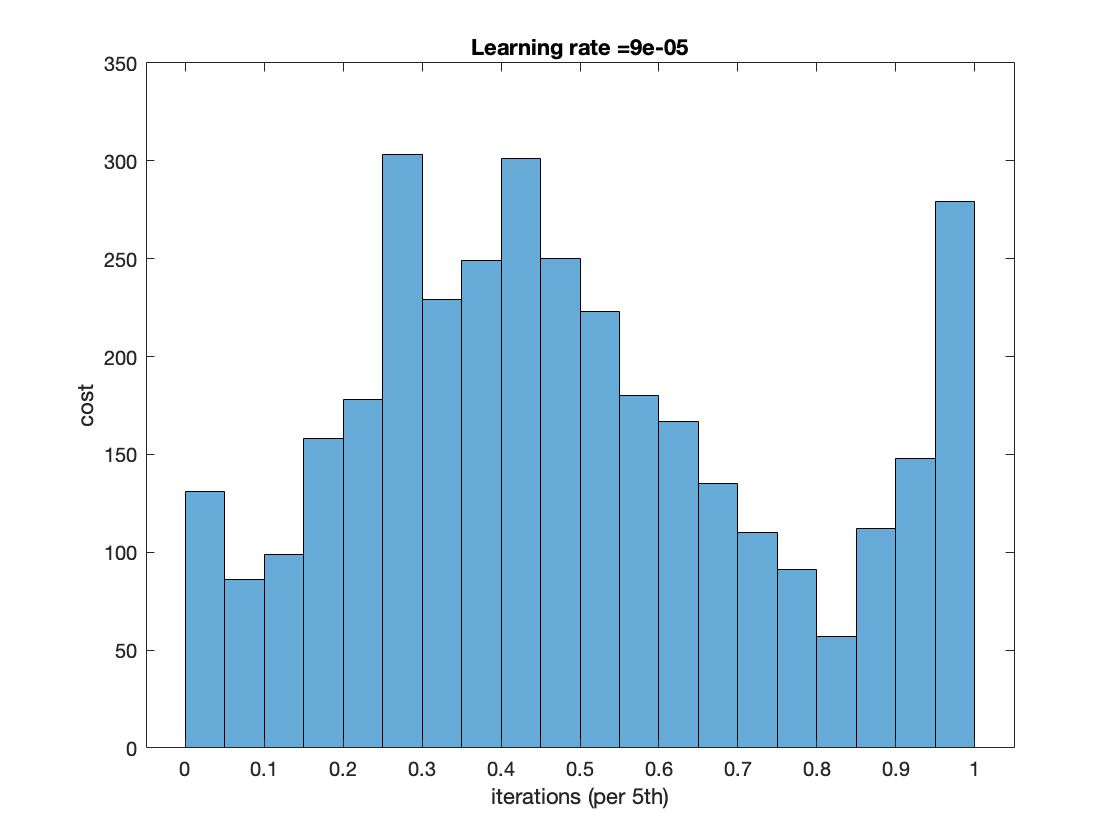

dZ =    -2.0000   -2.0000   -2.0000   -2.0001   -2.0001   -2.0005   -2.0001   -2.0001   -2.0001   -2.0001   -2.0001   -1.9999   -2.0001   -2.0001   -2.0001   -2.0002   -2.0001   -2.0001   -2.0000   -1.9999   -1.9999   -2.0002   -2.0000   -2.0001   -2.0000   -2.0000   -2.0002   -2.0002   -2.0000   -2.0001   -2.0000   -2.0000   -1.9999   -2.0001   -2.0001   -2.0000   -2.0001   -2.0000   -1.9999   -2.0000   -2.0001   -2.0000   -2.0000   -2.0001   -2.0002   -2.0001   -2.0000   -2.0001   -2.0001   -2.0002


dA_prev =     0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.008

dW =    -0.0041   -0.0210   -0.0001         0   -0.0000   -0.0009   -0.0172


db = -2.0000

dZ =     0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080         0         0         0         0         0    0.0080         0         0         0         0         0         0    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    

dA_prev = 	1.0e+-3 *

    0.0524    0.2599    0.1044    0.2599    0.2599    0.2710    0.1036    0.2600    0.2600    0.2599    0.2599    0.1044    0.2600    0.2080    0.2080    0.3229    0.2600    0.2599    0.2080    0.0524    0.1044    0.2600    0.2080    0.2709    0.2599    0.2599    0.1556    0.2600    0.2599    0.1556    0.2599    0.2080    0.0524    0.2599    0.2599    0.2599    0.2080    0.2599    0.1044    0.2599    0.2600    0.2599    0.2080    0.2599    0.3229    0.2600    0.2599    0.2599    0.3229    0.2710
   -0.0031   -0.2613   -0.0174   -0.2613   -0.2613   -0.0811   -0.2296   -0.2613   -0.2613   -0.2613   -0.2613   -0.0174   -0.2613   -0.2470   -0.2470   -0.0954   -0.2613   -0.2613   -0.2470   -0.0031   -0.0174   -0.2613   -0.2470   -0.0811   -0.2613   -0.2613   -0.2439   -0.2613   -0.2613   -0.2439   -0.2613   -0.2470   -0.0031   -0.2613   -0.2613   -0.2613   -0.2470   -0.2613   -0.0174   -0.2613   -0.2613   -0.2613   -0.2470   -0.2613   -0.0954   -0.2613   -0.2613   -0.2

dW =     0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000 

db =     0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0253


dZ =    -2.0001   -2.0002   -2.0001   -2.0003   -2.0003   -2.0007   -2.0002   -2.0003   -2.0003   -2.0002   -2.0002   -2.0001   -2.0003   -2.0003   -2.0002   -2.0004   -2.0003   -2.0003   -2.0002   -2.0001   -2.0001   -2.0003   -2.0002   -2.0003   -2.0002   -2.0002   -2.0004   -2.0004   -2.0001   -2.0002   -2.0002   -2.0002   -2.0001   -2.0003   -2.0003   -2.0002   -2.0003   -2.0002   -2.0001   -2.0002   -2.0003   -2.0002   -2.0002   -2.0003   -2.0003   -2.0003   -2.0001   -2.0003   -2.0002   -2.0004


dA_prev =     0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.008

dW =    -0.0041   -0.0210   -0.0001         0   -0.0000   -0.0009   -0.0172


db = -2.0002

dZ =     0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080         0         0         0         0         0    0.0080         0         0         0         0         0         0    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    

dA_prev = 	1.0e+-3 *

    0.0524    0.2599    0.1043    0.2599    0.2599    0.2710    0.1036    0.2599    0.2599    0.2599    0.2599    0.1043    0.2599    0.2080    0.2080    0.3229    0.2599    0.2599    0.2079    0.0524    0.1043    0.2599    0.2079    0.2709    0.2599    0.2599    0.1556    0.2599    0.2599    0.1556    0.2599    0.2079    0.0524    0.2599    0.2599    0.2599    0.2080    0.2599    0.1043    0.2599    0.2599    0.2599    0.2079    0.2599    0.3229    0.2599    0.2599    0.2599    0.3229    0.2709
   -0.0031   -0.2614   -0.0174   -0.2614   -0.2614   -0.0812   -0.2297   -0.2614   -0.2614   -0.2614   -0.2614   -0.0174   -0.2614   -0.2471   -0.2471   -0.0955   -0.2614   -0.2614   -0.2471   -0.0031   -0.0174   -0.2614   -0.2471   -0.0812   -0.2614   -0.2614   -0.2440   -0.2614   -0.2614   -0.2440   -0.2614   -0.2471   -0.0031   -0.2614   -0.2614   -0.2614   -0.2471   -0.2614   -0.0174   -0.2614   -0.2614   -0.2614   -0.2471   -0.2614   -0.0954   -0.2614   -0.2614   -0.2

dW =     0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000 

db =     0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0253


dZ =    -2.0003   -2.0004   -2.0003   -2.0005   -2.0004   -2.0008   -2.0004   -2.0005   -2.0005   -2.0004   -2.0004   -2.0003   -2.0005   -2.0005   -2.0004   -2.0006   -2.0005   -2.0005   -2.0004   -2.0002   -2.0003   -2.0005   -2.0004   -2.0005   -2.0004   -2.0004   -2.0005   -2.0005   -2.0003   -2.0004   -2.0004   -2.0003   -2.0003   -2.0004   -2.0004   -2.0004   -2.0004   -2.0004   -2.0003   -2.0004   -2.0005   -2.0004   -2.0004   -2.0004   -2.0005   -2.0005   -2.0003   -2.0005   -2.0004   -2.0006


dA_prev =     0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.008

dW =    -0.0041   -0.0210   -0.0001         0   -0.0000   -0.0009   -0.0172


db = -2.0003

dZ =     0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080         0         0         0         0         0    0.0080         0         0         0         0         0         0    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    

dA_prev = 	1.0e+-3 *

    0.0523    0.2599    0.1043    0.2599    0.2599    0.2709    0.1036    0.2599    0.2599    0.2599    0.2599    0.1043    0.2599    0.2079    0.2079    0.3229    0.2599    0.2599    0.2079    0.0523    0.1043    0.2599    0.2079    0.2709    0.2599    0.2599    0.1556    0.2599    0.2599    0.1556    0.2599    0.2079    0.0523    0.2599    0.2599    0.2599    0.2079    0.2599    0.1043    0.2599    0.2599    0.2599    0.2079    0.2599    0.3228    0.2599    0.2599    0.2599    0.3228    0.2709
   -0.0031   -0.2614   -0.0174   -0.2614   -0.2614   -0.0812   -0.2298   -0.2614   -0.2614   -0.2614   -0.2614   -0.0174   -0.2614   -0.2472   -0.2472   -0.0955   -0.2614   -0.2614   -0.2471   -0.0031   -0.0174   -0.2614   -0.2471   -0.0812   -0.2614   -0.2614   -0.2441   -0.2614   -0.2614   -0.2440   -0.2614   -0.2471   -0.0031   -0.2614   -0.2614   -0.2614   -0.2472   -0.2614   -0.0174   -0.2614   -0.2614   -0.2614   -0.2471   -0.2614   -0.0955   -0.2614   -0.2614   -0.2

dW =     0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000 

db =     0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0253


dZ =    -2.0005   -2.0006   -2.0005   -2.0006   -2.0006   -2.0010   -2.0006   -2.0006   -2.0007   -2.0006   -2.0006   -2.0005   -2.0006   -2.0007   -2.0006   -2.0007   -2.0007   -2.0006   -2.0006   -2.0004   -2.0005   -2.0007   -2.0006   -2.0007   -2.0005   -2.0005   -2.0007   -2.0007   -2.0005   -2.0006   -2.0005   -2.0005   -2.0005   -2.0006   -2.0006   -2.0006   -2.0006   -2.0006   -2.0005   -2.0006   -2.0006   -2.0006   -2.0005   -2.0006   -2.0007   -2.0006   -2.0005   -2.0006   -2.0006   -2.0008


dA_prev =     0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.008

dW =    -0.0041   -0.0210   -0.0001         0   -0.0000   -0.0009   -0.0173


db = -2.0005

dZ =     0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080         0         0         0         0         0    0.0080         0         0         0         0         0         0    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    

dA_prev = 	1.0e+-3 *

    0.0523    0.2598    0.1042    0.2598    0.2598    0.2709    0.1036    0.2598    0.2598    0.2598    0.2598    0.1042    0.2598    0.2079    0.2079    0.3228    0.2598    0.2598    0.2079    0.0523    0.1042    0.2598    0.2079    0.2708    0.2598    0.2598    0.1556    0.2598    0.2598    0.1556    0.2598    0.2079    0.0523    0.2598    0.2598    0.2598    0.2079    0.2598    0.1042    0.2598    0.2598    0.2598    0.2079    0.2598    0.3228    0.2598    0.2598    0.2598    0.3228    0.2709
   -0.0031   -0.2615   -0.0174   -0.2615   -0.2615   -0.0813   -0.2298   -0.2615   -0.2615   -0.2615   -0.2615   -0.0174   -0.2615   -0.2472   -0.2472   -0.0955   -0.2615   -0.2615   -0.2472   -0.0031   -0.0174   -0.2615   -0.2472   -0.0813   -0.2615   -0.2615   -0.2441   -0.2615   -0.2615   -0.2441   -0.2615   -0.2472   -0.0031   -0.2615   -0.2615   -0.2615   -0.2472   -0.2615   -0.0174   -0.2615   -0.2615   -0.2615   -0.2472   -0.2615   -0.0955   -0.2615   -0.2615   -0.2

dW =     0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000 

db =     0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0253


dZ =    -2.0007   -2.0008   -2.0007   -2.0008   -2.0008   -2.0012   -2.0008   -2.0008   -2.0008   -2.0008   -2.0008   -2.0007   -2.0008   -2.0008   -2.0008   -2.0009   -2.0009   -2.0008   -2.0008   -2.0006   -2.0006   -2.0009   -2.0008   -2.0008   -2.0007   -2.0007   -2.0009   -2.0009   -2.0007   -2.0008   -2.0007   -2.0007   -2.0007   -2.0008   -2.0008   -2.0007   -2.0008   -2.0007   -2.0006   -2.0008   -2.0008   -2.0008   -2.0007   -2.0008   -2.0009   -2.0008   -2.0007   -2.0008   -2.0008   -2.0010


dA_prev =     0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.008

dW =    -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0173


db = -2.0006

dZ =     0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080         0         0         0         0         0    0.0080         0         0         0         0         0         0    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    

dA_prev = 	1.0e+-3 *

    0.0523    0.2598    0.1042    0.2598    0.2598    0.2709    0.1036    0.2598    0.2598    0.2598    0.2598    0.1042    0.2598    0.2078    0.2078    0.3228    0.2598    0.2598    0.2078    0.0522    0.1042    0.2598    0.2078    0.2708    0.2598    0.2598    0.1556    0.2598    0.2598    0.1556    0.2598    0.2078    0.0522    0.2598    0.2598    0.2598    0.2078    0.2598    0.1042    0.2598    0.2598    0.2598    0.2078    0.2598    0.3228    0.2598    0.2598    0.2598    0.3228    0.2708
   -0.0031   -0.2616   -0.0174   -0.2616   -0.2616   -0.0813   -0.2299   -0.2616   -0.2616   -0.2616   -0.2616   -0.0174   -0.2616   -0.2473   -0.2473   -0.0956   -0.2616   -0.2616   -0.2473   -0.0031   -0.0174   -0.2616   -0.2473   -0.0813   -0.2616   -0.2616   -0.2442   -0.2616   -0.2615   -0.2442   -0.2615   -0.2473   -0.0031   -0.2616   -0.2616   -0.2616   -0.2473   -0.2616   -0.0174   -0.2616   -0.2616   -0.2616   -0.2473   -0.2616   -0.0956   -0.2616   -0.2615   -0.2

dW =     0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000 

db =     0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0253


dZ =    -2.0009   -2.0009   -2.0009   -2.0010   -2.0010   -2.0014   -2.0010   -2.0010   -2.0010   -2.0010   -2.0010   -2.0008   -2.0010   -2.0010   -2.0010   -2.0011   -2.0010   -2.0010   -2.0009   -2.0008   -2.0008   -2.0011   -2.0009   -2.0010   -2.0009   -2.0009   -2.0011   -2.0011   -2.0009   -2.0010   -2.0009   -2.0009   -2.0008   -2.0010   -2.0010   -2.0009   -2.0010   -2.0009   -2.0008   -2.0009   -2.0010   -2.0009   -2.0009   -2.0010   -2.0011   -2.0010   -2.0009   -2.0010   -2.0010   -2.0011


dA_prev =     0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.008

dW =    -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0173


db = -2.0007

dZ =     0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080         0         0         0         0         0    0.0080         0         0         0         0         0         0    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    

dA_prev = 	1.0e+-3 *

    0.0522    0.2598    0.1042    0.2598    0.2598    0.2708    0.1036    0.2598    0.2598    0.2598    0.2598    0.1042    0.2598    0.2078    0.2078    0.3228    0.2598    0.2598    0.2078    0.0522    0.1042    0.2598    0.2078    0.2708    0.2598    0.2597    0.1556    0.2598    0.2597    0.1556    0.2597    0.2078    0.0522    0.2598    0.2598    0.2598    0.2078    0.2598    0.1042    0.2598    0.2598    0.2598    0.2078    0.2598    0.3227    0.2598    0.2597    0.2598    0.3227    0.2708
   -0.0031   -0.2616   -0.0174   -0.2616   -0.2616   -0.0814   -0.2300   -0.2616   -0.2616   -0.2616   -0.2616   -0.0174   -0.2616   -0.2474   -0.2473   -0.0956   -0.2616   -0.2616   -0.2473   -0.0031   -0.0174   -0.2616   -0.2473   -0.0814   -0.2616   -0.2616   -0.2443   -0.2616   -0.2616   -0.2442   -0.2616   -0.2473   -0.0031   -0.2616   -0.2616   -0.2616   -0.2473   -0.2616   -0.0174   -0.2616   -0.2616   -0.2616   -0.2473   -0.2616   -0.0956   -0.2616   -0.2616   -0.2

dW =     0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000 

db =     0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ =    -2.0010   -2.0011   -2.0010   -2.0012   -2.0012   -2.0016   -2.0011   -2.0012   -2.0012   -2.0011   -2.0011   -2.0010   -2.0012   -2.0012   -2.0011   -2.0013   -2.0012   -2.0012   -2.0011   -2.0010   -2.0010   -2.0012   -2.0011   -2.0012   -2.0011   -2.0011   -2.0013   -2.0013   -2.0010   -2.0012   -2.0011   -2.0011   -2.0010   -2.0012   -2.0012   -2.0011   -2.0012   -2.0011   -2.0010   -2.0011   -2.0012   -2.0011   -2.0011   -2.0012   -2.0013   -2.0012   -2.0010   -2.0012   -2.0011   -2.0013


dA_prev =     0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.008

dW =    -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0173


db = -2.0009

dZ =     0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080         0         0         0         0         0    0.0080         0         0         0         0         0         0    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    

dA_prev = 	1.0e+-3 *

    0.0522    0.2597    0.1041    0.2597    0.2597    0.2708    0.1036    0.2597    0.2597    0.2597    0.2597    0.1041    0.2597    0.2078    0.2078    0.3227    0.2597    0.2597    0.2078    0.0522    0.1041    0.2597    0.2078    0.2707    0.2597    0.2597    0.1556    0.2597    0.2597    0.1556    0.2597    0.2077    0.0522    0.2597    0.2597    0.2597    0.2078    0.2597    0.1041    0.2597    0.2597    0.2597    0.2078    0.2597    0.3227    0.2597    0.2597    0.2597    0.3227    0.2708
   -0.0031   -0.2617   -0.0174   -0.2617   -0.2617   -0.0814   -0.2300   -0.2617   -0.2617   -0.2617   -0.2617   -0.0174   -0.2617   -0.2474   -0.2474   -0.0957   -0.2617   -0.2617   -0.2474   -0.0031   -0.0174   -0.2617   -0.2474   -0.0814   -0.2617   -0.2617   -0.2443   -0.2617   -0.2617   -0.2443   -0.2617   -0.2474   -0.0031   -0.2617   -0.2617   -0.2617   -0.2474   -0.2617   -0.0174   -0.2617   -0.2617   -0.2617   -0.2474   -0.2617   -0.0957   -0.2617   -0.2617   -0.2

dW =     0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000 

db = 7×1
    0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0012   -2.0013   -2.0012   -2.0014   -2.0013   -2.0017   -2.0013   -2.0014   -2.0014   -2.0013   -2.0013   -2.0012   -2.0014   -2.0014   -2.0013   -2.0015   -2.0014   -2.0014   -2.0013   -2.0011   -2.0012   -2.0014   -2.0013   -2.0014   -2.0013   -2.0013   -2.0014   -2.0015   -2.0012   -2.0013


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333 

dW = 1×7
   -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0174


db = -2.0010

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0521    0.2597    0.1041    0.2597    0.2597    0.2708    0.1036    0.2597    0.2597    0.2597    0.2597    0.1041    0.2597    0.2077    0.2077    0.3227    0.2597    0.2597    0.2077    0.0521    0.1041    0.2597    0.2077    0.2707    0.2597    0.2597    0.1556    0.2597    0.2597    0.1556
   -0.0031   -0.2617   -0.0174   -0.2618   -0.2618   -0.0815   -0.2301   -0.2618   -0.2618   -0.2617   -0.2617   -0.0174   -0.2618   -0.2475   -0.2475   -0.0957   -0.2618   -0.2618   -0.2475   -0.0031   -0.0174   -0.2618   -0.2475   -0.0814   -0.2617   -0.2617   -0.2444   -0.2618   -0.2617   -0.2444
   -0.0048    0.0910    0.0147    0.0910    0.0910   -0.1517    0.0569    0.0910    0.0910    0.0910    0.0910    0.0147    0.0910    0.0715    0.0715   -0.1323    0.0910    0.0910    0.0715   -0.0048    0.0147    0.0910    0.0715   -0.1517    0.0910    0.0910    0.0763    0.0910    0.0910    0.0763
    0.2053   -0.2342    0.1570   -0.2342   -0.2342   -0.1400   -0.3429   -0.2342

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0014   -2.0015   -2.0014   -2.0015   -2.0015   -2.0019   -2.0015   -2.0015   -2.0016   -2.0015   -2.0015   -2.0014   -2.0015   -2.0016   -2.0015   -2.0017   -2.0016   -2.0015   -2.0015   -2.0013   -2.0014   -2.0016   -2.0015   -2.0016   -2.0015   -2.0014   -2.0016   -2.0016   -2.0014   -2.0015


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333 

dW = 1×7
   -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0174


db = -2.0012

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0521    0.2596    0.1041    0.2596    0.2596    0.2707    0.1036    0.2596    0.2597    0.2596    0.2596    0.1041    0.2597    0.2077    0.2077    0.3227    0.2597    0.2596    0.2077    0.0521    0.1041    0.2597    0.2077    0.2707    0.2596    0.2596    0.1556    0.2597    0.2596    0.1556
   -0.0031   -0.2618   -0.0174   -0.2618   -0.2618   -0.0815   -0.2302   -0.2618   -0.2618   -0.2618   -0.2618   -0.0174   -0.2618   -0.2475   -0.2475   -0.0958   -0.2618   -0.2618   -0.2475   -0.0031   -0.0174   -0.2618   -0.2475   -0.0815   -0.2618   -0.2618   -0.2445   -0.2618   -0.2618   -0.2445
   -0.0048    0.0909    0.0146    0.0909    0.0909   -0.1518    0.0568    0.0909    0.0909    0.0909    0.0909    0.0146    0.0909    0.0715    0.0715   -0.1323    0.0909    0.0909    0.0715   -0.0048    0.0146    0.0909    0.0715   -0.1518    0.0909    0.0909    0.0763    0.0909    0.0909    0.0763
    0.2052   -0.2344    0.1569   -0.2344   -0.2344   -0.1402   -0.3430   -0.2344

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0016   -2.0017   -2.0016   -2.0017   -2.0017   -2.0021   -2.0017   -2.0017   -2.0017   -2.0017   -2.0017   -2.0016   -2.0017   -2.0017   -2.0017   -2.0018   -2.0018   -2.0017   -2.0017   -2.0015   -2.0015   -2.0018   -2.0017   -2.0017   -2.0016   -2.0016   -2.0018   -2.0018   -2.0016   -2.0017


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333 

dW = 1×7
   -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0174


db = -2.0013

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0521    0.2596    0.1040    0.2596    0.2596    0.2707    0.1036    0.2596    0.2596    0.2596    0.2596    0.1040    0.2596    0.2076    0.2076    0.3226    0.2596    0.2596    0.2076    0.0521    0.1040    0.2596    0.2076    0.2706    0.2596    0.2596    0.1556    0.2596    0.2596    0.1556
   -0.0031   -0.2619   -0.0174   -0.2619   -0.2619   -0.0816   -0.2302   -0.2619   -0.2619   -0.2619   -0.2619   -0.0174   -0.2619   -0.2476   -0.2476   -0.0958   -0.2619   -0.2619   -0.2476   -0.0031   -0.0174   -0.2619   -0.2476   -0.0815   -0.2619   -0.2619   -0.2445   -0.2619   -0.2619   -0.2445
   -0.0048    0.0909    0.0146    0.0909    0.0909   -0.1519    0.0568    0.0909    0.0909    0.0909    0.0909    0.0146    0.0909    0.0714    0.0714   -0.1324    0.0909    0.0909    0.0714   -0.0048    0.0146    0.0909    0.0714   -0.1519    0.0909    0.0909    0.0762    0.0909    0.0908    0.0762
    0.2052   -0.2346    0.1569   -0.2346   -0.2346   -0.1404   -0.3431   -0.2346

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0018   -2.0018   -2.0018   -2.0019   -2.0019   -2.0023   -2.0019   -2.0019   -2.0019   -2.0019   -2.0019   -2.0017   -2.0019   -2.0019   -2.0019   -2.0020   -2.0019   -2.0019   -2.0018   -2.0017   -2.0017   -2.0020   -2.0018   -2.0019   -2.0018   -2.0018   -2.0020   -2.0020   -2.0018   -2.0019


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333 

dW = 1×7
   -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0175


db = -2.0014

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0520    0.2596    0.1040    0.2596    0.2596    0.2707    0.1036    0.2596    0.2596    0.2596    0.2596    0.1040    0.2596    0.2076    0.2076    0.3226    0.2596    0.2596    0.2076    0.0520    0.1040    0.2596    0.2076    0.2706    0.2596    0.2596    0.1556    0.2596    0.2596    0.1556
   -0.0031   -0.2619   -0.0174   -0.2619   -0.2619   -0.0816   -0.2303   -0.2619   -0.2620   -0.2619   -0.2619   -0.0174   -0.2619   -0.2477   -0.2477   -0.0959   -0.2620   -0.2619   -0.2477   -0.0031   -0.0174   -0.2620   -0.2477   -0.0816   -0.2619   -0.2619   -0.2446   -0.2620   -0.2619   -0.2446
   -0.0048    0.0908    0.0146    0.0908    0.0908   -0.1520    0.0567    0.0908    0.0908    0.0908    0.0908    0.0146    0.0908    0.0713    0.0713   -0.1325    0.0908    0.0908    0.0713   -0.0048    0.0146    0.0908    0.0713   -0.1519    0.0908    0.0908    0.0762    0.0908    0.0908    0.0762
    0.2051   -0.2347    0.1568   -0.2347   -0.2347   -0.1405   -0.3432   -0.2347

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0019   -2.0020   -2.0019   -2.0021   -2.0021   -2.0025   -2.0020   -2.0021   -2.0021   -2.0020   -2.0020   -2.0019   -2.0021   -2.0021   -2.0021   -2.0022   -2.0021   -2.0021   -2.0020   -2.0019   -2.0019   -2.0021   -2.0020   -2.0021   -2.0020   -2.0020   -2.0022   -2.0022   -2.0019   -2.0021


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333 

dW = 1×7
   -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0175


db = -2.0016

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0520    0.2595    0.1039    0.2595    0.2595    0.2706    0.1036    0.2595    0.2595    0.2595    0.2595    0.1039    0.2595    0.2076    0.2076    0.3226    0.2595    0.2595    0.2076    0.0520    0.1039    0.2595    0.2076    0.2706    0.2595    0.2595    0.1556    0.2595    0.2595    0.1556
   -0.0031   -0.2620   -0.0173   -0.2620   -0.2620   -0.0817   -0.2304   -0.2620   -0.2620   -0.2620   -0.2620   -0.0173   -0.2620   -0.2477   -0.2477   -0.0959   -0.2620   -0.2620   -0.2477   -0.0031   -0.0173   -0.2620   -0.2477   -0.0816   -0.2620   -0.2620   -0.2447   -0.2620   -0.2620   -0.2447
   -0.0048    0.0907    0.0146    0.0907    0.0907   -0.1521    0.0567    0.0907    0.0907    0.0907    0.0907    0.0146    0.0907    0.0713    0.0713   -0.1326    0.0907    0.0907    0.0713   -0.0048    0.0146    0.0907    0.0713   -0.1520    0.0907    0.0907    0.0761    0.0907    0.0907    0.0761
    0.2051   -0.2349    0.1568   -0.2349   -0.2349   -0.1407   -0.3434   -0.2349

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0021   -2.0022   -2.0021   -2.0023   -2.0022   -2.0026   -2.0022   -2.0023   -2.0023   -2.0022   -2.0022   -2.0021   -2.0023   -2.0023   -2.0022   -2.0024   -2.0023   -2.0023   -2.0022   -2.0020   -2.0021   -2.0023   -2.0022   -2.0023   -2.0022   -2.0022   -2.0023   -2.0024   -2.0021   -2.0022


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333 

dW = 1×7
   -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0175


db = -2.0017

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0519    0.2595    0.1039    0.2595    0.2595    0.2706    0.1036    0.2595    0.2595    0.2595    0.2595    0.1039    0.2595    0.2075    0.2075    0.3225    0.2595    0.2595    0.2075    0.0519    0.1039    0.2595    0.2075    0.2706    0.2595    0.2595    0.1556    0.2595    0.2595    0.1556
   -0.0031   -0.2621   -0.0173   -0.2621   -0.2621   -0.0817   -0.2304   -0.2621   -0.2621   -0.2621   -0.2621   -0.0173   -0.2621   -0.2478   -0.2478   -0.0960   -0.2621   -0.2621   -0.2478   -0.0031   -0.0173   -0.2621   -0.2478   -0.0817   -0.2621   -0.2621   -0.2447   -0.2621   -0.2621   -0.2447
   -0.0049    0.0907    0.0146    0.0907    0.0907   -0.1521    0.0566    0.0907    0.0907    0.0907    0.0907    0.0146    0.0907    0.0712    0.0712   -0.1327    0.0907    0.0907    0.0712   -0.0049    0.0146    0.0907    0.0712   -0.1521    0.0907    0.0907    0.0761    0.0907    0.0907    0.0761
    0.2050   -0.2351    0.1567   -0.2351   -0.2351   -0.1409   -0.3435   -0.2351

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0043    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0070
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0023   -2.0024   -2.0023   -2.0024   -2.0024   -2.0028   -2.0024   -2.0024   -2.0025   -2.0024   -2.0024   -2.0023   -2.0024   -2.0025   -2.0024   -2.0026   -2.0025   -2.0024   -2.0024   -2.0022   -2.0023   -2.0025   -2.0024   -2.0025   -2.0024   -2.0024   -2.0025   -2.0025   -2.0023   -2.0024


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333 

dW = 1×7
   -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0176


db = -2.0019

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0519    0.2595    0.1039    0.2595    0.2595    0.2706    0.1036    0.2595    0.2595    0.2595    0.2595    0.1039    0.2595    0.2075    0.2075    0.3225    0.2595    0.2595    0.2075    0.0519    0.1039    0.2595    0.2075    0.2705    0.2595    0.2595    0.1556    0.2595    0.2594    0.1556
   -0.0031   -0.2621   -0.0173   -0.2621   -0.2621   -0.0817   -0.2305   -0.2621   -0.2621   -0.2621   -0.2621   -0.0173   -0.2621   -0.2479   -0.2479   -0.0960   -0.2621   -0.2621   -0.2479   -0.0031   -0.0173   -0.2621   -0.2479   -0.0817   -0.2621   -0.2621   -0.2448   -0.2622   -0.2621   -0.2448
   -0.0049    0.0906    0.0146    0.0906    0.0906   -0.1522    0.0566    0.0906    0.0906    0.0906    0.0906    0.0146    0.0906    0.0712    0.0712   -0.1327    0.0906    0.0906    0.0712   -0.0049    0.0146    0.0906    0.0712   -0.1522    0.0906    0.0906    0.0760    0.0906    0.0906    0.0760
    0.2050   -0.2352    0.1567   -0.2352   -0.2352   -0.1410   -0.3436   -0.2352

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0025   -2.0026   -2.0025   -2.0026   -2.0026   -2.0030   -2.0026   -2.0026   -2.0027   -2.0026   -2.0026   -2.0025   -2.0026   -2.0026   -2.0026   -2.0027   -2.0027   -2.0026   -2.0026   -2.0024   -2.0025   -2.0027   -2.0026   -2.0027   -2.0025   -2.0025   -2.0027   -2.0027   -2.0025   -2.0026


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333 

dW = 1×7
   -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0176


db = -2.0020

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0519    0.2594    0.1038    0.2594    0.2594    0.2705    0.1036    0.2594    0.2594    0.2594    0.2594    0.1038    0.2594    0.2075    0.2075    0.3225    0.2594    0.2594    0.2075    0.0519    0.1038    0.2594    0.2074    0.2705    0.2594    0.2594    0.1556    0.2594    0.2594    0.1556
   -0.0031   -0.2622   -0.0173   -0.2622   -0.2622   -0.0818   -0.2306   -0.2622   -0.2622   -0.2622   -0.2622   -0.0173   -0.2622   -0.2479   -0.2479   -0.0961   -0.2622   -0.2622   -0.2479   -0.0031   -0.0173   -0.2622   -0.2479   -0.0818   -0.2622   -0.2622   -0.2449   -0.2622   -0.2622   -0.2449
   -0.0049    0.0906    0.0146    0.0906    0.0906   -0.1523    0.0565    0.0906    0.0906    0.0906    0.0906    0.0146    0.0906    0.0711    0.0711   -0.1328    0.0906    0.0906    0.0711   -0.0049    0.0146    0.0906    0.0711   -0.1523    0.0906    0.0906    0.0760    0.0906    0.0906    0.0760
    0.2049   -0.2354    0.1566   -0.2354   -0.2354   -0.1412   -0.3437   -0.2354

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0081
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0027   -2.0028   -2.0027   -2.0028   -2.0028   -2.0032   -2.0028   -2.0028   -2.0028   -2.0028   -2.0028   -2.0026   -2.0028   -2.0028   -2.0028   -2.0029   -2.0028   -2.0028   -2.0027   -2.0026   -2.0026   -2.0029   -2.0027   -2.0028   -2.0027   -2.0027   -2.0029   -2.0029   -2.0027   -2.0028


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333 

dW = 1×7
   -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0176


db = -2.0021

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0518    0.2594    0.1038    0.2594    0.2594    0.2705    0.1036    0.2594    0.2594    0.2594    0.2594    0.1038    0.2594    0.2074    0.2074    0.3224    0.2594    0.2594    0.2074    0.0518    0.1038    0.2594    0.2074    0.2705    0.2594    0.2594    0.1556    0.2594    0.2594    0.1556
   -0.0031   -0.2623   -0.0173   -0.2623   -0.2623   -0.0818   -0.2307   -0.2623   -0.2623   -0.2623   -0.2623   -0.0173   -0.2623   -0.2480   -0.2480   -0.0961   -0.2623   -0.2623   -0.2480   -0.0031   -0.0173   -0.2623   -0.2480   -0.0818   -0.2623   -0.2623   -0.2449   -0.2623   -0.2622   -0.2449
   -0.0049    0.0905    0.0146    0.0905    0.0905   -0.1524    0.0565    0.0905    0.0905    0.0905    0.0905    0.0146    0.0905    0.0710    0.0710   -0.1329    0.0905    0.0905    0.0710   -0.0049    0.0146    0.0905    0.0710   -0.1524    0.0905    0.0905    0.0759    0.0905    0.0905    0.0759
    0.2048   -0.2356    0.1565   -0.2356   -0.2356   -0.1413   -0.3438   -0.2356

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0029   -2.0029   -2.0028   -2.0030   -2.0030   -2.0034   -2.0029   -2.0030   -2.0030   -2.0029   -2.0029   -2.0028   -2.0030   -2.0030   -2.0030   -2.0031   -2.0030   -2.0030   -2.0029   -2.0028   -2.0028   -2.0030   -2.0029   -2.0030   -2.0029   -2.0029   -2.0031   -2.0031   -2.0028   -2.0030


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333    0.0333 

dW = 1×7
   -0.0041   -0.0209   -0.0001         0   -0.0000   -0.0009   -0.0176


db = -2.0023

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0518    0.2593    0.1037    0.2594    0.2593    0.2705    0.1036    0.2594    0.2594    0.2593    0.2593    0.1037    0.2594    0.2074    0.2074    0.3224    0.2594    0.2594    0.2074    0.0518    0.1037    0.2594    0.2074    0.2704    0.2593    0.2593    0.1556    0.2594    0.2593    0.1556
   -0.0031   -0.2623   -0.0173   -0.2623   -0.2623   -0.0819   -0.2307   -0.2623   -0.2623   -0.2623   -0.2623   -0.0173   -0.2623   -0.2481   -0.2481   -0.0962   -0.2623   -0.2623   -0.2481   -0.0031   -0.0173   -0.2623   -0.2481   -0.0819   -0.2623   -0.2623   -0.2450   -0.2623   -0.2623   -0.2450
   -0.0049    0.0905    0.0146    0.0905    0.0905   -0.1525    0.0564    0.0905    0.0905    0.0905    0.0905    0.0146    0.0905    0.0710    0.0710   -0.1330    0.0905    0.0905    0.0710   -0.0049    0.0146    0.0905    0.0710   -0.1524    0.0905    0.0905    0.0759    0.0905    0.0905    0.0759
    0.2048   -0.2357    0.1565   -0.2357   -0.2357   -0.1415   -0.3439   -0.2357

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0030   -2.0031   -2.0030   -2.0032   -2.0032   -2.0036   -2.0031   -2.0032   -2.0032   -2.0031   -2.0031   -2.0030   -2.0032   -2.0032   -2.0031   -2.0033   -2.0032   -2.0032   -2.0031   -2.0029   -2.0030   -2.0032   -2.0031   -2.0032   -2.0031   -2.0031   -2.0032   -2.0033   -2.0030   -2.0031


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0333    0.0333    0.0334    0.0333    0.0333 

dW = 1×7
   -0.0041   -0.0208   -0.0001         0   -0.0000   -0.0009   -0.0177


db = -2.0024

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0517    0.2593    0.1037    0.2593    0.2593    0.2704    0.1036    0.2593    0.2593    0.2593    0.2593    0.1037    0.2593    0.2073    0.2073    0.3224    0.2593    0.2593    0.2073    0.0517    0.1037    0.2593    0.2073    0.2704    0.2593    0.2593    0.1556    0.2593    0.2593    0.1556
   -0.0031   -0.2624   -0.0173   -0.2624   -0.2624   -0.0819   -0.2308   -0.2624   -0.2624   -0.2624   -0.2624   -0.0173   -0.2624   -0.2481   -0.2481   -0.0962   -0.2624   -0.2624   -0.2481   -0.0031   -0.0173   -0.2624   -0.2481   -0.0819   -0.2624   -0.2624   -0.2451   -0.2624   -0.2624   -0.2451
   -0.0049    0.0904    0.0145    0.0904    0.0904   -0.1526    0.0564    0.0904    0.0904    0.0904    0.0904    0.0145    0.0904    0.0709    0.0709   -0.1331    0.0904    0.0904    0.0709   -0.0049    0.0145    0.0904    0.0709   -0.1525    0.0904    0.0904    0.0759    0.0904    0.0904    0.0758
    0.2047   -0.2359    0.1564   -0.2359   -0.2359   -0.1417   -0.3440   -0.2359

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0078    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0032   -2.0033   -2.0032   -2.0033   -2.0033   -2.0037   -2.0033   -2.0034   -2.0034   -2.0033   -2.0033   -2.0032   -2.0034   -2.0034   -2.0033   -2.0035   -2.0034   -2.0033   -2.0033   -2.0031   -2.0032   -2.0034   -2.0033   -2.0034   -2.0033   -2.0033   -2.0034   -2.0034   -2.0032   -2.0033


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0333    0.0333    0.0334    0.0333    0.0333 

dW = 1×7
   -0.0041   -0.0208   -0.0001         0   -0.0000   -0.0009   -0.0177


db = -2.0025

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0517    0.2593    0.1037    0.2593    0.2593    0.2704    0.1036    0.2593    0.2593    0.2593    0.2593    0.1037    0.2593    0.2073    0.2073    0.3223    0.2593    0.2593    0.2073    0.0517    0.1037    0.2593    0.2073    0.2704    0.2593    0.2593    0.1556    0.2593    0.2593    0.1556
   -0.0031   -0.2625   -0.0173   -0.2625   -0.2625   -0.0820   -0.2309   -0.2625   -0.2625   -0.2625   -0.2625   -0.0173   -0.2625   -0.2482   -0.2482   -0.0963   -0.2625   -0.2625   -0.2482   -0.0031   -0.0173   -0.2625   -0.2482   -0.0820   -0.2625   -0.2624   -0.2451   -0.2625   -0.2624   -0.2451
   -0.0049    0.0903    0.0145    0.0903    0.0903   -0.1526    0.0563    0.0903    0.0903    0.0903    0.0903    0.0145    0.0903    0.0709    0.0709   -0.1331    0.0903    0.0903    0.0709   -0.0049    0.0145    0.0903    0.0709   -0.1526    0.0903    0.0903    0.0758    0.0903    0.0903    0.0758
    0.2047   -0.2361    0.1564   -0.2361   -0.2361   -0.1418   -0.3441   -0.2361

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0034   -2.0035   -2.0034   -2.0035   -2.0035   -2.0039   -2.0035   -2.0035   -2.0036   -2.0035   -2.0035   -2.0034   -2.0035   -2.0036   -2.0035   -2.0036   -2.0036   -2.0035   -2.0035   -2.0033   -2.0034   -2.0036   -2.0035   -2.0036   -2.0034   -2.0034   -2.0036   -2.0036   -2.0034   -2.0035


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0333    0.0333    0.0333    0.0334    0.0334    0.0334    0.0333    0.0334 

dW = 1×7
   -0.0041   -0.0208   -0.0001         0   -0.0000   -0.0009   -0.0177


db = -2.0027

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0517    0.2592    0.1036    0.2592    0.2592    0.2704    0.1036    0.2592    0.2592    0.2592    0.2592    0.1036    0.2592    0.2073    0.2073    0.3223    0.2592    0.2592    0.2073    0.0517    0.1036    0.2592    0.2073    0.2703    0.2592    0.2592    0.1556    0.2593    0.2592    0.1556
   -0.0030   -0.2625   -0.0173   -0.2625   -0.2625   -0.0820   -0.2309   -0.2625   -0.2625   -0.2625   -0.2625   -0.0173   -0.2625   -0.2483   -0.2483   -0.0963   -0.2625   -0.2625   -0.2482   -0.0030   -0.0173   -0.2625   -0.2482   -0.0820   -0.2625   -0.2625   -0.2452   -0.2625   -0.2625   -0.2452
   -0.0049    0.0903    0.0145    0.0903    0.0903   -0.1527    0.0563    0.0903    0.0903    0.0903    0.0903    0.0145    0.0903    0.0708    0.0708   -0.1332    0.0903    0.0903    0.0708   -0.0049    0.0145    0.0903    0.0708   -0.1527    0.0903    0.0903    0.0758    0.0903    0.0903    0.0758
    0.2046   -0.2362    0.1563   -0.2362   -0.2362   -0.1420   -0.3443   -0.2362

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0022    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0036   -2.0037   -2.0036   -2.0037   -2.0037   -2.0041   -2.0037   -2.0037   -2.0037   -2.0037   -2.0037   -2.0035   -2.0037   -2.0037   -2.0037   -2.0038   -2.0037   -2.0037   -2.0037   -2.0035   -2.0035   -2.0038   -2.0036   -2.0037   -2.0036   -2.0036   -2.0038   -2.0038   -2.0036   -2.0037


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0208   -0.0001         0   -0.0000   -0.0009   -0.0178


db = -2.0028

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0516    0.2592    0.1036    0.2592    0.2592    0.2703    0.1036    0.2592    0.2592    0.2592    0.2592    0.1036    0.2592    0.2072    0.2072    0.3223    0.2592    0.2592    0.2072    0.0516    0.1036    0.2592    0.2072    0.2703    0.2592    0.2592    0.1556    0.2592    0.2592    0.1556
   -0.0030   -0.2626   -0.0173   -0.2626   -0.2626   -0.0821   -0.2310   -0.2626   -0.2626   -0.2626   -0.2626   -0.0173   -0.2626   -0.2483   -0.2483   -0.0963   -0.2626   -0.2626   -0.2483   -0.0030   -0.0173   -0.2626   -0.2483   -0.0821   -0.2626   -0.2626   -0.2453   -0.2626   -0.2626   -0.2453
   -0.0050    0.0902    0.0145    0.0902    0.0902   -0.1528    0.0562    0.0902    0.0902    0.0902    0.0902    0.0145    0.0902    0.0708    0.0708   -0.1333    0.0902    0.0902    0.0708   -0.0050    0.0145    0.0902    0.0708   -0.1528    0.0902    0.0902    0.0757    0.0902    0.0902    0.0757
    0.2046   -0.2364    0.1563   -0.2364   -0.2364   -0.1422   -0.3444   -0.2364

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0038   -2.0038   -2.0037   -2.0039   -2.0039   -2.0043   -2.0038   -2.0039   -2.0039   -2.0039   -2.0038   -2.0037   -2.0039   -2.0039   -2.0039   -2.0040   -2.0039   -2.0039   -2.0038   -2.0037   -2.0037   -2.0039   -2.0038   -2.0039   -2.0038   -2.0038   -2.0040   -2.0040   -2.0038   -2.0039


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0208   -0.0001         0   -0.0000   -0.0009   -0.0178


db = -2.0030

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0516    0.2592    0.1036    0.2592    0.2592    0.2703    0.1036    0.2592    0.2592    0.2592    0.2592    0.1036    0.2592    0.2072    0.2072    0.3223    0.2592    0.2592    0.2072    0.0516    0.1036    0.2592    0.2072    0.2703    0.2592    0.2592    0.1556    0.2592    0.2591    0.1556
   -0.0030   -0.2626   -0.0173   -0.2627   -0.2627   -0.0821   -0.2311   -0.2627   -0.2627   -0.2627   -0.2627   -0.0173   -0.2627   -0.2484   -0.2484   -0.0964   -0.2627   -0.2627   -0.2484   -0.0030   -0.0173   -0.2627   -0.2484   -0.0821   -0.2626   -0.2626   -0.2454   -0.2627   -0.2626   -0.2453
   -0.0050    0.0902    0.0145    0.0902    0.0902   -0.1529    0.0562    0.0902    0.0902    0.0902    0.0902    0.0145    0.0902    0.0707    0.0707   -0.1334    0.0902    0.0902    0.0707   -0.0050    0.0145    0.0902    0.0707   -0.1529    0.0902    0.0902    0.0757    0.0902    0.0902    0.0757
    0.2045   -0.2366    0.1562   -0.2366   -0.2366   -0.1423   -0.3445   -0.2366

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0039   -2.0040   -2.0039   -2.0041   -2.0041   -2.0045   -2.0040   -2.0041   -2.0041   -2.0040   -2.0040   -2.0039   -2.0041   -2.0041   -2.0040   -2.0042   -2.0041   -2.0041   -2.0040   -2.0039   -2.0039   -2.0041   -2.0040   -2.0041   -2.0040   -2.0040   -2.0041   -2.0042   -2.0039   -2.0040


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0208   -0.0001         0   -0.0000   -0.0009   -0.0178


db = -2.0031

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0515    0.2591    0.1035    0.2591    0.2591    0.2703    0.1036    0.2591    0.2591    0.2591    0.2591    0.1035    0.2591    0.2072    0.2071    0.3222    0.2591    0.2591    0.2071    0.0515    0.1035    0.2591    0.2071    0.2702    0.2591    0.2591    0.1556    0.2591    0.2591    0.1556
   -0.0030   -0.2627   -0.0173   -0.2627   -0.2627   -0.0822   -0.2311   -0.2627   -0.2627   -0.2627   -0.2627   -0.0173   -0.2627   -0.2485   -0.2484   -0.0964   -0.2627   -0.2627   -0.2484   -0.0030   -0.0173   -0.2627   -0.2484   -0.0822   -0.2627   -0.2627   -0.2454   -0.2627   -0.2627   -0.2454
   -0.0050    0.0901    0.0145    0.0901    0.0901   -0.1530    0.0561    0.0901    0.0901    0.0901    0.0901    0.0145    0.0901    0.0706    0.0706   -0.1335    0.0901    0.0901    0.0706   -0.0050    0.0145    0.0901    0.0706   -0.1529    0.0901    0.0901    0.0756    0.0901    0.0901    0.0756
    0.2044   -0.2367    0.1562   -0.2367   -0.2367   -0.1425   -0.3446   -0.2367

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0041   -2.0042   -2.0041   -2.0043   -2.0042   -2.0046   -2.0042   -2.0043   -2.0043   -2.0042   -2.0042   -2.0041   -2.0043   -2.0043   -2.0042   -2.0044   -2.0043   -2.0043   -2.0042   -2.0040   -2.0041   -2.0043   -2.0042   -2.0043   -2.0042   -2.0042   -2.0043   -2.0043   -2.0041   -2.0042


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0208   -0.0001         0   -0.0000   -0.0009   -0.0179


db = -2.0032

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0515    0.2591    0.1035    0.2591    0.2591    0.2702    0.1036    0.2591    0.2591    0.2591    0.2591    0.1035    0.2591    0.2071    0.2071    0.3222    0.2591    0.2591    0.2071    0.0515    0.1035    0.2591    0.2071    0.2702    0.2591    0.2591    0.1556    0.2591    0.2591    0.1556
   -0.0030   -0.2628   -0.0173   -0.2628   -0.2628   -0.0822   -0.2312   -0.2628   -0.2628   -0.2628   -0.2628   -0.0173   -0.2628   -0.2485   -0.2485   -0.0965   -0.2628   -0.2628   -0.2485   -0.0030   -0.0173   -0.2628   -0.2485   -0.0822   -0.2628   -0.2628   -0.2455   -0.2628   -0.2628   -0.2455
   -0.0050    0.0901    0.0145    0.0901    0.0901   -0.1531    0.0561    0.0901    0.0901    0.0901    0.0901    0.0145    0.0901    0.0706    0.0706   -0.1336    0.0901    0.0901    0.0706   -0.0050    0.0145    0.0901    0.0706   -0.1530    0.0901    0.0901    0.0756    0.0901    0.0901    0.0756
    0.2044   -0.2369    0.1561   -0.2369   -0.2369   -0.1427   -0.3447   -0.2369

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0043   -2.0044   -2.0043   -2.0044   -2.0044   -2.0048   -2.0044   -2.0044   -2.0045   -2.0044   -2.0044   -2.0043   -2.0044   -2.0045   -2.0044   -2.0045   -2.0045   -2.0044   -2.0044   -2.0042   -2.0043   -2.0045   -2.0044   -2.0045   -2.0043   -2.0043   -2.0045   -2.0045   -2.0043   -2.0044


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0208   -0.0001         0   -0.0000   -0.0009   -0.0179


db = -2.0034

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0515    0.2590    0.1034    0.2591    0.2591    0.2702    0.1036    0.2591    0.2591    0.2590    0.2590    0.1034    0.2591    0.2071    0.2071    0.3222    0.2591    0.2591    0.2071    0.0515    0.1034    0.2591    0.2071    0.2702    0.2590    0.2590    0.1556    0.2591    0.2590    0.1556
   -0.0030   -0.2628   -0.0173   -0.2629   -0.2628   -0.0823   -0.2313   -0.2629   -0.2629   -0.2628   -0.2628   -0.0173   -0.2629   -0.2486   -0.2486   -0.0965   -0.2629   -0.2629   -0.2486   -0.0030   -0.0173   -0.2629   -0.2486   -0.0823   -0.2628   -0.2628   -0.2456   -0.2629   -0.2628   -0.2455
   -0.0050    0.0900    0.0145    0.0900    0.0900   -0.1531    0.0560    0.0900    0.0900    0.0900    0.0900    0.0145    0.0900    0.0705    0.0705   -0.1336    0.0900    0.0900    0.0705   -0.0050    0.0145    0.0900    0.0705   -0.1531    0.0900    0.0900    0.0755    0.0900    0.0900    0.0755
    0.2043   -0.2371    0.1560   -0.2371   -0.2371   -0.1428   -0.3448   -0.2371

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0045   -2.0046   -2.0045   -2.0046   -2.0046   -2.0050   -2.0046   -2.0046   -2.0046   -2.0046   -2.0046   -2.0044   -2.0046   -2.0046   -2.0046   -2.0047   -2.0047   -2.0046   -2.0046   -2.0044   -2.0044   -2.0047   -2.0046   -2.0046   -2.0045   -2.0045   -2.0047   -2.0047   -2.0045   -2.0046


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0208   -0.0001         0   -0.0000   -0.0009   -0.0179


db = -2.0035

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0514    0.2590    0.1034    0.2590    0.2590    0.2702    0.1036    0.2590    0.2590    0.2590    0.2590    0.1034    0.2590    0.2070    0.2070    0.3221    0.2590    0.2590    0.2070    0.0514    0.1034    0.2590    0.2070    0.2701    0.2590    0.2590    0.1556    0.2590    0.2590    0.1556
   -0.0030   -0.2629   -0.0173   -0.2629   -0.2629   -0.0823   -0.2313   -0.2629   -0.2629   -0.2629   -0.2629   -0.0173   -0.2629   -0.2487   -0.2486   -0.0966   -0.2629   -0.2629   -0.2486   -0.0030   -0.0173   -0.2629   -0.2486   -0.0823   -0.2629   -0.2629   -0.2456   -0.2629   -0.2629   -0.2456
   -0.0050    0.0899    0.0145    0.0899    0.0899   -0.1532    0.0560    0.0899    0.0899    0.0899    0.0899    0.0145    0.0899    0.0705    0.0705   -0.1337    0.0899    0.0899    0.0705   -0.0050    0.0145    0.0899    0.0705   -0.1532    0.0899    0.0899    0.0755    0.0899    0.0899    0.0755
    0.2043   -0.2372    0.1560   -0.2372   -0.2372   -0.1430   -0.3449   -0.2372

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0254


dZ = 1×166
   -2.0047   -2.0047   -2.0047   -2.0048   -2.0048   -2.0052   -2.0048   -2.0048   -2.0048   -2.0048   -2.0048   -2.0046   -2.0048   -2.0048   -2.0048   -2.0049   -2.0048   -2.0048   -2.0047   -2.0046   -2.0046   -2.0049   -2.0047   -2.0048   -2.0047   -2.0047   -2.0049   -2.0049   -2.0047   -2.0048


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0208   -0.0001         0   -0.0000   -0.0009   -0.0179


db = -2.0037

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0514    0.2590    0.1034    0.2590    0.2590    0.2702    0.1036    0.2590    0.2590    0.2590    0.2590    0.1034    0.2590    0.2070    0.2070    0.3221    0.2590    0.2590    0.2070    0.0514    0.1034    0.2590    0.2070    0.2701    0.2590    0.2590    0.1556    0.2590    0.2590    0.1556
   -0.0030   -0.2630   -0.0173   -0.2630   -0.2630   -0.0824   -0.2314   -0.2630   -0.2630   -0.2630   -0.2630   -0.0173   -0.2630   -0.2487   -0.2487   -0.0966   -0.2630   -0.2630   -0.2487   -0.0030   -0.0173   -0.2630   -0.2487   -0.0824   -0.2630   -0.2630   -0.2457   -0.2630   -0.2630   -0.2457
   -0.0050    0.0899    0.0145    0.0899    0.0899   -0.1533    0.0559    0.0899    0.0899    0.0899    0.0899    0.0145    0.0899    0.0704    0.0704   -0.1338    0.0899    0.0899    0.0704   -0.0050    0.0145    0.0899    0.0704   -0.1533    0.0899    0.0899    0.0754    0.0899    0.0899    0.0754
    0.2042   -0.2374    0.1559   -0.2374   -0.2374   -0.1432   -0.3450   -0.2374

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0255


dZ = 1×166
   -2.0048   -2.0049   -2.0048   -2.0050   -2.0050   -2.0054   -2.0049   -2.0050   -2.0050   -2.0049   -2.0049   -2.0048   -2.0050   -2.0050   -2.0050   -2.0051   -2.0050   -2.0050   -2.0049   -2.0048   -2.0048   -2.0050   -2.0049   -2.0050   -2.0049   -2.0049   -2.0051   -2.0051   -2.0048   -2.0050


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0208   -0.0001         0   -0.0000   -0.0009   -0.0180


db = -2.0038

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.0513    0.2589    0.1033    0.2589    0.2589    0.2701    0.1036    0.2589    0.2589    0.2589    0.2589    0.1033    0.2589    0.2070    0.2070    0.3221    0.2589    0.2589    0.2070    0.0513    0.1033    0.2590    0.2070    0.2701    0.2589    0.2589    0.1556    0.2590    0.2589    0.1556
   -0.0030   -0.2630   -0.0173   -0.2630   -0.2630   -0.0824   -0.2315   -0.2630   -0.2631   -0.2630   -0.2630   -0.0173   -0.2630   -0.2488   -0.2488   -0.0967   -0.2631   -0.2630   -0.2488   -0.0030   -0.0173   -0.2631   -0.2488   -0.0824   -0.2630   -0.2630   -0.2458   -0.2631   -0.2630   -0.2458
   -0.0050    0.0898    0.0144    0.0898    0.0898   -0.1534    0.0559    0.0898    0.0898    0.0898    0.0898    0.0144    0.0898    0.0703    0.0703   -0.1339    0.0898    0.0898    0.0703   -0.0050    0.0144    0.0898    0.0703   -0.1534    0.0898    0.0898    0.0754    0.0898    0.0898    0.0754
    0.2042   -0.2376    0.1559   -0.2376   -0.2376   -0.1433   -0.3452   -0.2376

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0255


dZ = 1×166
   -2.0050   -2.0051   -2.0050   -2.0052   -2.0051   -2.0055   -2.0051   -2.0052   -2.0052   -2.0051   -2.0051   -2.0050   -2.0052   -2.0052   -2.0051   -2.0053   -2.0052   -2.0052   -2.0051   -2.0049   -2.0050   -2.0052   -2.0051   -2.0052   -2.0051   -2.0051   -2.0052   -2.0053   -2.0050   -2.0051


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0208   -0.0001         0   -0.0000   -0.0009   -0.0180


db = -2.0039

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088    0.0088         0    0.0088    0.0088         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2069    0.2589    0.1033    0.2589    0.2589    0.2701    0.1036    0.2589    0.2589    0.2589    0.2589    0.1033    0.2589    0.2069    0.2069    0.3220    0.2589    0.2589    0.2069    0.0513    0.1033    0.2589    0.2069    0.2700    0.2589    0.2589    0.1556    0.2589    0.2589    0.1556
   -0.2488   -0.2631   -0.0173   -0.2631   -0.2631   -0.0825   -0.2316   -0.2631   -0.2631   -0.2631   -0.2631   -0.0173   -0.2631   -0.2488   -0.2488   -0.0967   -0.2631   -0.2631   -0.2488   -0.0030   -0.0173   -0.2631   -0.2488   -0.0825   -0.2631   -0.2631   -0.2458   -0.2631   -0.2631   -0.2458
    0.0703    0.0898    0.0144    0.0898    0.0898   -0.1535    0.0559    0.0898    0.0898    0.0898    0.0898    0.0144    0.0898    0.0703    0.0703   -0.1340    0.0898    0.0898    0.0703   -0.0051    0.0144    0.0898    0.0703   -0.1534    0.0898    0.0898    0.0753    0.0898    0.0898    0.0753
   -0.1894   -0.2377    0.1558   -0.2377   -0.2377   -0.1435   -0.3453   -0.2377

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0256


dZ = 1×166
   -2.0052   -2.0053   -2.0052   -2.0053   -2.0053   -2.0057   -2.0053   -2.0053   -2.0054   -2.0053   -2.0053   -2.0052   -2.0053   -2.0054   -2.0053   -2.0055   -2.0054   -2.0053   -2.0053   -2.0051   -2.0052   -2.0054   -2.0053   -2.0054   -2.0053   -2.0053   -2.0054   -2.0054   -2.0052   -2.0053


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0088    0.0087    0.0087    0.0088    0.0087    0.0087    0.0087    0.0088    0.0088    0.0087    0.0088    0.0088    0.0087    0.0087    0.0087    0.0087    0.0088    0.0087    0.0088    0.0087    0.0087    0.0088    0.0088    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0180


db = -2.0041

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0088         0    0.0087    0.0088    0.0087    0.0087    0.0087    0.0088    0.0088    0.0087    0.0088    0.0088    0.0087    0.0087    0.0087    0.0087    0.0088    0.0087    0.0088    0.0087    0.0087         0    0.0088    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2069    0.2589    0.1033    0.2589    0.2589    0.2701    0.1036    0.2589    0.2589    0.2589    0.2589    0.1032    0.2589    0.2069    0.2069    0.3220    0.2589    0.2589    0.2069    0.0513    0.1032    0.2589    0.2069    0.2700    0.2589    0.2589    0.1556    0.2589    0.2589    0.1556
   -0.2489   -0.2632   -0.0173   -0.2632   -0.2632   -0.0825   -0.2316   -0.2632   -0.2632   -0.2632   -0.2632   -0.0173   -0.2632   -0.2489   -0.2489   -0.0968   -0.2632   -0.2632   -0.2489   -0.0030   -0.0173   -0.2632   -0.2489   -0.0825   -0.2632   -0.2632   -0.2459   -0.2632   -0.2632   -0.2459
    0.0702    0.0897    0.0144    0.0897    0.0897   -0.1536    0.0558    0.0897    0.0897    0.0897    0.0897    0.0144    0.0897    0.0702    0.0702   -0.1340    0.0897    0.0897    0.0702   -0.0051    0.0144    0.0897    0.0702   -0.1535    0.0897    0.0897    0.0753    0.0897    0.0897    0.0753
   -0.1896   -0.2379    0.1558   -0.2379   -0.2379   -0.1436   -0.3454   -0.2379

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0256


dZ = 1×166
   -2.0054   -2.0055   -2.0054   -2.0055   -2.0055   -2.0059   -2.0055   -2.0055   -2.0056   -2.0055   -2.0055   -2.0054   -2.0055   -2.0055   -2.0055   -2.0056   -2.0056   -2.0055   -2.0055   -2.0053   -2.0053   -2.0056   -2.0055   -2.0056   -2.0054   -2.0054   -2.0056   -2.0056   -2.0054   -2.0055


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0181


db = -2.0042

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2068    0.2588    0.1032    0.2588    0.2588    0.2700    0.1036    0.2588    0.2588    0.2588    0.2588    0.1032    0.2588    0.2069    0.2068    0.3220    0.2588    0.2588    0.2068    0.0512    0.1032    0.2588    0.2068    0.2700    0.2588    0.2588    0.1556    0.2588    0.2588    0.1556
   -0.2490   -0.2632   -0.0173   -0.2632   -0.2632   -0.0826   -0.2317   -0.2632   -0.2632   -0.2632   -0.2632   -0.0173   -0.2632   -0.2490   -0.2490   -0.0968   -0.2632   -0.2632   -0.2490   -0.0030   -0.0173   -0.2633   -0.2490   -0.0826   -0.2632   -0.2632   -0.2460   -0.2633   -0.2632   -0.2460
    0.0702    0.0897    0.0144    0.0897    0.0897   -0.1536    0.0558    0.0897    0.0897    0.0897    0.0897    0.0144    0.0897    0.0702    0.0702   -0.1341    0.0897    0.0897    0.0702   -0.0051    0.0144    0.0897    0.0702   -0.1536    0.0897    0.0897    0.0753    0.0897    0.0897    0.0752
   -0.1898   -0.2381    0.1557   -0.2381   -0.2381   -0.1438   -0.3455   -0.2381

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0256


dZ = 1×166
   -2.0056   -2.0057   -2.0056   -2.0057   -2.0057   -2.0061   -2.0057   -2.0057   -2.0057   -2.0057   -2.0057   -2.0055   -2.0057   -2.0057   -2.0057   -2.0058   -2.0057   -2.0057   -2.0056   -2.0055   -2.0055   -2.0058   -2.0056   -2.0057   -2.0056   -2.0056   -2.0058   -2.0058   -2.0056   -2.0057


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0181


db = -2.0044

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2068    0.2588    0.1032    0.2588    0.2588    0.2700    0.1036    0.2588    0.2588    0.2588    0.2588    0.1032    0.2588    0.2068    0.2068    0.3219    0.2588    0.2588    0.2068    0.0512    0.1032    0.2588    0.2068    0.2699    0.2588    0.2588    0.1556    0.2588    0.2588    0.1556
   -0.2490   -0.2633   -0.0173   -0.2633   -0.2633   -0.0826   -0.2318   -0.2633   -0.2633   -0.2633   -0.2633   -0.0173   -0.2633   -0.2490   -0.2490   -0.0969   -0.2633   -0.2633   -0.2490   -0.0030   -0.0173   -0.2633   -0.2490   -0.0826   -0.2633   -0.2633   -0.2460   -0.2633   -0.2633   -0.2460
    0.0701    0.0896    0.0144    0.0896    0.0896   -0.1537    0.0557    0.0896    0.0896    0.0896    0.0896    0.0144    0.0896    0.0701    0.0701   -0.1342    0.0896    0.0896    0.0701   -0.0051    0.0144    0.0896    0.0701   -0.1537    0.0896    0.0896    0.0752    0.0896    0.0896    0.0752
   -0.1899   -0.2382    0.1557   -0.2382   -0.2382   -0.1440   -0.3456   -0.2382

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0256


dZ = 1×166
   -2.0058   -2.0058   -2.0057   -2.0059   -2.0059   -2.0063   -2.0058   -2.0059   -2.0059   -2.0058   -2.0058   -2.0057   -2.0059   -2.0059   -2.0059   -2.0060   -2.0059   -2.0059   -2.0058   -2.0057   -2.0057   -2.0059   -2.0058   -2.0059   -2.0058   -2.0058   -2.0060   -2.0060   -2.0057   -2.0059


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0041   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0181


db = -2.0045

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2068    0.2588    0.1031    0.2588    0.2588    0.2700    0.1036    0.2588    0.2588    0.2588    0.2588    0.1031    0.2588    0.2068    0.2068    0.3219    0.2588    0.2588    0.2068    0.0512    0.1031    0.2588    0.2068    0.2699    0.2587    0.2587    0.1556    0.2588    0.2587    0.1556
   -0.2491   -0.2634   -0.0173   -0.2634   -0.2634   -0.0827   -0.2318   -0.2634   -0.2634   -0.2634   -0.2634   -0.0173   -0.2634   -0.2491   -0.2491   -0.0969   -0.2634   -0.2634   -0.2491   -0.0030   -0.0173   -0.2634   -0.2491   -0.0827   -0.2634   -0.2634   -0.2461   -0.2634   -0.2634   -0.2461
    0.0700    0.0895    0.0144    0.0895    0.0895   -0.1538    0.0557    0.0895    0.0895    0.0895    0.0895    0.0144    0.0895    0.0700    0.0700   -0.1343    0.0895    0.0895    0.0700   -0.0051    0.0144    0.0895    0.0700   -0.1538    0.0895    0.0895    0.0752    0.0895    0.0895    0.0752
   -0.1901   -0.2384    0.1556   -0.2384   -0.2384   -0.1441   -0.3457   -0.2384

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0256


dZ = 1×166
   -2.0059   -2.0060   -2.0059   -2.0061   -2.0061   -2.0065   -2.0060   -2.0061   -2.0061   -2.0060   -2.0060   -2.0059   -2.0061   -2.0061   -2.0060   -2.0062   -2.0061   -2.0061   -2.0060   -2.0058   -2.0059   -2.0061   -2.0060   -2.0061   -2.0060   -2.0060   -2.0061   -2.0062   -2.0059   -2.0060


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0182


db = -2.0047

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2067    0.2587    0.1031    0.2587    0.2587    0.2699    0.1036    0.2587    0.2587    0.2587    0.2587    0.1031    0.2587    0.2067    0.2067    0.3219    0.2587    0.2587    0.2067    0.0511    0.1031    0.2587    0.2067    0.2699    0.2587    0.2587    0.1556    0.2587    0.2587    0.1556
   -0.2492   -0.2634   -0.0173   -0.2634   -0.2634   -0.0827   -0.2319   -0.2634   -0.2634   -0.2634   -0.2634   -0.0173   -0.2634   -0.2492   -0.2492   -0.0970   -0.2634   -0.2634   -0.2492   -0.0030   -0.0173   -0.2634   -0.2492   -0.0827   -0.2634   -0.2634   -0.2462   -0.2635   -0.2634   -0.2462
    0.0700    0.0895    0.0144    0.0895    0.0895   -0.1539    0.0556    0.0895    0.0895    0.0895    0.0895    0.0144    0.0895    0.0700    0.0700   -0.1344    0.0895    0.0895    0.0700   -0.0051    0.0144    0.0895    0.0700   -0.1539    0.0895    0.0895    0.0751    0.0895    0.0895    0.0751
   -0.1903   -0.2386    0.1555   -0.2386   -0.2386   -0.1443   -0.3458   -0.2386

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0257


dZ = 1×166
   -2.0061   -2.0062   -2.0061   -2.0063   -2.0062   -2.0066   -2.0062   -2.0063   -2.0063   -2.0062   -2.0062   -2.0061   -2.0063   -2.0063   -2.0062   -2.0064   -2.0063   -2.0062   -2.0062   -2.0060   -2.0061   -2.0063   -2.0062   -2.0063   -2.0062   -2.0062   -2.0063   -2.0063   -2.0061   -2.0062


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0182


db = -2.0048

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2067    0.2587    0.1031    0.2587    0.2587    0.2699    0.1036    0.2587    0.2587    0.2587    0.2587    0.1031    0.2587    0.2067    0.2067    0.3218    0.2587    0.2587    0.2067    0.0511    0.1031    0.2587    0.2067    0.2698    0.2587    0.2587    0.1556    0.2587    0.2587    0.1556
   -0.2492   -0.2635   -0.0173   -0.2635   -0.2635   -0.0828   -0.2320   -0.2635   -0.2635   -0.2635   -0.2635   -0.0173   -0.2635   -0.2492   -0.2492   -0.0970   -0.2635   -0.2635   -0.2492   -0.0030   -0.0173   -0.2635   -0.2492   -0.0828   -0.2635   -0.2635   -0.2463   -0.2635   -0.2635   -0.2462
    0.0699    0.0894    0.0144    0.0894    0.0894   -0.1540    0.0556    0.0894    0.0894    0.0894    0.0894    0.0144    0.0894    0.0699    0.0699   -0.1345    0.0894    0.0894    0.0699   -0.0051    0.0144    0.0894    0.0699   -0.1540    0.0894    0.0894    0.0751    0.0894    0.0894    0.0751
   -0.1905   -0.2387    0.1555   -0.2387   -0.2387   -0.1445   -0.3460   -0.2387

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0257


dZ = 1×166
   -2.0063   -2.0064   -2.0063   -2.0064   -2.0064   -2.0068   -2.0064   -2.0064   -2.0065   -2.0064   -2.0064   -2.0063   -2.0064   -2.0065   -2.0064   -2.0065   -2.0065   -2.0064   -2.0064   -2.0062   -2.0063   -2.0065   -2.0064   -2.0065   -2.0063   -2.0063   -2.0065   -2.0065   -2.0063   -2.0064


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0182


db = -2.0049

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2066    0.2586    0.1030    0.2586    0.2586    0.2699    0.1036    0.2586    0.2587    0.2586    0.2586    0.1030    0.2587    0.2067    0.2067    0.3218    0.2587    0.2586    0.2067    0.0510    0.1030    0.2587    0.2067    0.2698    0.2586    0.2586    0.1556    0.2587    0.2586    0.1556
   -0.2493   -0.2636   -0.0173   -0.2636   -0.2636   -0.0828   -0.2320   -0.2636   -0.2636   -0.2636   -0.2636   -0.0173   -0.2636   -0.2493   -0.2493   -0.0971   -0.2636   -0.2636   -0.2493   -0.0030   -0.0173   -0.2636   -0.2493   -0.0828   -0.2636   -0.2636   -0.2463   -0.2636   -0.2636   -0.2463
    0.0699    0.0894    0.0144    0.0894    0.0894   -0.1541    0.0555    0.0894    0.0894    0.0894    0.0894    0.0144    0.0894    0.0699    0.0699   -0.1345    0.0894    0.0894    0.0699   -0.0051    0.0144    0.0894    0.0699   -0.1540    0.0894    0.0894    0.0750    0.0894    0.0894    0.0750
   -0.1906   -0.2389    0.1554   -0.2389   -0.2389   -0.1446   -0.3461   -0.2389

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0070    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0257


dZ = 1×166
   -2.0065   -2.0066   -2.0065   -2.0066   -2.0066   -2.0070   -2.0066   -2.0066   -2.0066   -2.0066   -2.0066   -2.0064   -2.0066   -2.0066   -2.0066   -2.0067   -2.0067   -2.0066   -2.0066   -2.0064   -2.0064   -2.0067   -2.0065   -2.0066   -2.0065   -2.0065   -2.0067   -2.0067   -2.0065   -2.0066


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0182


db = -2.0051

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2066    0.2586    0.1030    0.2586    0.2586    0.2698    0.1036    0.2586    0.2586    0.2586    0.2586    0.1030    0.2586    0.2066    0.2066    0.3218    0.2586    0.2586    0.2066    0.0510    0.1030    0.2586    0.2066    0.2698    0.2586    0.2586    0.1556    0.2586    0.2586    0.1556
   -0.2494   -0.2636   -0.0173   -0.2636   -0.2636   -0.0829   -0.2321   -0.2636   -0.2636   -0.2636   -0.2636   -0.0173   -0.2636   -0.2494   -0.2494   -0.0971   -0.2636   -0.2636   -0.2494   -0.0030   -0.0173   -0.2636   -0.2494   -0.0829   -0.2636   -0.2636   -0.2464   -0.2637   -0.2636   -0.2464
    0.0698    0.0893    0.0143    0.0893    0.0893   -0.1541    0.0555    0.0893    0.0893    0.0893    0.0893    0.0143    0.0893    0.0698    0.0698   -0.1346    0.0893    0.0893    0.0698   -0.0052    0.0143    0.0893    0.0698   -0.1541    0.0893    0.0893    0.0750    0.0893    0.0893    0.0750
   -0.1908   -0.2391    0.1554   -0.2391   -0.2391   -0.1448   -0.3462   -0.2391

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0038    0.0043    0.0020    0.0044    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0257


dZ = 1×166
   -2.0067   -2.0067   -2.0067   -2.0068   -2.0068   -2.0072   -2.0068   -2.0068   -2.0068   -2.0068   -2.0068   -2.0066   -2.0068   -2.0068   -2.0068   -2.0069   -2.0068   -2.0068   -2.0067   -2.0066   -2.0066   -2.0069   -2.0067   -2.0068   -2.0067   -2.0067   -2.0069   -2.0069   -2.0067   -2.0068


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0183


db = -2.0052

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2066    0.2586    0.1029    0.2586    0.2586    0.2698    0.1036    0.2586    0.2586    0.2586    0.2586    0.1029    0.2586    0.2066    0.2066    0.3218    0.2586    0.2586    0.2066    0.0510    0.1029    0.2586    0.2066    0.2698    0.2586    0.2586    0.1556    0.2586    0.2586    0.1556
   -0.2494   -0.2637   -0.0172   -0.2637   -0.2637   -0.0829   -0.2322   -0.2637   -0.2637   -0.2637   -0.2637   -0.0172   -0.2637   -0.2494   -0.2494   -0.0972   -0.2637   -0.2637   -0.2494   -0.0030   -0.0172   -0.2637   -0.2494   -0.0829   -0.2637   -0.2637   -0.2465   -0.2637   -0.2637   -0.2465
    0.0697    0.0893    0.0143    0.0893    0.0893   -0.1542    0.0554    0.0893    0.0893    0.0893    0.0893    0.0143    0.0893    0.0697    0.0697   -0.1347    0.0893    0.0893    0.0697   -0.0052    0.0143    0.0893    0.0697   -0.1542    0.0893    0.0893    0.0749    0.0893    0.0893    0.0749
   -0.1910   -0.2392    0.1553   -0.2392   -0.2392   -0.1450   -0.3463   -0.2392

dW = 7×21
    0.0013    0.0007    0.0027    0.0019    0.0011    0.0010    0.0018    0.0013    0.0017    0.0011    0.0012    0.0018    0.0016    0.0011    0.0017    0.0008    0.0004    0.0009    0.0010    0.0024    0.0024
    0.0041    0.0024    0.0077    0.0037    0.0043    0.0020    0.0043    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0028
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0257


dZ = 1×166
   -2.0068   -2.0069   -2.0068   -2.0070   -2.0070   -2.0074   -2.0069   -2.0070   -2.0070   -2.0069   -2.0069   -2.0068   -2.0070   -2.0070   -2.0070   -2.0071   -2.0070   -2.0070   -2.0069   -2.0068   -2.0068   -2.0070   -2.0069   -2.0070   -2.0069   -2.0069   -2.0071   -2.0071   -2.0068   -2.0070


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0183


db = -2.0054

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2065    0.2585    0.1029    0.2585    0.2585    0.2698    0.1036    0.2585    0.2585    0.2585    0.2585    0.1029    0.2585    0.2066    0.2065    0.3217    0.2585    0.2585    0.2065    0.0509    0.1029    0.2585    0.2065    0.2697    0.2585    0.2585    0.1556    0.2586    0.2585    0.1556
   -0.2495   -0.2638   -0.0172   -0.2638   -0.2638   -0.0830   -0.2323   -0.2638   -0.2638   -0.2638   -0.2638   -0.0172   -0.2638   -0.2495   -0.2495   -0.0972   -0.2638   -0.2638   -0.2495   -0.0030   -0.0172   -0.2638   -0.2495   -0.0830   -0.2638   -0.2638   -0.2465   -0.2638   -0.2638   -0.2465
    0.0697    0.0892    0.0143    0.0892    0.0892   -0.1543    0.0554    0.0892    0.0892    0.0892    0.0892    0.0143    0.0892    0.0697    0.0697   -0.1348    0.0892    0.0892    0.0697   -0.0052    0.0143    0.0892    0.0697   -0.1543    0.0892    0.0892    0.0749    0.0892    0.0892    0.0749
   -0.1911   -0.2394    0.1553   -0.2394   -0.2394   -0.1451   -0.3464   -0.2394

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0041    0.0024    0.0077    0.0037    0.0042    0.0020    0.0043    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0258


dZ = 1×166
   -2.0070   -2.0071   -2.0070   -2.0072   -2.0071   -2.0075   -2.0071   -2.0072   -2.0072   -2.0071   -2.0071   -2.0070   -2.0072   -2.0072   -2.0071   -2.0073   -2.0072   -2.0072   -2.0071   -2.0069   -2.0070   -2.0072   -2.0071   -2.0072   -2.0071   -2.0071   -2.0072   -2.0073   -2.0070   -2.0071


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0183


db = -2.0055

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2065    0.2585    0.1029    0.2585    0.2585    0.2697    0.1036    0.2585    0.2585    0.2585    0.2585    0.1029    0.2585    0.2065    0.2065    0.3217    0.2585    0.2585    0.2065    0.0509    0.1029    0.2585    0.2065    0.2697    0.2585    0.2585    0.1556    0.2585    0.2585    0.1556
   -0.2496   -0.2638   -0.0172   -0.2638   -0.2638   -0.0830   -0.2323   -0.2638   -0.2638   -0.2638   -0.2638   -0.0172   -0.2638   -0.2496   -0.2496   -0.0973   -0.2638   -0.2638   -0.2496   -0.0030   -0.0172   -0.2638   -0.2496   -0.0830   -0.2638   -0.2638   -0.2466   -0.2638   -0.2638   -0.2466
    0.0696    0.0891    0.0143    0.0891    0.0891   -0.1544    0.0553    0.0891    0.0891    0.0891    0.0891    0.0143    0.0891    0.0696    0.0696   -0.1349    0.0891    0.0891    0.0696   -0.0052    0.0143    0.0891    0.0696   -0.1544    0.0891    0.0891    0.0748    0.0891    0.0891    0.0748
   -0.1913   -0.2396    0.1552   -0.2396   -0.2396   -0.1453   -0.3465   -0.2396

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0041    0.0024    0.0077    0.0037    0.0042    0.0020    0.0043    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0258


dZ = 1×166
   -2.0072   -2.0073   -2.0072   -2.0073   -2.0073   -2.0077   -2.0073   -2.0073   -2.0074   -2.0073   -2.0073   -2.0072   -2.0073   -2.0074   -2.0073   -2.0075   -2.0074   -2.0073   -2.0073   -2.0071   -2.0072   -2.0074   -2.0073   -2.0074   -2.0073   -2.0073   -2.0074   -2.0074   -2.0072   -2.0073


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0184


db = -2.0056

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2065    0.2585    0.1028    0.2585    0.2585    0.2697    0.1036    0.2585    0.2585    0.2585    0.2585    0.1028    0.2585    0.2065    0.2065    0.3217    0.2585    0.2585    0.2065    0.0508    0.1028    0.2585    0.2065    0.2697    0.2585    0.2585    0.1556    0.2585    0.2584    0.1556
   -0.2496   -0.2639   -0.0172   -0.2639   -0.2639   -0.0831   -0.2324   -0.2639   -0.2639   -0.2639   -0.2639   -0.0172   -0.2639   -0.2496   -0.2496   -0.0973   -0.2639   -0.2639   -0.2496   -0.0030   -0.0172   -0.2639   -0.2496   -0.0830   -0.2639   -0.2639   -0.2467   -0.2639   -0.2639   -0.2467
    0.0696    0.0891    0.0143    0.0891    0.0891   -0.1545    0.0553    0.0891    0.0891    0.0891    0.0891    0.0143    0.0891    0.0696    0.0696   -0.1349    0.0891    0.0891    0.0696   -0.0052    0.0143    0.0891    0.0696   -0.1545    0.0891    0.0891    0.0748    0.0891    0.0891    0.0748
   -0.1915   -0.2397    0.1552   -0.2398   -0.2397   -0.1455   -0.3466   -0.2398

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0041    0.0024    0.0077    0.0037    0.0042    0.0020    0.0043    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0259


dZ = 1×166
   -2.0074   -2.0075   -2.0074   -2.0075   -2.0075   -2.0079   -2.0075   -2.0075   -2.0076   -2.0075   -2.0075   -2.0074   -2.0075   -2.0076   -2.0075   -2.0076   -2.0076   -2.0075   -2.0075   -2.0073   -2.0073   -2.0076   -2.0075   -2.0076   -2.0074   -2.0074   -2.0076   -2.0076   -2.0074   -2.0075


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0207   -0.0001         0   -0.0000   -0.0009   -0.0184


db = -2.0058

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2064    0.2584    0.1028    0.2584    0.2584    0.2697    0.1036    0.2584    0.2584    0.2584    0.2584    0.1028    0.2584    0.2064    0.2064    0.3216    0.2584    0.2584    0.2064    0.0508    0.1028    0.2584    0.2064    0.2696    0.2584    0.2584    0.1556    0.2584    0.2584    0.1556
   -0.2497   -0.2640   -0.0172   -0.2640   -0.2640   -0.0831   -0.2325   -0.2640   -0.2640   -0.2640   -0.2640   -0.0172   -0.2640   -0.2497   -0.2497   -0.0974   -0.2640   -0.2640   -0.2497   -0.0030   -0.0172   -0.2640   -0.2497   -0.0831   -0.2640   -0.2640   -0.2467   -0.2640   -0.2640   -0.2467
    0.0695    0.0890    0.0143    0.0890    0.0890   -0.1546    0.0552    0.0890    0.0890    0.0890    0.0890    0.0143    0.0890    0.0695    0.0695   -0.1350    0.0890    0.0890    0.0695   -0.0052    0.0143    0.0890    0.0695   -0.1545    0.0890    0.0890    0.0747    0.0890    0.0890    0.0747
   -0.1916   -0.2399    0.1551   -0.2399   -0.2399   -0.1456   -0.3468   -0.2399

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0041    0.0024    0.0077    0.0037    0.0042    0.0020    0.0043    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0259


dZ = 1×166
   -2.0076   -2.0077   -2.0076   -2.0077   -2.0077   -2.0081   -2.0077   -2.0077   -2.0077   -2.0077   -2.0077   -2.0075   -2.0077   -2.0077   -2.0077   -2.0078   -2.0077   -2.0077   -2.0076   -2.0075   -2.0075   -2.0078   -2.0076   -2.0077   -2.0076   -2.0076   -2.0078   -2.0078   -2.0076   -2.0077


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0184


db = -2.0059

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2064    0.2584    0.1028    0.2584    0.2584    0.2696    0.1036    0.2584    0.2584    0.2584    0.2584    0.1028    0.2584    0.2064    0.2064    0.3216    0.2584    0.2584    0.2064    0.0508    0.1028    0.2584    0.2064    0.2696    0.2584    0.2584    0.1556    0.2584    0.2584    0.1556
   -0.2498   -0.2640   -0.0172   -0.2640   -0.2640   -0.0832   -0.2325   -0.2640   -0.2640   -0.2640   -0.2640   -0.0172   -0.2640   -0.2498   -0.2498   -0.0974   -0.2640   -0.2640   -0.2498   -0.0030   -0.0172   -0.2640   -0.2498   -0.0831   -0.2640   -0.2640   -0.2468   -0.2640   -0.2640   -0.2468
    0.0694    0.0890    0.0143    0.0890    0.0890   -0.1547    0.0552    0.0890    0.0890    0.0890    0.0890    0.0143    0.0890    0.0695    0.0694   -0.1351    0.0890    0.0890    0.0694   -0.0052    0.0143    0.0890    0.0694   -0.1546    0.0890    0.0890    0.0747    0.0890    0.0890    0.0747
   -0.1918   -0.2401    0.1550   -0.2401   -0.2401   -0.1458   -0.3469   -0.2401

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0041    0.0024    0.0077    0.0037    0.0042    0.0020    0.0043    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0259


dZ = 1×166
   -2.0078   -2.0078   -2.0077   -2.0079   -2.0079   -2.0083   -2.0078   -2.0079   -2.0079   -2.0078   -2.0078   -2.0077   -2.0079   -2.0079   -2.0079   -2.0080   -2.0079   -2.0079   -2.0078   -2.0077   -2.0077   -2.0079   -2.0078   -2.0079   -2.0078   -2.0078   -2.0080   -2.0080   -2.0077   -2.0079


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0185


db = -2.0061

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2063    0.2583    0.1027    0.2584    0.2584    0.2696    0.1036    0.2584    0.2584    0.2583    0.2583    0.1027    0.2584    0.2064    0.2064    0.3216    0.2584    0.2584    0.2064    0.0507    0.1027    0.2584    0.2064    0.2696    0.2583    0.2583    0.1556    0.2584    0.2583    0.1556
   -0.2498   -0.2641   -0.0172   -0.2641   -0.2641   -0.0832   -0.2326   -0.2641   -0.2641   -0.2641   -0.2641   -0.0172   -0.2641   -0.2498   -0.2498   -0.0975   -0.2641   -0.2641   -0.2498   -0.0030   -0.0172   -0.2641   -0.2498   -0.0832   -0.2641   -0.2641   -0.2469   -0.2641   -0.2641   -0.2469
    0.0694    0.0889    0.0143    0.0889    0.0889   -0.1547    0.0551    0.0889    0.0889    0.0889    0.0889    0.0143    0.0889    0.0694    0.0694   -0.1352    0.0889    0.0889    0.0694   -0.0053    0.0143    0.0889    0.0694   -0.1547    0.0889    0.0889    0.0746    0.0889    0.0889    0.0746
   -0.1920   -0.2403    0.1550   -0.2403   -0.2403   -0.1460   -0.3470   -0.2403

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0041    0.0024    0.0077    0.0037    0.0042    0.0020    0.0043    0.0042    0.0037    0.0030    0.0032    0.0047    0.0041    0.0029    0.0042    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0080
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0259


dZ = 1×166
   -2.0079   -2.0080   -2.0079   -2.0081   -2.0081   -2.0085   -2.0080   -2.0081   -2.0081   -2.0080   -2.0080   -2.0079   -2.0081   -2.0081   -2.0080   -2.0082   -2.0081   -2.0081   -2.0080   -2.0078   -2.0079   -2.0081   -2.0080   -2.0081   -2.0080   -2.0080   -2.0081   -2.0082   -2.0079   -2.0080


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0185


db = -2.0062

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2063    0.2583    0.1027    0.2583    0.2583    0.2696    0.1036    0.2583    0.2583    0.2583    0.2583    0.1027    0.2583    0.1036    0.2063    0.3215    0.2583    0.2583    0.2063    0.0507    0.1027    0.2583    0.2063    0.2695    0.2583    0.2583    0.1556    0.2583    0.2583    0.1556
   -0.2499   -0.2642   -0.0172   -0.2642   -0.2642   -0.0833   -0.2327   -0.2642   -0.2642   -0.2642   -0.2642   -0.0172   -0.2642   -0.2327   -0.2499   -0.0975   -0.2642   -0.2642   -0.2499   -0.0030   -0.0172   -0.2642   -0.2499   -0.0832   -0.2642   -0.2642   -0.2470   -0.2642   -0.2642   -0.2469
    0.0693    0.0888    0.0143    0.0889    0.0889   -0.1548    0.0551    0.0889    0.0889    0.0888    0.0888    0.0143    0.0889    0.0551    0.0693   -0.1353    0.0889    0.0889    0.0693   -0.0053    0.0143    0.0889    0.0693   -0.1548    0.0888    0.0888    0.0746    0.0889    0.0888    0.0746
   -0.1922   -0.2404    0.1549   -0.2404   -0.2404   -0.1461   -0.3471   -0.2404

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0020    0.0043    0.0042    0.0036    0.0030    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0259


dZ = 1×166
   -2.0081   -2.0082   -2.0081   -2.0083   -2.0082   -2.0086   -2.0082   -2.0083   -2.0083   -2.0082   -2.0082   -2.0081   -2.0083   -2.0083   -2.0082   -2.0084   -2.0083   -2.0083   -2.0082   -2.0080   -2.0081   -2.0083   -2.0082   -2.0083   -2.0082   -2.0082   -2.0083   -2.0083   -2.0081   -2.0082


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0185


db = -2.0063

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2063    0.2583    0.1026    0.2583    0.2583    0.2695    0.1036    0.2583    0.2583    0.2583    0.2583    0.2583    0.2583    0.1036    0.2063    0.3215    0.2583    0.2583    0.2063    0.0506    0.1026    0.2583    0.2063    0.2695    0.2583    0.2583    0.1556    0.2583    0.2583    0.1556
   -0.2500   -0.2642   -0.0172   -0.2642   -0.2642   -0.0833   -0.2328   -0.2642   -0.2642   -0.2642   -0.2642   -0.2642   -0.2642   -0.2328   -0.2500   -0.0976   -0.2642   -0.2642   -0.2500   -0.0030   -0.0172   -0.2642   -0.2500   -0.0833   -0.2642   -0.2642   -0.2470   -0.2642   -0.2642   -0.2470
    0.0693    0.0888    0.0142    0.0888    0.0888   -0.1549    0.0550    0.0888    0.0888    0.0888    0.0888    0.0888    0.0888    0.0550    0.0693   -0.1354    0.0888    0.0888    0.0693   -0.0053    0.0142    0.0888    0.0693   -0.1549    0.0888    0.0888    0.0746    0.0888    0.0888    0.0745
   -0.1923   -0.2406    0.1549   -0.2406   -0.2406   -0.1463   -0.3472   -0.2406

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0042    0.0036    0.0030    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0260


dZ = 1×166
   -2.0083   -2.0084   -2.0083   -2.0084   -2.0084   -2.0088   -2.0084   -2.0084   -2.0085   -2.0084   -2.0084   -2.0083   -2.0084   -2.0085   -2.0084   -2.0086   -2.0085   -2.0084   -2.0084   -2.0082   -2.0083   -2.0085   -2.0084   -2.0085   -2.0083   -2.0083   -2.0085   -2.0085   -2.0083   -2.0084


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0185


db = -2.0065

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2062    0.2582    0.1026    0.2582    0.2582    0.2695    0.1036    0.2582    0.2582    0.2582    0.2582    0.2582    0.2582    0.1036    0.2062    0.3215    0.2582    0.2582    0.2062    0.0506    0.1026    0.2583    0.2062    0.2695    0.2582    0.2582    0.1556    0.2583    0.2582    0.1556
   -0.2500   -0.2643   -0.0172   -0.2643   -0.2643   -0.0834   -0.2328   -0.2643   -0.2643   -0.2643   -0.2643   -0.2643   -0.2643   -0.2328   -0.2500   -0.0976   -0.2643   -0.2643   -0.2500   -0.0030   -0.0172   -0.2643   -0.2500   -0.0833   -0.2643   -0.2643   -0.2471   -0.2643   -0.2643   -0.2471
    0.0692    0.0887    0.0142    0.0887    0.0887   -0.1550    0.0550    0.0887    0.0887    0.0887    0.0887    0.0887    0.0887    0.0550    0.0692   -0.1354    0.0887    0.0887    0.0692   -0.0053    0.0142    0.0887    0.0692   -0.1550    0.0887    0.0887    0.0745    0.0887    0.0887    0.0745
   -0.1925   -0.2408    0.1548   -0.2408   -0.2408   -0.1465   -0.3473   -0.2408

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0042    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0085   -2.0086   -2.0085   -2.0086   -2.0086   -2.0090   -2.0086   -2.0086   -2.0086   -2.0086   -2.0086   -2.0084   -2.0086   -2.0086   -2.0086   -2.0087   -2.0087   -2.0086   -2.0086   -2.0084   -2.0084   -2.0087   -2.0086   -2.0086   -2.0085   -2.0085   -2.0087   -2.0087   -2.0085   -2.0086


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0186


db = -2.0066

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2062    0.2582    0.1026    0.2582    0.2582    0.2695    0.1036    0.2582    0.2582    0.2582    0.2582    0.2582    0.2582    0.1036    0.2062    0.3214    0.2582    0.2582    0.2062    0.0506    0.1026    0.2582    0.2062    0.2694    0.2582    0.2582    0.1556    0.2582    0.2582    0.1556
   -0.2501   -0.2644   -0.0172   -0.2644   -0.2644   -0.0834   -0.2329   -0.2644   -0.2644   -0.2644   -0.2644   -0.2643   -0.2644   -0.2329   -0.2501   -0.0977   -0.2644   -0.2644   -0.2501   -0.0030   -0.0172   -0.2644   -0.2501   -0.0834   -0.2644   -0.2644   -0.2472   -0.2644   -0.2644   -0.2472
    0.0691    0.0887    0.0142    0.0887    0.0887   -0.1551    0.0549    0.0887    0.0887    0.0887    0.0887    0.0887    0.0887    0.0549    0.0691   -0.1355    0.0887    0.0887    0.0691   -0.0053    0.0142    0.0887    0.0691   -0.1551    0.0887    0.0887    0.0745    0.0887    0.0887    0.0745
   -0.1927   -0.2409    0.1548   -0.2409   -0.2409   -0.1466   -0.3474   -0.2409

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0042    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0087   -2.0087   -2.0087   -2.0088   -2.0088   -2.0092   -2.0088   -2.0088   -2.0088   -2.0088   -2.0088   -2.0086   -2.0088   -2.0088   -2.0088   -2.0089   -2.0088   -2.0088   -2.0087   -2.0086   -2.0086   -2.0089   -2.0087   -2.0088   -2.0087   -2.0087   -2.0089   -2.0089   -2.0087   -2.0088


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0186


db = -2.0068

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2062    0.2582    0.1025    0.2582    0.2582    0.2694    0.1036    0.2582    0.2582    0.2582    0.2582    0.2581    0.2582    0.1036    0.2062    0.3214    0.2582    0.2582    0.2062    0.0505    0.1025    0.2582    0.2062    0.2694    0.2582    0.2582    0.1556    0.2582    0.2582    0.1556
   -0.2502   -0.2644   -0.0172   -0.2644   -0.2644   -0.0835   -0.2330   -0.2644   -0.2644   -0.2644   -0.2644   -0.2644   -0.2644   -0.2330   -0.2502   -0.0977   -0.2644   -0.2644   -0.2502   -0.0029   -0.0172   -0.2644   -0.2502   -0.0834   -0.2644   -0.2644   -0.2472   -0.2644   -0.2644   -0.2472
    0.0691    0.0886    0.0142    0.0886    0.0886   -0.1552    0.0549    0.0886    0.0886    0.0886    0.0886    0.0886    0.0886    0.0549    0.0691   -0.1356    0.0886    0.0886    0.0691   -0.0053    0.0142    0.0886    0.0691   -0.1551    0.0886    0.0886    0.0744    0.0886    0.0886    0.0744
   -0.1928   -0.2411    0.1547   -0.2411   -0.2411   -0.1468   -0.3476   -0.2411

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0042    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0069
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0088   -2.0089   -2.0088   -2.0090   -2.0090   -2.0094   -2.0089   -2.0090   -2.0090   -2.0089   -2.0089   -2.0088   -2.0090   -2.0090   -2.0090   -2.0091   -2.0090   -2.0090   -2.0089   -2.0088   -2.0088   -2.0090   -2.0089   -2.0090   -2.0089   -2.0089   -2.0091   -2.0091   -2.0088   -2.0090


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0186


db = -2.0069

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2061    0.2581    0.1025    0.2581    0.2581    0.2694    0.1036    0.2581    0.2581    0.2581    0.2581    0.2581    0.2581    0.1036    0.2061    0.3214    0.2581    0.2581    0.2061    0.0505    0.1025    0.2581    0.2061    0.2694    0.2581    0.2581    0.1556    0.2581    0.2581    0.1556
   -0.2502   -0.2645   -0.0172   -0.2645   -0.2645   -0.0835   -0.2330   -0.2645   -0.2645   -0.2645   -0.2645   -0.2645   -0.2645   -0.2331   -0.2502   -0.0978   -0.2645   -0.2645   -0.2502   -0.0029   -0.0172   -0.2645   -0.2502   -0.0835   -0.2645   -0.2645   -0.2473   -0.2645   -0.2645   -0.2473
    0.0690    0.0886    0.0142    0.0886    0.0886   -0.1552    0.0548    0.0886    0.0886    0.0886    0.0886    0.0886    0.0886    0.0548    0.0690   -0.1357    0.0886    0.0886    0.0690   -0.0053    0.0142    0.0886    0.0690   -0.1552    0.0886    0.0886    0.0744    0.0886    0.0886    0.0744
   -0.1930   -0.2413    0.1547   -0.2413   -0.2413   -0.1470   -0.3477   -0.2413

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0042    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0090   -2.0091   -2.0090   -2.0092   -2.0092   -2.0096   -2.0091   -2.0092   -2.0092   -2.0091   -2.0091   -2.0090   -2.0092   -2.0092   -2.0091   -2.0093   -2.0092   -2.0092   -2.0091   -2.0089   -2.0090   -2.0092   -2.0091   -2.0092   -2.0091   -2.0091   -2.0092   -2.0093   -2.0090   -2.0091


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0335    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0187


db = -2.0070

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2061    0.2581    0.1025    0.2581    0.2581    0.2694    0.1036    0.2581    0.2581    0.2581    0.2581    0.2581    0.2581    0.1036    0.2061    0.3214    0.2581    0.2581    0.2061    0.0505    0.1025    0.2581    0.2061    0.2693    0.2581    0.2581    0.1556    0.2581    0.2581    0.1556
   -0.2503   -0.2646   -0.0172   -0.2646   -0.2646   -0.0836   -0.2331   -0.2646   -0.2646   -0.2646   -0.2646   -0.2645   -0.2646   -0.2331   -0.2503   -0.0978   -0.2646   -0.2646   -0.2503   -0.0029   -0.0172   -0.2646   -0.2503   -0.0836   -0.2646   -0.2646   -0.2474   -0.2646   -0.2646   -0.2474
    0.0690    0.0885    0.0142    0.0885    0.0885   -0.1553    0.0548    0.0885    0.0885    0.0885    0.0885    0.0885    0.0885    0.0548    0.0690   -0.1358    0.0885    0.0885    0.0690   -0.0053    0.0142    0.0885    0.0690   -0.1553    0.0885    0.0885    0.0743    0.0885    0.0885    0.0743
   -0.1932   -0.2414    0.1546   -0.2414   -0.2414   -0.1471   -0.3478   -0.2414

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0042    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0092   -2.0093   -2.0092   -2.0093   -2.0093   -2.0097   -2.0093   -2.0094   -2.0094   -2.0093   -2.0093   -2.0092   -2.0094   -2.0094   -2.0093   -2.0095   -2.0094   -2.0093   -2.0093   -2.0091   -2.0092   -2.0094   -2.0093   -2.0094   -2.0093   -2.0093   -2.0094   -2.0094   -2.0092   -2.0093


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0334    0.0334    0.0335    0.0334    0.0334 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0187


db = -2.0072

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2060    0.2581    0.1024    0.2581    0.2581    0.2694    0.1036    0.2581    0.2581    0.2581    0.2581    0.2580    0.2581    0.1036    0.2061    0.3213    0.2581    0.2581    0.2060    0.0504    0.1024    0.2581    0.2060    0.2693    0.2580    0.2580    0.1556    0.2581    0.2580    0.1556
   -0.2504   -0.2646   -0.0172   -0.2646   -0.2646   -0.0836   -0.2332   -0.2646   -0.2646   -0.2646   -0.2646   -0.2646   -0.2646   -0.2332   -0.2504   -0.0979   -0.2646   -0.2646   -0.2504   -0.0029   -0.0172   -0.2646   -0.2504   -0.0836   -0.2646   -0.2646   -0.2475   -0.2647   -0.2646   -0.2474
    0.0689    0.0884    0.0142    0.0884    0.0884   -0.1554    0.0547    0.0884    0.0884    0.0884    0.0884    0.0884    0.0884    0.0547    0.0689   -0.1359    0.0884    0.0884    0.0689   -0.0054    0.0142    0.0884    0.0689   -0.1554    0.0884    0.0884    0.0743    0.0884    0.0884    0.0743
   -0.1933   -0.2416    0.1545   -0.2416   -0.2416   -0.1473   -0.3479   -0.2416

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0042    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0094   -2.0095   -2.0094   -2.0095   -2.0095   -2.0099   -2.0095   -2.0095   -2.0096   -2.0095   -2.0095   -2.0094   -2.0095   -2.0096   -2.0095   -2.0096   -2.0096   -2.0095   -2.0095   -2.0093   -2.0093   -2.0096   -2.0095   -2.0096   -2.0094   -2.0094   -2.0096   -2.0096   -2.0094   -2.0095


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0334    0.0334    0.0334    0.0335    0.0335    0.0335    0.0334    0.0335 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0187


db = -2.0073

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2060    0.2580    0.1024    0.2580    0.2580    0.2693    0.1036    0.2580    0.2580    0.2580    0.2580    0.2580    0.2580    0.1036    0.2060    0.3213    0.2580    0.2580    0.2060    0.0504    0.1024    0.2580    0.2060    0.2693    0.2580    0.2580    0.1556    0.2580    0.2580    0.1556
   -0.2504   -0.2647   -0.0172   -0.2647   -0.2647   -0.0837   -0.2333   -0.2647   -0.2647   -0.2647   -0.2647   -0.2647   -0.2647   -0.2333   -0.2504   -0.0979   -0.2647   -0.2647   -0.2504   -0.0029   -0.0172   -0.2647   -0.2504   -0.0837   -0.2647   -0.2647   -0.2475   -0.2647   -0.2647   -0.2475
    0.0688    0.0884    0.0142    0.0884    0.0884   -0.1555    0.0547    0.0884    0.0884    0.0884    0.0884    0.0884    0.0884    0.0547    0.0688   -0.1359    0.0884    0.0884    0.0688   -0.0054    0.0142    0.0884    0.0688   -0.1555    0.0884    0.0884    0.0742    0.0884    0.0884    0.0742
   -0.1935   -0.2418    0.1545   -0.2418   -0.2418   -0.1475   -0.3480   -0.2418

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0042    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0096   -2.0097   -2.0096   -2.0097   -2.0097   -2.0101   -2.0097   -2.0097   -2.0097   -2.0097   -2.0097   -2.0095   -2.0097   -2.0097   -2.0097   -2.0098   -2.0098   -2.0097   -2.0097   -2.0095   -2.0095   -2.0098   -2.0096   -2.0097   -2.0096   -2.0096   -2.0098   -2.0098   -2.0096   -2.0097


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0188


db = -2.0075

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2060    0.2580    0.1023    0.2580    0.2580    0.2693    0.1036    0.2580    0.2580    0.2580    0.2580    0.2580    0.2580    0.1036    0.2060    0.3213    0.2580    0.2580    0.2060    0.0503    0.1023    0.2580    0.2060    0.2692    0.2580    0.2580    0.1556    0.2580    0.2580    0.1556
   -0.2505   -0.2648   -0.0172   -0.2648   -0.2648   -0.0837   -0.2333   -0.2648   -0.2648   -0.2648   -0.2648   -0.2648   -0.2648   -0.2333   -0.2505   -0.0980   -0.2648   -0.2648   -0.2505   -0.0029   -0.0172   -0.2648   -0.2505   -0.0837   -0.2648   -0.2648   -0.2476   -0.2648   -0.2648   -0.2476
    0.0688    0.0883    0.0142    0.0883    0.0883   -0.1556    0.0546    0.0883    0.0883    0.0883    0.0883    0.0883    0.0883    0.0546    0.0688   -0.1360    0.0883    0.0883    0.0688   -0.0054    0.0142    0.0883    0.0688   -0.1556    0.0883    0.0883    0.0742    0.0883    0.0883    0.0742
   -0.1937   -0.2419    0.1544   -0.2420   -0.2420   -0.1476   -0.3481   -0.2420

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0042    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0098   -2.0098   -2.0097   -2.0099   -2.0099   -2.0103   -2.0099   -2.0099   -2.0099   -2.0099   -2.0099   -2.0097   -2.0099   -2.0099   -2.0099   -2.0100   -2.0099   -2.0099   -2.0098   -2.0097   -2.0097   -2.0100   -2.0098   -2.0099   -2.0098   -2.0098   -2.0100   -2.0100   -2.0098   -2.0099


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0206   -0.0001         0   -0.0000   -0.0009   -0.0188


db = -2.0076

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2059    0.2579    0.1023    0.2579    0.2579    0.2693    0.1036    0.2579    0.2580    0.2579    0.2579    0.2579    0.2579    0.1036    0.2059    0.3212    0.2580    0.2579    0.2059    0.0503    0.1023    0.2580    0.2059    0.2692    0.2579    0.2579    0.1556    0.2580    0.2579    0.1556
   -0.2506   -0.2648   -0.0172   -0.2648   -0.2648   -0.0838   -0.2334   -0.2648   -0.2648   -0.2648   -0.2648   -0.2648   -0.2648   -0.2334   -0.2506   -0.0980   -0.2648   -0.2648   -0.2506   -0.0029   -0.0172   -0.2648   -0.2506   -0.0838   -0.2648   -0.2648   -0.2477   -0.2649   -0.2648   -0.2477
    0.0687    0.0883    0.0141    0.0883    0.0883   -0.1557    0.0546    0.0883    0.0883    0.0883    0.0883    0.0883    0.0883    0.0546    0.0687   -0.1361    0.0883    0.0883    0.0687   -0.0054    0.0141    0.0883    0.0687   -0.1556    0.0883    0.0883    0.0741    0.0883    0.0883    0.0741
   -0.1939   -0.2421    0.1544   -0.2421   -0.2421   -0.1478   -0.3483   -0.2421

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0013    0.0017    0.0011    0.0012    0.0017    0.0016    0.0010    0.0017    0.0008    0.0004    0.0009    0.0010    0.0023    0.0024
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0042    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0099   -2.0100   -2.0099   -2.0101   -2.0101   -2.0105   -2.0100   -2.0101   -2.0101   -2.0100   -2.0100   -2.0099   -2.0101   -2.0101   -2.0101   -2.0102   -2.0101   -2.0101   -2.0100   -2.0098   -2.0099   -2.0101   -2.0100   -2.0101   -2.0100   -2.0100   -2.0102   -2.0102   -2.0099   -2.0101


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0188


db = -2.0077

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2059    0.2579    0.1023    0.2579    0.2579    0.2692    0.1036    0.2579    0.2579    0.2579    0.2579    0.2579    0.2579    0.1036    0.2059    0.3212    0.2579    0.2579    0.2059    0.0503    0.1023    0.2579    0.2059    0.2692    0.2579    0.2579    0.1556    0.2579    0.2579    0.1556
   -0.2506   -0.2649   -0.0172   -0.2649   -0.2649   -0.0838   -0.2335   -0.2649   -0.2649   -0.2649   -0.2649   -0.2649   -0.2649   -0.2335   -0.2507   -0.0981   -0.2649   -0.2649   -0.2506   -0.0029   -0.0172   -0.2649   -0.2506   -0.0838   -0.2649   -0.2649   -0.2477   -0.2649   -0.2649   -0.2477
    0.0687    0.0882    0.0141    0.0882    0.0882   -0.1558    0.0545    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0545    0.0687   -0.1362    0.0882    0.0882    0.0687   -0.0054    0.0141    0.0882    0.0687   -0.1557    0.0882    0.0882    0.0741    0.0882    0.0882    0.0741
   -0.1940   -0.2423    0.1543   -0.2423   -0.2423   -0.1480   -0.3484   -0.2423

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0042    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0101   -2.0102   -2.0101   -2.0103   -2.0102   -2.0107   -2.0102   -2.0103   -2.0103   -2.0102   -2.0102   -2.0101   -2.0103   -2.0103   -2.0102   -2.0104   -2.0103   -2.0103   -2.0102   -2.0100   -2.0101   -2.0103   -2.0102   -2.0103   -2.0102   -2.0102   -2.0103   -2.0104   -2.0101   -2.0102


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0189


db = -2.0079

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2059    0.2579    0.1022    0.2579    0.2579    0.2692    0.1036    0.2579    0.2579    0.2579    0.2579    0.2579    0.2579    0.1036    0.2059    0.3212    0.2579    0.2579    0.2059    0.0502    0.1022    0.2579    0.2059    0.2691    0.2579    0.2579    0.1556    0.2579    0.2579    0.1556
   -0.2507   -0.2650   -0.0172   -0.2650   -0.2650   -0.0839   -0.2335   -0.2650   -0.2650   -0.2650   -0.2650   -0.2650   -0.2650   -0.2336   -0.2507   -0.0981   -0.2650   -0.2650   -0.2507   -0.0029   -0.0172   -0.2650   -0.2507   -0.0839   -0.2650   -0.2650   -0.2478   -0.2650   -0.2650   -0.2478
    0.0686    0.0881    0.0141    0.0881    0.0881   -0.1558    0.0545    0.0881    0.0882    0.0881    0.0881    0.0881    0.0881    0.0545    0.0686   -0.1363    0.0882    0.0881    0.0686   -0.0054    0.0141    0.0882    0.0686   -0.1558    0.0881    0.0881    0.0740    0.0882    0.0881    0.0740
   -0.1942   -0.2425    0.1543   -0.2425   -0.2425   -0.1481   -0.3485   -0.2425

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0042    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0103   -2.0104   -2.0103   -2.0104   -2.0104   -2.0108   -2.0104   -2.0104   -2.0105   -2.0104   -2.0104   -2.0103   -2.0105   -2.0105   -2.0104   -2.0106   -2.0105   -2.0104   -2.0104   -2.0102   -2.0103   -2.0105   -2.0104   -2.0105   -2.0104   -2.0104   -2.0105   -2.0105   -2.0103   -2.0104


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0189


db = -2.0080

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2058    0.2578    0.1022    0.2578    0.2578    0.2692    0.1036    0.2578    0.2578    0.2578    0.2578    0.2578    0.2578    0.1036    0.2058    0.3211    0.2578    0.2578    0.2058    0.0502    0.1022    0.2578    0.2058    0.2691    0.2578    0.2578    0.1556    0.2579    0.2578    0.1556
   -0.2508   -0.2650   -0.0172   -0.2650   -0.2650   -0.0839   -0.2336   -0.2650   -0.2650   -0.2650   -0.2650   -0.2650   -0.2650   -0.2336   -0.2508   -0.0982   -0.2650   -0.2650   -0.2508   -0.0029   -0.0172   -0.2651   -0.2508   -0.0839   -0.2650   -0.2650   -0.2479   -0.2651   -0.2650   -0.2479
    0.0685    0.0881    0.0141    0.0881    0.0881   -0.1559    0.0544    0.0881    0.0881    0.0881    0.0881    0.0881    0.0881    0.0544    0.0685   -0.1364    0.0881    0.0881    0.0685   -0.0054    0.0141    0.0881    0.0685   -0.1559    0.0881    0.0881    0.0740    0.0881    0.0881    0.0740
   -0.1944   -0.2426    0.1542   -0.2426   -0.2426   -0.1483   -0.3486   -0.2426

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0105   -2.0106   -2.0105   -2.0106   -2.0106   -2.0110   -2.0106   -2.0106   -2.0107   -2.0106   -2.0106   -2.0105   -2.0106   -2.0107   -2.0106   -2.0107   -2.0107   -2.0106   -2.0106   -2.0104   -2.0104   -2.0107   -2.0106   -2.0107   -2.0105   -2.0105   -2.0107   -2.0107   -2.0105   -2.0106


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0189


db = -2.0082

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2058    0.2578    0.1022    0.2578    0.2578    0.2691    0.1036    0.2578    0.2578    0.2578    0.2578    0.2578    0.2578    0.1036    0.2058    0.3211    0.2578    0.2578    0.2058    0.0501    0.1022    0.2578    0.2058    0.2691    0.2578    0.2578    0.1556    0.2578    0.2578    0.1556
   -0.2508   -0.2651   -0.0172   -0.2651   -0.2651   -0.0840   -0.2337   -0.2651   -0.2651   -0.2651   -0.2651   -0.2651   -0.2651   -0.2337   -0.2509   -0.0982   -0.2651   -0.2651   -0.2509   -0.0029   -0.0172   -0.2651   -0.2509   -0.0840   -0.2651   -0.2651   -0.2480   -0.2651   -0.2651   -0.2479
    0.0685    0.0880    0.0141    0.0880    0.0880   -0.1560    0.0544    0.0880    0.0880    0.0880    0.0880    0.0880    0.0880    0.0544    0.0685   -0.1364    0.0880    0.0880    0.0685   -0.0054    0.0141    0.0880    0.0685   -0.1560    0.0880    0.0880    0.0739    0.0880    0.0880    0.0739
   -0.1945   -0.2428    0.1542   -0.2428   -0.2428   -0.1485   -0.3487   -0.2428

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0107   -2.0108   -2.0107   -2.0108   -2.0108   -2.0112   -2.0108   -2.0108   -2.0108   -2.0108   -2.0108   -2.0106   -2.0108   -2.0108   -2.0108   -2.0109   -2.0109   -2.0108   -2.0108   -2.0106   -2.0106   -2.0109   -2.0107   -2.0108   -2.0107   -2.0107   -2.0109   -2.0109   -2.0107   -2.0108


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0190


db = -2.0083

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2057    0.2578    0.1021    0.2578    0.2578    0.2691    0.1036    0.2578    0.2578    0.2578    0.2578    0.2577    0.2578    0.1036    0.2058    0.3211    0.2578    0.2578    0.2057    0.0501    0.1021    0.2578    0.2057    0.2691    0.2578    0.2578    0.1556    0.2578    0.2577    0.1556
   -0.2509   -0.2652   -0.0172   -0.2652   -0.2652   -0.0840   -0.2338   -0.2652   -0.2652   -0.2652   -0.2652   -0.2652   -0.2652   -0.2338   -0.2509   -0.0983   -0.2652   -0.2652   -0.2509   -0.0029   -0.0172   -0.2652   -0.2509   -0.0840   -0.2652   -0.2652   -0.2480   -0.2652   -0.2652   -0.2480
    0.0684    0.0880    0.0141    0.0880    0.0880   -0.1561    0.0543    0.0880    0.0880    0.0880    0.0880    0.0880    0.0880    0.0543    0.0684   -0.1365    0.0880    0.0880    0.0684   -0.0055    0.0141    0.0880    0.0684   -0.1561    0.0880    0.0880    0.0739    0.0880    0.0880    0.0739
   -0.1947   -0.2430    0.1541   -0.2430   -0.2430   -0.1486   -0.3488   -0.2430

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0109   -2.0109   -2.0108   -2.0110   -2.0110   -2.0114   -2.0109   -2.0110   -2.0110   -2.0110   -2.0110   -2.0108   -2.0110   -2.0110   -2.0110   -2.0111   -2.0110   -2.0110   -2.0109   -2.0108   -2.0108   -2.0110   -2.0109   -2.0110   -2.0109   -2.0109   -2.0111   -2.0111   -2.0109   -2.0110


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0190


db = -2.0085

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2057    0.2577    0.1021    0.2577    0.2577    0.2691    0.1036    0.2577    0.2577    0.2577    0.2577    0.2577    0.2577    0.1036    0.2057    0.3210    0.2577    0.2577    0.2057    0.0501    0.1021    0.2577    0.2057    0.2690    0.2577    0.2577    0.1556    0.2577    0.2577    0.1556
   -0.2510   -0.2652   -0.0172   -0.2652   -0.2652   -0.0841   -0.2338   -0.2652   -0.2653   -0.2652   -0.2652   -0.2652   -0.2652   -0.2338   -0.2510   -0.0983   -0.2653   -0.2652   -0.2510   -0.0029   -0.0172   -0.2653   -0.2510   -0.0841   -0.2652   -0.2652   -0.2481   -0.2653   -0.2652   -0.2481
    0.0684    0.0879    0.0141    0.0879    0.0879   -0.1562    0.0543    0.0879    0.0879    0.0879    0.0879    0.0879    0.0879    0.0543    0.0684   -0.1366    0.0879    0.0879    0.0684   -0.0055    0.0141    0.0879    0.0684   -0.1562    0.0879    0.0879    0.0738    0.0879    0.0879    0.0738
   -0.1949   -0.2431    0.1540   -0.2431   -0.2431   -0.1488   -0.3490   -0.2431

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0034    0.0021    0.0069    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0110   -2.0111   -2.0110   -2.0112   -2.0112   -2.0116   -2.0111   -2.0112   -2.0112   -2.0111   -2.0111   -2.0110   -2.0112   -2.0112   -2.0111   -2.0113   -2.0112   -2.0112   -2.0111   -2.0109   -2.0110   -2.0112   -2.0111   -2.0112   -2.0111   -2.0111   -2.0113   -2.0113   -2.0110   -2.0111


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0190


db = -2.0086

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2057    0.2577    0.1020    0.2577    0.2577    0.2690    0.1036    0.2577    0.2577    0.2577    0.2577    0.2577    0.2577    0.1036    0.2057    0.3210    0.2577    0.2577    0.2057    0.0500    0.1020    0.2577    0.2057    0.2690    0.2577    0.2577    0.1557    0.2577    0.2577    0.1556
   -0.2510   -0.2653   -0.0172   -0.2653   -0.2653   -0.0841   -0.2339   -0.2653   -0.2653   -0.2653   -0.2653   -0.2653   -0.2653   -0.2339   -0.2511   -0.0984   -0.2653   -0.2653   -0.2511   -0.0029   -0.0172   -0.2653   -0.2511   -0.0841   -0.2653   -0.2653   -0.2482   -0.2653   -0.2653   -0.2482
    0.0683    0.0879    0.0141    0.0879    0.0879   -0.1563    0.0542    0.0879    0.0879    0.0879    0.0879    0.0878    0.0879    0.0542    0.0683   -0.1367    0.0879    0.0879    0.0683   -0.0055    0.0141    0.0879    0.0683   -0.1562    0.0879    0.0879    0.0738    0.0879    0.0879    0.0738
   -0.1951   -0.2433    0.1540   -0.2433   -0.2433   -0.1490   -0.3491   -0.2433

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0112   -2.0113   -2.0112   -2.0114   -2.0113   -2.0118   -2.0113   -2.0114   -2.0114   -2.0113   -2.0113   -2.0112   -2.0114   -2.0114   -2.0113   -2.0115   -2.0114   -2.0114   -2.0113   -2.0111   -2.0112   -2.0114   -2.0113   -2.0114   -2.0113   -2.0113   -2.0114   -2.0115   -2.0112   -2.0113


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0190


db = -2.0087

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087    0.0087         0    0.0087    0.0087         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2056    0.2576    0.1020    0.2577    0.2577    0.2690    0.1036    0.2577    0.2577    0.2577    0.2577    0.2576    0.2577    0.1036    0.2056    0.3210    0.2577    0.2577    0.2056    0.0500    0.1020    0.2577    0.2056    0.2690    0.2576    0.2576    0.1557    0.2577    0.2576    0.1556
   -0.2511   -0.2654   -0.0171   -0.2654   -0.2654   -0.0842   -0.2340   -0.2654   -0.2654   -0.2654   -0.2654   -0.2654   -0.2654   -0.2340   -0.2511   -0.0984   -0.2654   -0.2654   -0.2511   -0.0029   -0.0171   -0.2654   -0.2511   -0.0842   -0.2654   -0.2654   -0.2482   -0.2654   -0.2654   -0.2482
    0.0682    0.0878    0.0141    0.0878    0.0878   -0.1564    0.0542    0.0878    0.0878    0.0878    0.0878    0.0878    0.0878    0.0542    0.0682   -0.1368    0.0878    0.0878    0.0682   -0.0055    0.0141    0.0878    0.0682   -0.1563    0.0878    0.0878    0.0737    0.0878    0.0878    0.0737
   -0.1952   -0.2435    0.1539   -0.2435   -0.2435   -0.1491   -0.3492   -0.2435

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0029    0.0041    0.0032    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0114   -2.0115   -2.0114   -2.0115   -2.0115   -2.0119   -2.0115   -2.0115   -2.0116   -2.0115   -2.0115   -2.0114   -2.0116   -2.0116   -2.0115   -2.0117   -2.0116   -2.0115   -2.0115   -2.0113   -2.0114   -2.0116   -2.0115   -2.0116   -2.0115   -2.0115   -2.0116   -2.0116   -2.0114   -2.0115


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0087    0.0087    0.0087    0.0086    0.0087    0.0087    0.0086    0.0086    0.0086    0.0087    0.0087    0.0086    0.0087    0.0087    0.0087    0.0086    0.0086    0.0086    0.0087    0.0086    0.0087    0.0086    0.0086    0.0087    0.0087    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0191


db = -2.0089

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0087    0.0087    0.0087         0    0.0087    0.0087    0.0086    0.0086    0.0086    0.0087         0    0.0086    0.0087    0.0087    0.0087    0.0086    0.0086    0.0086    0.0087    0.0086    0.0087    0.0086    0.0086         0    0.0087    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2056    0.2576    0.1020    0.2576    0.2576    0.2690    0.1036    0.2576    0.2576    0.2576    0.2576    0.2576    0.2576    0.1036    0.2056    0.3210    0.2576    0.2576    0.2056    0.0500    0.1020    0.2576    0.2056    0.2689    0.2576    0.2576    0.1557    0.2576    0.2576    0.1556
   -0.2512   -0.2654   -0.0171   -0.2655   -0.2655   -0.0842   -0.2341   -0.2655   -0.2655   -0.2654   -0.2654   -0.2654   -0.2655   -0.2341   -0.2512   -0.0985   -0.2655   -0.2655   -0.2512   -0.0029   -0.0171   -0.2655   -0.2512   -0.0842   -0.2654   -0.2654   -0.2483   -0.2655   -0.2654   -0.2483
    0.0682    0.0877    0.0141    0.0877    0.0877   -0.1564    0.0541    0.0877    0.0877    0.0877    0.0877    0.0877    0.0877    0.0541    0.0682   -0.1369    0.0877    0.0877    0.0682   -0.0055    0.0141    0.0877    0.0682   -0.1564    0.0877    0.0877    0.0737    0.0877    0.0877    0.0737
   -0.1954   -0.2437    0.1539   -0.2437   -0.2437   -0.1493   -0.3493   -0.2437

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0032    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0116   -2.0117   -2.0116   -2.0117   -2.0117   -2.0121   -2.0117   -2.0117   -2.0118   -2.0117   -2.0117   -2.0116   -2.0117   -2.0118   -2.0117   -2.0118   -2.0118   -2.0117   -2.0117   -2.0115   -2.0115   -2.0118   -2.0117   -2.0118   -2.0116   -2.0116   -2.0118   -2.0118   -2.0116   -2.0117


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0191


db = -2.0090

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2056    0.2576    0.1019    0.2576    0.2576    0.2689    0.1036    0.2576    0.2576    0.2576    0.2576    0.2576    0.2576    0.1036    0.2056    0.3209    0.2576    0.2576    0.2056    0.0499    0.1019    0.2576    0.2056    0.2689    0.2576    0.2576    0.1557    0.2576    0.2576    0.1556
   -0.2513   -0.2655   -0.0171   -0.2655   -0.2655   -0.0843   -0.2341   -0.2655   -0.2655   -0.2655   -0.2655   -0.2655   -0.2655   -0.2341   -0.2513   -0.0985   -0.2655   -0.2655   -0.2513   -0.0029   -0.0171   -0.2655   -0.2513   -0.0843   -0.2655   -0.2655   -0.2484   -0.2655   -0.2655   -0.2484
    0.0681    0.0877    0.0140    0.0877    0.0877   -0.1565    0.0541    0.0877    0.0877    0.0877    0.0877    0.0877    0.0877    0.0541    0.0681   -0.1369    0.0877    0.0877    0.0681   -0.0055    0.0140    0.0877    0.0681   -0.1565    0.0877    0.0877    0.0736    0.0877    0.0877    0.0736
   -0.1956   -0.2438    0.1538   -0.2438   -0.2438   -0.1495   -0.3494   -0.2438

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0032    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0118   -2.0119   -2.0118   -2.0119   -2.0119   -2.0123   -2.0119   -2.0119   -2.0119   -2.0119   -2.0119   -2.0117   -2.0119   -2.0119   -2.0119   -2.0120   -2.0119   -2.0119   -2.0119   -2.0117   -2.0117   -2.0120   -2.0118   -2.0119   -2.0118   -2.0118   -2.0120   -2.0120   -2.0118   -2.0119


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0191


db = -2.0092

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2055    0.2575    0.1019    0.2575    0.2575    0.2689    0.1036    0.2575    0.2575    0.2575    0.2575    0.2575    0.2575    0.1036    0.2055    0.3209    0.2576    0.2575    0.2055    0.0499    0.1019    0.2576    0.2055    0.2689    0.2575    0.2575    0.1557    0.2576    0.2575    0.1556
   -0.2513   -0.2656   -0.0171   -0.2656   -0.2656   -0.0843   -0.2342   -0.2656   -0.2656   -0.2656   -0.2656   -0.2656   -0.2656   -0.2342   -0.2513   -0.0986   -0.2656   -0.2656   -0.2513   -0.0029   -0.0171   -0.2656   -0.2513   -0.0843   -0.2656   -0.2656   -0.2485   -0.2656   -0.2656   -0.2484
    0.0681    0.0876    0.0140    0.0876    0.0876   -0.1566    0.0540    0.0876    0.0876    0.0876    0.0876    0.0876    0.0876    0.0540    0.0681   -0.1370    0.0876    0.0876    0.0681   -0.0055    0.0140    0.0876    0.0681   -0.1566    0.0876    0.0876    0.0736    0.0876    0.0876    0.0736
   -0.1958   -0.2440    0.1538   -0.2440   -0.2440   -0.1496   -0.3495   -0.2440

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0032    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0261


dZ = 1×166
   -2.0120   -2.0120   -2.0119   -2.0121   -2.0121   -2.0125   -2.0120   -2.0121   -2.0121   -2.0121   -2.0121   -2.0119   -2.0121   -2.0121   -2.0121   -2.0122   -2.0121   -2.0121   -2.0120   -2.0119   -2.0119   -2.0121   -2.0120   -2.0121   -2.0120   -2.0120   -2.0122   -2.0122   -2.0120   -2.0121


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0192


db = -2.0093

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2055    0.2575    0.1019    0.2575    0.2575    0.2689    0.1036    0.2575    0.2575    0.2575    0.2575    0.2575    0.2575    0.1036    0.2055    0.3209    0.2575    0.2575    0.2055    0.0498    0.1019    0.2575    0.2055    0.2688    0.2575    0.2575    0.1557    0.2575    0.2575    0.1556
   -0.2514   -0.2657   -0.0171   -0.2657   -0.2657   -0.0844   -0.2343   -0.2657   -0.2657   -0.2657   -0.2657   -0.2656   -0.2657   -0.2343   -0.2514   -0.0986   -0.2657   -0.2657   -0.2514   -0.0029   -0.0171   -0.2657   -0.2514   -0.0844   -0.2656   -0.2656   -0.2485   -0.2657   -0.2656   -0.2485
    0.0680    0.0876    0.0140    0.0876    0.0876   -0.1567    0.0540    0.0876    0.0876    0.0876    0.0876    0.0876    0.0876    0.0540    0.0680   -0.1371    0.0876    0.0876    0.0680   -0.0055    0.0140    0.0876    0.0680   -0.1567    0.0876    0.0876    0.0735    0.0876    0.0876    0.0735
   -0.1959   -0.2442    0.1537   -0.2442   -0.2442   -0.1498   -0.3497   -0.2442

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0032    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0079
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0262


dZ = 1×166
   -2.0121   -2.0122   -2.0121   -2.0123   -2.0123   -2.0127   -2.0122   -2.0123   -2.0123   -2.0122   -2.0122   -2.0121   -2.0123   -2.0123   -2.0122   -2.0124   -2.0123   -2.0123   -2.0122   -2.0120   -2.0121   -2.0123   -2.0122   -2.0123   -2.0122   -2.0122   -2.0124   -2.0124   -2.0121   -2.0122


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0205   -0.0001         0   -0.0000   -0.0009   -0.0192


db = -2.0094

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2054    0.2575    0.1018    0.2575    0.2575    0.2688    0.1036    0.2575    0.2575    0.2575    0.2575    0.2575    0.2575    0.1036    0.2055    0.3208    0.2575    0.2575    0.2054    0.0498    0.1018    0.2575    0.2054    0.2688    0.2575    0.2575    0.1557    0.2575    0.2575    0.1556
   -0.2515   -0.2657   -0.0171   -0.2657   -0.2657   -0.0844   -0.2343   -0.2657   -0.2657   -0.2657   -0.2657   -0.2657   -0.2657   -0.2344   -0.2515   -0.0987   -0.2657   -0.2657   -0.2515   -0.0029   -0.0171   -0.2657   -0.2515   -0.0844   -0.2657   -0.2657   -0.2486   -0.2657   -0.2657   -0.2486
    0.0679    0.0875    0.0140    0.0875    0.0875   -0.1568    0.0539    0.0875    0.0875    0.0875    0.0875    0.0875    0.0875    0.0539    0.0679   -0.1372    0.0875    0.0875    0.0679   -0.0056    0.0140    0.0875    0.0679   -0.1568    0.0875    0.0875    0.0735    0.0875    0.0875    0.0735
   -0.1961   -0.2443    0.1537   -0.2443   -0.2443   -0.1500   -0.3498   -0.2443

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0032    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0262


dZ = 1×166
   -2.0123   -2.0124   -2.0123   -2.0125   -2.0124   -2.0129   -2.0124   -2.0125   -2.0125   -2.0124   -2.0124   -2.0123   -2.0125   -2.0125   -2.0124   -2.0126   -2.0125   -2.0125   -2.0124   -2.0122   -2.0123   -2.0125   -2.0124   -2.0125   -2.0124   -2.0124   -2.0125   -2.0126   -2.0123   -2.0124


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0192


db = -2.0096

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2054    0.2574    0.1018    0.2574    0.2574    0.2688    0.1036    0.2574    0.2574    0.2574    0.2574    0.2574    0.2574    0.1036    0.2054    0.3208    0.2574    0.2574    0.2054    0.0498    0.1018    0.2574    0.2054    0.2688    0.2574    0.2574    0.1557    0.2574    0.2574    0.1557
   -0.2515   -0.2658   -0.0171   -0.2658   -0.2658   -0.0845   -0.2344   -0.2658   -0.2658   -0.2658   -0.2658   -0.2658   -0.2658   -0.2344   -0.2515   -0.0987   -0.2658   -0.2658   -0.2515   -0.0029   -0.0171   -0.2658   -0.2515   -0.0845   -0.2658   -0.2658   -0.2487   -0.2658   -0.2658   -0.2487
    0.0679    0.0874    0.0140    0.0874    0.0874   -0.1569    0.0539    0.0874    0.0874    0.0874    0.0874    0.0874    0.0874    0.0539    0.0679   -0.1373    0.0874    0.0874    0.0679   -0.0056    0.0140    0.0874    0.0679   -0.1568    0.0874    0.0874    0.0734    0.0874    0.0874    0.0734
   -0.1963   -0.2445    0.1536   -0.2445   -0.2445   -0.1502   -0.3499   -0.2445

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0032    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0262


dZ = 1×166
   -2.0125   -2.0126   -2.0125   -2.0126   -2.0126   -2.0130   -2.0126   -2.0126   -2.0127   -2.0126   -2.0126   -2.0125   -2.0127   -2.0127   -2.0126   -2.0128   -2.0127   -2.0126   -2.0126   -2.0124   -2.0125   -2.0127   -2.0126   -2.0127   -2.0126   -2.0125   -2.0127   -2.0127   -2.0125   -2.0126


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0193


db = -2.0097

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2054    0.2574    0.1017    0.2574    0.2574    0.2688    0.1036    0.2574    0.2574    0.2574    0.2574    0.2574    0.2574    0.1036    0.2054    0.3208    0.2574    0.2574    0.2054    0.0497    0.1017    0.2574    0.2054    0.2687    0.2574    0.2574    0.1557    0.2574    0.2574    0.1557
   -0.2516   -0.2659   -0.0171   -0.2659   -0.2659   -0.0845   -0.2345   -0.2659   -0.2659   -0.2659   -0.2659   -0.2658   -0.2659   -0.2345   -0.2516   -0.0988   -0.2659   -0.2659   -0.2516   -0.0029   -0.0171   -0.2659   -0.2516   -0.0845   -0.2659   -0.2659   -0.2488   -0.2659   -0.2658   -0.2487
    0.0678    0.0874    0.0140    0.0874    0.0874   -0.1570    0.0538    0.0874    0.0874    0.0874    0.0874    0.0874    0.0874    0.0538    0.0678   -0.1374    0.0874    0.0874    0.0678   -0.0056    0.0140    0.0874    0.0678   -0.1569    0.0874    0.0874    0.0734    0.0874    0.0874    0.0734
   -0.1964   -0.2447    0.1536   -0.2447   -0.2447   -0.1503   -0.3500   -0.2447

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0032    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0262


dZ = 1×166
   -2.0127   -2.0128   -2.0127   -2.0128   -2.0128   -2.0132   -2.0128   -2.0128   -2.0129   -2.0128   -2.0128   -2.0127   -2.0128   -2.0129   -2.0128   -2.0129   -2.0129   -2.0128   -2.0128   -2.0126   -2.0126   -2.0129   -2.0128   -2.0129   -2.0127   -2.0127   -2.0129   -2.0129   -2.0127   -2.0128


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0193


db = -2.0099

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2053    0.2574    0.1017    0.2574    0.2574    0.2688    0.1036    0.2574    0.2574    0.2574    0.2574    0.2573    0.2574    0.1036    0.2053    0.3207    0.2574    0.2574    0.2053    0.0497    0.1017    0.2574    0.2053    0.2687    0.2574    0.2574    0.1557    0.2574    0.2573    0.1557
   -0.2517   -0.2659   -0.0171   -0.2659   -0.2659   -0.0846   -0.2346   -0.2659   -0.2659   -0.2659   -0.2659   -0.2659   -0.2659   -0.2346   -0.2517   -0.0988   -0.2659   -0.2659   -0.2517   -0.0029   -0.0171   -0.2659   -0.2517   -0.0846   -0.2659   -0.2659   -0.2488   -0.2659   -0.2659   -0.2488
    0.0678    0.0873    0.0140    0.0873    0.0873   -0.1570    0.0538    0.0873    0.0873    0.0873    0.0873    0.0873    0.0873    0.0538    0.0678   -0.1374    0.0873    0.0873    0.0678   -0.0056    0.0140    0.0873    0.0678   -0.1570    0.0873    0.0873    0.0734    0.0873    0.0873    0.0733
   -0.1966   -0.2449    0.1535   -0.2449   -0.2449   -0.1505   -0.3501   -0.2449

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0032    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0263


dZ = 1×166
   -2.0129   -2.0130   -2.0129   -2.0130   -2.0130   -2.0134   -2.0130   -2.0130   -2.0130   -2.0130   -2.0130   -2.0128   -2.0130   -2.0130   -2.0130   -2.0131   -2.0130   -2.0130   -2.0130   -2.0128   -2.0128   -2.0131   -2.0129   -2.0130   -2.0129   -2.0129   -2.0131   -2.0131   -2.0129   -2.0130


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0193


db = -2.0100

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2053    0.2573    0.1017    0.2573    0.2573    0.2687    0.1036    0.2573    0.2573    0.2573    0.2573    0.2573    0.2573    0.1036    0.2053    0.3207    0.2573    0.2573    0.2053    0.0496    0.1017    0.2573    0.2053    0.2687    0.2573    0.2573    0.1557    0.2573    0.2573    0.1557
   -0.2517   -0.2660   -0.0171   -0.2660   -0.2660   -0.0846   -0.2346   -0.2660   -0.2660   -0.2660   -0.2660   -0.2660   -0.2660   -0.2346   -0.2518   -0.0989   -0.2660   -0.2660   -0.2517   -0.0029   -0.0171   -0.2660   -0.2517   -0.0846   -0.2660   -0.2660   -0.2489   -0.2660   -0.2660   -0.2489
    0.0677    0.0873    0.0140    0.0873    0.0873   -0.1571    0.0537    0.0873    0.0873    0.0873    0.0873    0.0873    0.0873    0.0537    0.0677   -0.1375    0.0873    0.0873    0.0677   -0.0056    0.0140    0.0873    0.0677   -0.1571    0.0873    0.0873    0.0733    0.0873    0.0873    0.0733
   -0.1968   -0.2450    0.1534   -0.2450   -0.2450   -0.1507   -0.3503   -0.2450

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0032    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0263


dZ = 1×166
   -2.0131   -2.0131   -2.0130   -2.0132   -2.0132   -2.0136   -2.0131   -2.0132   -2.0132   -2.0132   -2.0132   -2.0130   -2.0132   -2.0132   -2.0132   -2.0133   -2.0132   -2.0132   -2.0131   -2.0130   -2.0130   -2.0132   -2.0131   -2.0132   -2.0131   -2.0131   -2.0133   -2.0133   -2.0131   -2.0132


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0194


db = -2.0102

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2053    0.2573    0.1016    0.2573    0.2573    0.2687    0.1036    0.2573    0.2573    0.2573    0.2573    0.2573    0.2573    0.1036    0.2053    0.3207    0.2573    0.2573    0.2053    0.0496    0.1016    0.2573    0.2053    0.2686    0.2573    0.2573    0.1557    0.2573    0.2573    0.1557
   -0.2518   -0.2661   -0.0171   -0.2661   -0.2661   -0.0847   -0.2347   -0.2661   -0.2661   -0.2661   -0.2661   -0.2660   -0.2661   -0.2347   -0.2518   -0.0989   -0.2661   -0.2661   -0.2518   -0.0029   -0.0171   -0.2661   -0.2518   -0.0847   -0.2661   -0.2661   -0.2490   -0.2661   -0.2661   -0.2490
    0.0676    0.0872    0.0140    0.0872    0.0872   -0.1572    0.0537    0.0872    0.0872    0.0872    0.0872    0.0872    0.0872    0.0537    0.0676   -0.1376    0.0872    0.0872    0.0676   -0.0056    0.0140    0.0872    0.0676   -0.1572    0.0872    0.0872    0.0733    0.0872    0.0872    0.0733
   -0.1970   -0.2452    0.1534   -0.2452   -0.2452   -0.1508   -0.3504   -0.2452

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0076    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0264


dZ = 1×166
   -2.0132   -2.0133   -2.0132   -2.0134   -2.0134   -2.0138   -2.0133   -2.0134   -2.0134   -2.0133   -2.0133   -2.0132   -2.0134   -2.0134   -2.0133   -2.0135   -2.0134   -2.0134   -2.0133   -2.0131   -2.0132   -2.0134   -2.0133   -2.0134   -2.0133   -2.0133   -2.0135   -2.0135   -2.0132   -2.0133


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0194


db = -2.0103

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2052    0.2572    0.1016    0.2573    0.2573    0.2687    0.1036    0.2573    0.2573    0.2573    0.2572    0.2572    0.2573    0.1036    0.2052    0.3206    0.2573    0.2573    0.2052    0.0496    0.1016    0.2573    0.2052    0.2686    0.2572    0.2572    0.1557    0.2573    0.2572    0.1557
   -0.2519   -0.2661   -0.0171   -0.2661   -0.2661   -0.0847   -0.2348   -0.2661   -0.2661   -0.2661   -0.2661   -0.2661   -0.2661   -0.2348   -0.2519   -0.0990   -0.2661   -0.2661   -0.2519   -0.0029   -0.0171   -0.2661   -0.2519   -0.0847   -0.2661   -0.2661   -0.2490   -0.2662   -0.2661   -0.2490
    0.0676    0.0871    0.0139    0.0872    0.0871   -0.1573    0.0536    0.0872    0.0872    0.0871    0.0871    0.0871    0.0872    0.0536    0.0676   -0.1377    0.0872    0.0872    0.0676   -0.0056    0.0139    0.0872    0.0676   -0.1573    0.0871    0.0871    0.0732    0.0872    0.0871    0.0732
   -0.1971   -0.2454    0.1533   -0.2454   -0.2454   -0.1510   -0.3505   -0.2454

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0264


dZ = 1×166
   -2.0134   -2.0135   -2.0134   -2.0136   -2.0135   -2.0140   -2.0135   -2.0136   -2.0136   -2.0135   -2.0135   -2.0134   -2.0136   -2.0136   -2.0135   -2.0137   -2.0136   -2.0136   -2.0135   -2.0133   -2.0134   -2.0136   -2.0135   -2.0136   -2.0135   -2.0135   -2.0136   -2.0137   -2.0134   -2.0135


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0194


db = -2.0104

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2052    0.2572    0.1016    0.2572    0.2572    0.2686    0.1036    0.2572    0.2572    0.2572    0.2572    0.2572    0.2572    0.1036    0.2052    0.3206    0.2572    0.2572    0.2052    0.0495    0.1016    0.2572    0.2052    0.2686    0.2572    0.2572    0.1557    0.2572    0.2572    0.1557
   -0.2519   -0.2662   -0.0171   -0.2662   -0.2662   -0.0848   -0.2349   -0.2662   -0.2662   -0.2662   -0.2662   -0.2662   -0.2662   -0.2349   -0.2520   -0.0990   -0.2662   -0.2662   -0.2520   -0.0029   -0.0171   -0.2662   -0.2520   -0.0848   -0.2662   -0.2662   -0.2491   -0.2662   -0.2662   -0.2491
    0.0675    0.0871    0.0139    0.0871    0.0871   -0.1574    0.0536    0.0871    0.0871    0.0871    0.0871    0.0871    0.0871    0.0536    0.0675   -0.1378    0.0871    0.0871    0.0675   -0.0056    0.0139    0.0871    0.0675   -0.1574    0.0871    0.0871    0.0732    0.0871    0.0871    0.0732
   -0.1973   -0.2455    0.1533   -0.2456   -0.2455   -0.1512   -0.3506   -0.2456

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0264


dZ = 1×166
   -2.0136   -2.0137   -2.0136   -2.0137   -2.0137   -2.0141   -2.0137   -2.0137   -2.0138   -2.0137   -2.0137   -2.0136   -2.0138   -2.0138   -2.0137   -2.0139   -2.0138   -2.0137   -2.0137   -2.0135   -2.0136   -2.0138   -2.0137   -2.0138   -2.0137   -2.0137   -2.0138   -2.0138   -2.0136   -2.0137


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0195


db = -2.0106

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2051    0.2572    0.1015    0.2572    0.2572    0.2686    0.1036    0.2572    0.2572    0.2572    0.2572    0.2572    0.2572    0.1036    0.2052    0.3206    0.2572    0.2572    0.2052    0.0495    0.1015    0.2572    0.2052    0.2685    0.2572    0.2572    0.1557    0.2572    0.2572    0.1557
   -0.2520   -0.2663   -0.0171   -0.2663   -0.2663   -0.0849   -0.2349   -0.2663   -0.2663   -0.2663   -0.2663   -0.2663   -0.2663   -0.2349   -0.2520   -0.0991   -0.2663   -0.2663   -0.2520   -0.0029   -0.0171   -0.2663   -0.2520   -0.0848   -0.2663   -0.2663   -0.2492   -0.2663   -0.2663   -0.2492
    0.0674    0.0870    0.0139    0.0870    0.0870   -0.1575    0.0535    0.0870    0.0870    0.0870    0.0870    0.0870    0.0870    0.0535    0.0675   -0.1379    0.0870    0.0870    0.0675   -0.0057    0.0139    0.0870    0.0675   -0.1574    0.0870    0.0870    0.0731    0.0870    0.0870    0.0731
   -0.1975   -0.2457    0.1532   -0.2457   -0.2457   -0.1513   -0.3507   -0.2457

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0264


dZ = 1×166
   -2.0138   -2.0139   -2.0138   -2.0139   -2.0139   -2.0143   -2.0139   -2.0139   -2.0140   -2.0139   -2.0139   -2.0138   -2.0139   -2.0140   -2.0139   -2.0140   -2.0140   -2.0139   -2.0139   -2.0137   -2.0137   -2.0140   -2.0139   -2.0140   -2.0138   -2.0138   -2.0140   -2.0140   -2.0138   -2.0139


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0195


db = -2.0107

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2051    0.2571    0.1015    0.2571    0.2571    0.2686    0.1036    0.2571    0.2571    0.2571    0.2571    0.2571    0.2571    0.1036    0.2051    0.3206    0.2572    0.2571    0.2051    0.0495    0.1015    0.2572    0.2051    0.2685    0.2571    0.2571    0.1557    0.2572    0.2571    0.1557
   -0.2521   -0.2663   -0.0171   -0.2663   -0.2663   -0.0849   -0.2350   -0.2663   -0.2664   -0.2663   -0.2663   -0.2663   -0.2663   -0.2350   -0.2521   -0.0991   -0.2664   -0.2663   -0.2521   -0.0028   -0.0171   -0.2664   -0.2521   -0.0849   -0.2663   -0.2663   -0.2493   -0.2664   -0.2663   -0.2492
    0.0674    0.0870    0.0139    0.0870    0.0870   -0.1576    0.0535    0.0870    0.0870    0.0870    0.0870    0.0870    0.0870    0.0535    0.0674   -0.1380    0.0870    0.0870    0.0674   -0.0057    0.0139    0.0870    0.0674   -0.1575    0.0870    0.0870    0.0731    0.0870    0.0870    0.0731
   -0.1977   -0.2459    0.1532   -0.2459   -0.2459   -0.1515   -0.3509   -0.2459

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0037    0.0042    0.0019    0.0043    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0264


dZ = 1×166
   -2.0140   -2.0141   -2.0140   -2.0141   -2.0141   -2.0145   -2.0141   -2.0141   -2.0141   -2.0141   -2.0141   -2.0139   -2.0141   -2.0141   -2.0141   -2.0142   -2.0142   -2.0141   -2.0141   -2.0139   -2.0139   -2.0142   -2.0140   -2.0141   -2.0140   -2.0140   -2.0142   -2.0142   -2.0140   -2.0141


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0195


db = -2.0109

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2051    0.2571    0.1014    0.2571    0.2571    0.2685    0.1036    0.2571    0.2571    0.2571    0.2571    0.2571    0.2571    0.1036    0.2051    0.3205    0.2571    0.2571    0.2051    0.0494    0.1014    0.2571    0.2051    0.2685    0.2571    0.2571    0.1557    0.2571    0.2571    0.1557
   -0.2522   -0.2664   -0.0171   -0.2664   -0.2664   -0.0850   -0.2351   -0.2664   -0.2664   -0.2664   -0.2664   -0.2664   -0.2664   -0.2351   -0.2522   -0.0992   -0.2664   -0.2664   -0.2522   -0.0028   -0.0171   -0.2664   -0.2522   -0.0849   -0.2664   -0.2664   -0.2493   -0.2664   -0.2664   -0.2493
    0.0673    0.0869    0.0139    0.0869    0.0869   -0.1576    0.0534    0.0869    0.0869    0.0869    0.0869    0.0869    0.0869    0.0534    0.0673   -0.1380    0.0869    0.0869    0.0673   -0.0057    0.0139    0.0869    0.0673   -0.1576    0.0869    0.0869    0.0730    0.0869    0.0869    0.0730
   -0.1978   -0.2461    0.1531   -0.2461   -0.2461   -0.1517   -0.3510   -0.2461

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0037    0.0042    0.0019    0.0042    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0264


dZ = 1×166
   -2.0142   -2.0142   -2.0141   -2.0143   -2.0143   -2.0147   -2.0142   -2.0143   -2.0143   -2.0143   -2.0143   -2.0141   -2.0143   -2.0143   -2.0143   -2.0144   -2.0143   -2.0143   -2.0142   -2.0141   -2.0141   -2.0144   -2.0142   -2.0143   -2.0142   -2.0142   -2.0144   -2.0144   -2.0142   -2.0143


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0196


db = -2.0110

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2050    0.2571    0.1014    0.2571    0.2571    0.2685    0.1036    0.2571    0.2571    0.2571    0.2571    0.2571    0.2571    0.1036    0.2050    0.3205    0.2571    0.2571    0.2050    0.0494    0.1014    0.2571    0.2050    0.2685    0.2571    0.2571    0.1557    0.2571    0.2571    0.1557
   -0.2522   -0.2665   -0.0171   -0.2665   -0.2665   -0.0850   -0.2352   -0.2665   -0.2665   -0.2665   -0.2665   -0.2665   -0.2665   -0.2352   -0.2522   -0.0992   -0.2665   -0.2665   -0.2522   -0.0028   -0.0171   -0.2665   -0.2522   -0.0850   -0.2665   -0.2665   -0.2494   -0.2665   -0.2665   -0.2494
    0.0673    0.0869    0.0139    0.0869    0.0869   -0.1577    0.0534    0.0869    0.0869    0.0869    0.0869    0.0868    0.0869    0.0534    0.0673   -0.1381    0.0869    0.0869    0.0673   -0.0057    0.0139    0.0869    0.0673   -0.1577    0.0869    0.0869    0.0730    0.0869    0.0868    0.0730
   -0.1980   -0.2462    0.1531   -0.2462   -0.2462   -0.1519   -0.3511   -0.2462

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0037    0.0042    0.0019    0.0042    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0264


dZ = 1×166
   -2.0143   -2.0144   -2.0143   -2.0145   -2.0145   -2.0149   -2.0144   -2.0145   -2.0145   -2.0144   -2.0144   -2.0143   -2.0145   -2.0145   -2.0145   -2.0146   -2.0145   -2.0145   -2.0144   -2.0142   -2.0143   -2.0145   -2.0144   -2.0145   -2.0144   -2.0144   -2.0146   -2.0146   -2.0143   -2.0145


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0196


db = -2.0112

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2050    0.2570    0.1014    0.2570    0.2570    0.2685    0.1036    0.2570    0.2570    0.2570    0.2570    0.2570    0.2570    0.1036    0.2050    0.3205    0.2570    0.2570    0.2050    0.0493    0.1014    0.2570    0.2050    0.2684    0.2570    0.2570    0.1557    0.2570    0.2570    0.1557
   -0.2523   -0.2665   -0.0171   -0.2666   -0.2666   -0.0851   -0.2352   -0.2666   -0.2666   -0.2665   -0.2665   -0.2665   -0.2666   -0.2352   -0.2523   -0.0993   -0.2666   -0.2666   -0.2523   -0.0028   -0.0171   -0.2666   -0.2523   -0.0850   -0.2665   -0.2665   -0.2495   -0.2666   -0.2665   -0.2495
    0.0672    0.0868    0.0139    0.0868    0.0868   -0.1578    0.0533    0.0868    0.0868    0.0868    0.0868    0.0868    0.0868    0.0533    0.0672   -0.1382    0.0868    0.0868    0.0672   -0.0057    0.0139    0.0868    0.0672   -0.1578    0.0868    0.0868    0.0729    0.0868    0.0868    0.0729
   -0.1982   -0.2464    0.1530   -0.2464   -0.2464   -0.1520   -0.3512   -0.2464

dW = 7×21
    0.0013    0.0006    0.0026    0.0019    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0037    0.0041    0.0019    0.0042    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0264


dZ = 1×166
   -2.0145   -2.0146   -2.0145   -2.0147   -2.0146   -2.0151   -2.0146   -2.0147   -2.0147   -2.0146   -2.0146   -2.0145   -2.0147   -2.0147   -2.0146   -2.0148   -2.0147   -2.0147   -2.0146   -2.0144   -2.0145   -2.0147   -2.0146   -2.0147   -2.0146   -2.0146   -2.0147   -2.0148   -2.0145   -2.0146


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0204   -0.0001         0   -0.0000   -0.0009   -0.0196


db = -2.0113

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2050    0.2570    0.1013    0.2570    0.2570    0.2684    0.1036    0.2570    0.2570    0.2570    0.2570    0.2570    0.2570    0.1036    0.2050    0.3204    0.2570    0.2570    0.2050    0.0493    0.1013    0.2570    0.2050    0.2684    0.2570    0.2570    0.1557    0.2570    0.2570    0.1557
   -0.2524   -0.2666   -0.0171   -0.2666   -0.2666   -0.0851   -0.2353   -0.2666   -0.2666   -0.2666   -0.2666   -0.2666   -0.2666   -0.2353   -0.2524   -0.0993   -0.2666   -0.2666   -0.2524   -0.0028   -0.0171   -0.2666   -0.2524   -0.0851   -0.2666   -0.2666   -0.2496   -0.2666   -0.2666   -0.2495
    0.0671    0.0867    0.0139    0.0867    0.0867   -0.1579    0.0533    0.0867    0.0867    0.0867    0.0867    0.0867    0.0867    0.0533    0.0671   -0.1383    0.0867    0.0867    0.0671   -0.0057    0.0139    0.0867    0.0671   -0.1579    0.0867    0.0867    0.0729    0.0867    0.0867    0.0729
   -0.1984   -0.2466    0.1530   -0.2466   -0.2466   -0.1522   -0.3513   -0.2466

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0037    0.0041    0.0019    0.0042    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0264


dZ = 1×166
   -2.0147   -2.0148   -2.0147   -2.0148   -2.0148   -2.0152   -2.0148   -2.0149   -2.0149   -2.0148   -2.0148   -2.0147   -2.0149   -2.0149   -2.0148   -2.0150   -2.0149   -2.0148   -2.0148   -2.0146   -2.0147   -2.0149   -2.0148   -2.0149   -2.0148   -2.0148   -2.0149   -2.0149   -2.0147   -2.0148


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0197


db = -2.0114

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2049    0.2570    0.1013    0.2570    0.2570    0.2684    0.1036    0.2570    0.2570    0.2570    0.2570    0.2569    0.2570    0.1036    0.2049    0.3204    0.2570    0.2570    0.2049    0.0493    0.1013    0.2570    0.2049    0.2684    0.2570    0.2570    0.1557    0.2570    0.2569    0.1557
   -0.2524   -0.2667   -0.0171   -0.2667   -0.2667   -0.0852   -0.2354   -0.2667   -0.2667   -0.2667   -0.2667   -0.2667   -0.2667   -0.2354   -0.2524   -0.0994   -0.2667   -0.2667   -0.2524   -0.0028   -0.0171   -0.2667   -0.2524   -0.0852   -0.2667   -0.2667   -0.2496   -0.2667   -0.2667   -0.2496
    0.0671    0.0867    0.0139    0.0867    0.0867   -0.1580    0.0532    0.0867    0.0867    0.0867    0.0867    0.0867    0.0867    0.0532    0.0671   -0.1384    0.0867    0.0867    0.0671   -0.0057    0.0139    0.0867    0.0671   -0.1580    0.0867    0.0867    0.0728    0.0867    0.0867    0.0728
   -0.1985   -0.2468    0.1529   -0.2468   -0.2468   -0.1524   -0.3514   -0.2468

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0037    0.0041    0.0019    0.0042    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0149   -2.0150   -2.0149   -2.0150   -2.0150   -2.0154   -2.0150   -2.0150   -2.0151   -2.0150   -2.0150   -2.0149   -2.0150   -2.0151   -2.0150   -2.0151   -2.0151   -2.0150   -2.0150   -2.0148   -2.0148   -2.0151   -2.0150   -2.0151   -2.0149   -2.0149   -2.0151   -2.0151   -2.0149   -2.0150


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0197


db = -2.0116

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2049    0.2569    0.1013    0.2569    0.2569    0.2684    0.1036    0.2569    0.2569    0.2569    0.2569    0.2569    0.2569    0.1036    0.2049    0.3204    0.2569    0.2569    0.2049    0.0492    0.1013    0.2569    0.2049    0.2683    0.2569    0.2569    0.1557    0.2569    0.2569    0.1557
   -0.2525   -0.2668   -0.0171   -0.2668   -0.2668   -0.0852   -0.2354   -0.2668   -0.2668   -0.2668   -0.2668   -0.2667   -0.2668   -0.2355   -0.2525   -0.0994   -0.2668   -0.2668   -0.2525   -0.0028   -0.0171   -0.2668   -0.2525   -0.0852   -0.2668   -0.2668   -0.2497   -0.2668   -0.2667   -0.2497
    0.0670    0.0866    0.0138    0.0866    0.0866   -0.1581    0.0532    0.0866    0.0866    0.0866    0.0866    0.0866    0.0866    0.0532    0.0670   -0.1385    0.0866    0.0866    0.0670   -0.0057    0.0138    0.0866    0.0670   -0.1580    0.0866    0.0866    0.0728    0.0866    0.0866    0.0728
   -0.1987   -0.2469    0.1528   -0.2469   -0.2469   -0.1525   -0.3516   -0.2469

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0037    0.0041    0.0019    0.0042    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0151   -2.0152   -2.0151   -2.0152   -2.0152   -2.0156   -2.0152   -2.0152   -2.0152   -2.0152   -2.0152   -2.0150   -2.0152   -2.0152   -2.0152   -2.0153   -2.0153   -2.0152   -2.0152   -2.0150   -2.0150   -2.0153   -2.0152   -2.0152   -2.0151   -2.0151   -2.0153   -2.0153   -2.0151   -2.0152


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0336    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0197


db = -2.0117

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2048    0.2569    0.1012    0.2569    0.2569    0.2683    0.1036    0.2569    0.2569    0.2569    0.2569    0.2569    0.2569    0.1036    0.2049    0.3203    0.2569    0.2569    0.2049    0.0492    0.1012    0.2569    0.2049    0.2683    0.2569    0.2569    0.1557    0.2569    0.2569    0.1557
   -0.2526   -0.2668   -0.0171   -0.2668   -0.2668   -0.0853   -0.2355   -0.2668   -0.2668   -0.2668   -0.2668   -0.2668   -0.2668   -0.2355   -0.2526   -0.0995   -0.2668   -0.2668   -0.2526   -0.0028   -0.0171   -0.2668   -0.2526   -0.0853   -0.2668   -0.2668   -0.2498   -0.2668   -0.2668   -0.2498
    0.0670    0.0866    0.0138    0.0866    0.0866   -0.1582    0.0531    0.0866    0.0866    0.0866    0.0866    0.0865    0.0866    0.0531    0.0670   -0.1385    0.0866    0.0866    0.0670   -0.0058    0.0138    0.0866    0.0670   -0.1581    0.0866    0.0866    0.0727    0.0866    0.0866    0.0727
   -0.1989   -0.2471    0.1528   -0.2471   -0.2471   -0.1527   -0.3517   -0.2471

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0037    0.0041    0.0019    0.0042    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0153   -2.0153   -2.0152   -2.0154   -2.0154   -2.0158   -2.0154   -2.0154   -2.0154   -2.0154   -2.0154   -2.0152   -2.0154   -2.0154   -2.0154   -2.0155   -2.0154   -2.0154   -2.0153   -2.0152   -2.0152   -2.0155   -2.0153   -2.0154   -2.0153   -2.0153   -2.0155   -2.0155   -2.0153   -2.0154


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0336    0.0335    0.0335 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0197


db = -2.0119

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2048    0.2568    0.1012    0.2569    0.2569    0.2683    0.1036    0.2569    0.2569    0.2569    0.2569    0.2568    0.2569    0.1036    0.2048    0.3203    0.2569    0.2569    0.2048    0.0491    0.1012    0.2569    0.2048    0.2683    0.2568    0.2568    0.1557    0.2569    0.2568    0.1557
   -0.2526   -0.2669   -0.0171   -0.2669   -0.2669   -0.0853   -0.2356   -0.2669   -0.2669   -0.2669   -0.2669   -0.2669   -0.2669   -0.2356   -0.2527   -0.0996   -0.2669   -0.2669   -0.2527   -0.0028   -0.0171   -0.2669   -0.2527   -0.0853   -0.2669   -0.2669   -0.2499   -0.2669   -0.2669   -0.2498
    0.0669    0.0865    0.0138    0.0865    0.0865   -0.1583    0.0531    0.0865    0.0865    0.0865    0.0865    0.0865    0.0865    0.0531    0.0669   -0.1386    0.0865    0.0865    0.0669   -0.0058    0.0138    0.0865    0.0669   -0.1582    0.0865    0.0865    0.0727    0.0865    0.0865    0.0727
   -0.1991   -0.2473    0.1527   -0.2473   -0.2473   -0.1529   -0.3518   -0.2473

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0037    0.0041    0.0019    0.0042    0.0041    0.0036    0.0029    0.0031    0.0046    0.0040    0.0028    0.0041    0.0031    0.0009    0.0033    0.0021    0.0068    0.0068
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0078
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0154   -2.0155   -2.0154   -2.0156   -2.0156   -2.0160   -2.0155   -2.0156   -2.0156   -2.0155   -2.0155   -2.0154   -2.0156   -2.0156   -2.0156   -2.0157   -2.0156   -2.0156   -2.0155   -2.0153   -2.0154   -2.0156   -2.0155   -2.0156   -2.0155   -2.0155   -2.0157   -2.0157   -2.0154   -2.0156


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0335    0.0336    0.0335    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0198


db = -2.0120

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2048    0.2568    0.1011    0.2568    0.2568    0.2683    0.1036    0.1557    0.2568    0.2568    0.2568    0.2568    0.2568    0.1036    0.2048    0.3203    0.2568    0.2568    0.2048    0.0491    0.1011    0.2568    0.2048    0.2682    0.2568    0.2568    0.1557    0.2568    0.2568    0.1557
   -0.2527   -0.2670   -0.0171   -0.2670   -0.2670   -0.0854   -0.2357   -0.2499   -0.2670   -0.2670   -0.2670   -0.2670   -0.2670   -0.2357   -0.2527   -0.0996   -0.2670   -0.2670   -0.2527   -0.0028   -0.0171   -0.2670   -0.2527   -0.0854   -0.2670   -0.2670   -0.2499   -0.2670   -0.2670   -0.2499
    0.0668    0.0864    0.0138    0.0864    0.0864   -0.1583    0.0530    0.0726    0.0864    0.0864    0.0864    0.0864    0.0864    0.0530    0.0668   -0.1387    0.0864    0.0864    0.0668   -0.0058    0.0138    0.0864    0.0668   -0.1583    0.0864    0.0864    0.0726    0.0864    0.0864    0.0726
   -0.1992   -0.2474    0.1527   -0.2475   -0.2475   -0.1530   -0.3519   -0.4001

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0040    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0156   -2.0157   -2.0156   -2.0158   -2.0158   -2.0162   -2.0157   -2.0158   -2.0158   -2.0157   -2.0157   -2.0156   -2.0158   -2.0158   -2.0157   -2.0159   -2.0158   -2.0158   -2.0157   -2.0155   -2.0156   -2.0158   -2.0157   -2.0158   -2.0157   -2.0157   -2.0158   -2.0159   -2.0156   -2.0157


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0198


db = -2.0122

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2047    0.2568    0.1011    0.2568    0.2568    0.2683    0.1036    0.1557    0.2568    0.2568    0.2568    0.2568    0.2568    0.1036    0.2047    0.3203    0.2568    0.2568    0.2047    0.0491    0.1011    0.2568    0.2047    0.2682    0.2568    0.2568    0.1557    0.2568    0.2568    0.1557
   -0.2528   -0.2670   -0.0171   -0.2670   -0.2670   -0.0854   -0.2357   -0.2500   -0.2670   -0.2670   -0.2670   -0.2670   -0.2670   -0.2358   -0.2528   -0.0997   -0.2670   -0.2670   -0.2528   -0.0028   -0.0171   -0.2671   -0.2528   -0.0854   -0.2670   -0.2670   -0.2500   -0.2671   -0.2670   -0.2500
    0.0668    0.0864    0.0138    0.0864    0.0864   -0.1584    0.0530    0.0726    0.0864    0.0864    0.0864    0.0864    0.0864    0.0530    0.0668   -0.1388    0.0864    0.0864    0.0668   -0.0058    0.0138    0.0864    0.0668   -0.1584    0.0864    0.0864    0.0726    0.0864    0.0864    0.0726
   -0.1994   -0.2476    0.1526   -0.2476   -0.2476   -0.1532   -0.3521   -0.4003

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0040    0.0023    0.0075    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0040    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0158   -2.0159   -2.0158   -2.0160   -2.0159   -2.0163   -2.0159   -2.0160   -2.0160   -2.0159   -2.0159   -2.0158   -2.0160   -2.0160   -2.0159   -2.0161   -2.0160   -2.0160   -2.0159   -2.0157   -2.0158   -2.0160   -2.0159   -2.0160   -2.0159   -2.0159   -2.0160   -2.0161   -2.0158   -2.0159


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0198


db = -2.0123

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2047    0.2567    0.1011    0.2567    0.2567    0.2682    0.1036    0.1557    0.2568    0.2567    0.2567    0.2567    0.2567    0.1036    0.2047    0.3202    0.2568    0.2567    0.2047    0.0490    0.1011    0.2568    0.2047    0.2682    0.2567    0.2567    0.1557    0.2568    0.2567    0.1557
   -0.2529   -0.2671   -0.0170   -0.2671   -0.2671   -0.0855   -0.2358   -0.2501   -0.2671   -0.2671   -0.2671   -0.2671   -0.2671   -0.2358   -0.2529   -0.0997   -0.2671   -0.2671   -0.2529   -0.0028   -0.0170   -0.2671   -0.2529   -0.0855   -0.2671   -0.2671   -0.2501   -0.2671   -0.2671   -0.2501
    0.0667    0.0863    0.0138    0.0863    0.0863   -0.1585    0.0529    0.0725    0.0863    0.0863    0.0863    0.0863    0.0863    0.0529    0.0667   -0.1389    0.0863    0.0863    0.0667   -0.0058    0.0138    0.0863    0.0667   -0.1585    0.0863    0.0863    0.0725    0.0863    0.0863    0.0725
   -0.1996   -0.2478    0.1526   -0.2478   -0.2478   -0.1534   -0.3522   -0.4004

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0039    0.0023    0.0075    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0040    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0160   -2.0161   -2.0160   -2.0161   -2.0161   -2.0165   -2.0161   -2.0161   -2.0162   -2.0161   -2.0161   -2.0160   -2.0161   -2.0162   -2.0161   -2.0163   -2.0162   -2.0161   -2.0161   -2.0159   -2.0159   -2.0162   -2.0161   -2.0162   -2.0160   -2.0160   -2.0162   -2.0162   -2.0160   -2.0161


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0199


db = -2.0124

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2047    0.2567    0.1010    0.2567    0.2567    0.2682    0.1036    0.1557    0.2567    0.2567    0.2567    0.2567    0.2567    0.1036    0.2047    0.3202    0.2567    0.2567    0.2047    0.0490    0.1010    0.2567    0.2047    0.2681    0.2567    0.2567    0.1557    0.2567    0.2567    0.1557
   -0.2529   -0.2672   -0.0170   -0.2672   -0.2672   -0.0855   -0.2359   -0.2501   -0.2672   -0.2672   -0.2672   -0.2672   -0.2672   -0.2359   -0.2529   -0.0998   -0.2672   -0.2672   -0.2529   -0.0028   -0.0170   -0.2672   -0.2529   -0.0855   -0.2672   -0.2672   -0.2501   -0.2672   -0.2672   -0.2501
    0.0666    0.0863    0.0138    0.0863    0.0863   -0.1586    0.0529    0.0725    0.0863    0.0863    0.0863    0.0863    0.0863    0.0529    0.0667   -0.1390    0.0863    0.0863    0.0667   -0.0058    0.0138    0.0863    0.0667   -0.1586    0.0863    0.0863    0.0725    0.0863    0.0863    0.0725
   -0.1998   -0.2480    0.1525   -0.2480   -0.2480   -0.1536   -0.3523   -0.4005

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0039    0.0023    0.0075    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0040    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0162   -2.0163   -2.0162   -2.0163   -2.0163   -2.0167   -2.0163   -2.0163   -2.0163   -2.0163   -2.0163   -2.0161   -2.0163   -2.0163   -2.0163   -2.0164   -2.0164   -2.0163   -2.0163   -2.0161   -2.0161   -2.0164   -2.0163   -2.0164   -2.0162   -2.0162   -2.0164   -2.0164   -2.0162   -2.0163


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0199


db = -2.0126

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2046    0.2567    0.1010    0.2567    0.2567    0.2682    0.1036    0.1557    0.2567    0.2567    0.2567    0.2567    0.2567    0.1036    0.2046    0.3202    0.2567    0.2567    0.2046    0.0490    0.1010    0.2567    0.2046    0.2681    0.2567    0.2567    0.1557    0.2567    0.2567    0.1557
   -0.2530   -0.2672   -0.0170   -0.2673   -0.2673   -0.0856   -0.2360   -0.2502   -0.2673   -0.2672   -0.2672   -0.2672   -0.2673   -0.2360   -0.2530   -0.0998   -0.2673   -0.2673   -0.2530   -0.0028   -0.0170   -0.2673   -0.2530   -0.0856   -0.2672   -0.2672   -0.2502   -0.2673   -0.2672   -0.2502
    0.0666    0.0862    0.0138    0.0862    0.0862   -0.1587    0.0528    0.0724    0.0862    0.0862    0.0862    0.0862    0.0862    0.0528    0.0666   -0.1391    0.0862    0.0862    0.0666   -0.0058    0.0138    0.0862    0.0666   -0.1587    0.0862    0.0862    0.0724    0.0862    0.0862    0.0724
   -0.1999   -0.2481    0.1525   -0.2482   -0.2481   -0.1537   -0.3524   -0.4006

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0039    0.0023    0.0075    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0040    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0164   -2.0165   -2.0163   -2.0165   -2.0165   -2.0169   -2.0165   -2.0165   -2.0165   -2.0165   -2.0165   -2.0163   -2.0165   -2.0165   -2.0165   -2.0166   -2.0165   -2.0165   -2.0164   -2.0163   -2.0163   -2.0166   -2.0164   -2.0165   -2.0164   -2.0164   -2.0166   -2.0166   -2.0164   -2.0165


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0199


db = -2.0127

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2046    0.2566    0.1010    0.2566    0.2566    0.2681    0.1036    0.1557    0.2566    0.2566    0.2566    0.2566    0.2566    0.1036    0.2046    0.3201    0.2566    0.2566    0.2046    0.0489    0.1010    0.2566    0.2046    0.2681    0.2566    0.2566    0.1557    0.2567    0.2566    0.1557
   -0.2531   -0.2673   -0.0170   -0.2673   -0.2673   -0.0856   -0.2360   -0.2503   -0.2673   -0.2673   -0.2673   -0.2673   -0.2673   -0.2361   -0.2531   -0.0999   -0.2673   -0.2673   -0.2531   -0.0028   -0.0170   -0.2673   -0.2531   -0.0856   -0.2673   -0.2673   -0.2503   -0.2673   -0.2673   -0.2503
    0.0665    0.0861    0.0138    0.0861    0.0861   -0.1588    0.0528    0.0724    0.0861    0.0861    0.0861    0.0861    0.0861    0.0528    0.0665   -0.1391    0.0861    0.0861    0.0665   -0.0058    0.0138    0.0861    0.0665   -0.1587    0.0861    0.0861    0.0724    0.0861    0.0861    0.0724
   -0.2001   -0.2483    0.1524   -0.2483   -0.2483   -0.1539   -0.3525   -0.4007

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0039    0.0023    0.0075    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0166   -2.0166   -2.0165   -2.0167   -2.0167   -2.0171   -2.0166   -2.0167   -2.0167   -2.0166   -2.0166   -2.0165   -2.0167   -2.0167   -2.0167   -2.0168   -2.0167   -2.0167   -2.0166   -2.0165   -2.0165   -2.0167   -2.0166   -2.0167   -2.0166   -2.0166   -2.0168   -2.0168   -2.0165   -2.0167


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0200


db = -2.0129

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2045    0.2566    0.1009    0.2566    0.2566    0.2681    0.1036    0.1557    0.2566    0.2566    0.2566    0.2566    0.2566    0.1036    0.2046    0.3201    0.2566    0.2566    0.2046    0.0489    0.1009    0.2566    0.2046    0.2680    0.2566    0.2566    0.1557    0.2566    0.2566    0.1557
   -0.2531   -0.2674   -0.0170   -0.2674   -0.2674   -0.0857   -0.2361   -0.2504   -0.2674   -0.2674   -0.2674   -0.2674   -0.2674   -0.2361   -0.2532   -0.0999   -0.2674   -0.2674   -0.2532   -0.0028   -0.0170   -0.2674   -0.2532   -0.0857   -0.2674   -0.2674   -0.2504   -0.2674   -0.2674   -0.2504
    0.0665    0.0861    0.0138    0.0861    0.0861   -0.1589    0.0527    0.0723    0.0861    0.0861    0.0861    0.0861    0.0861    0.0527    0.0665   -0.1392    0.0861    0.0861    0.0665   -0.0059    0.0138    0.0861    0.0665   -0.1588    0.0861    0.0861    0.0723    0.0861    0.0861    0.0723
   -0.2003   -0.2485    0.1524   -0.2485   -0.2485   -0.1541   -0.3527   -0.4009

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0167   -2.0168   -2.0167   -2.0169   -2.0169   -2.0173   -2.0168   -2.0169   -2.0169   -2.0168   -2.0168   -2.0167   -2.0169   -2.0169   -2.0168   -2.0170   -2.0169   -2.0169   -2.0168   -2.0166   -2.0167   -2.0169   -2.0168   -2.0169   -2.0168   -2.0168   -2.0170   -2.0170   -2.0167   -2.0168


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0200


db = -2.0130

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2045    0.2566    0.1009    0.2566    0.2566    0.2681    0.1036    0.1557    0.2566    0.2566    0.2566    0.2565    0.2566    0.1036    0.2045    0.3201    0.2566    0.2566    0.2045    0.0488    0.1009    0.2566    0.2045    0.2680    0.2566    0.2566    0.1557    0.2566    0.2565    0.1557
   -0.2532   -0.2675   -0.0170   -0.2675   -0.2675   -0.0858   -0.2362   -0.2504   -0.2675   -0.2675   -0.2675   -0.2674   -0.2675   -0.2362   -0.2532   -0.1000   -0.2675   -0.2675   -0.2532   -0.0028   -0.0170   -0.2675   -0.2532   -0.0857   -0.2675   -0.2675   -0.2504   -0.2675   -0.2674   -0.2504
    0.0664    0.0860    0.0137    0.0860    0.0860   -0.1589    0.0527    0.0723    0.0860    0.0860    0.0860    0.0860    0.0860    0.0527    0.0664   -0.1393    0.0860    0.0860    0.0664   -0.0059    0.0137    0.0860    0.0664   -0.1589    0.0860    0.0860    0.0723    0.0860    0.0860    0.0723
   -0.2005   -0.2487    0.1523   -0.2487   -0.2487   -0.1542   -0.3528   -0.4010

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0169   -2.0170   -2.0169   -2.0171   -2.0170   -2.0175   -2.0170   -2.0171   -2.0171   -2.0170   -2.0170   -2.0169   -2.0171   -2.0171   -2.0170   -2.0172   -2.0171   -2.0171   -2.0170   -2.0168   -2.0169   -2.0171   -2.0170   -2.0171   -2.0170   -2.0170   -2.0171   -2.0172   -2.0169   -2.0170


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0200


db = -2.0132

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2045    0.2565    0.1008    0.2565    0.2565    0.2680    0.1036    0.1557    0.2565    0.2565    0.2565    0.2565    0.2565    0.1036    0.2045    0.3200    0.2565    0.2565    0.2045    0.0488    0.1008    0.2565    0.2045    0.2680    0.2565    0.2565    0.1557    0.2565    0.2565    0.1557
   -0.2533   -0.2675   -0.0170   -0.2675   -0.2675   -0.0858   -0.2363   -0.2505   -0.2675   -0.2675   -0.2675   -0.2675   -0.2675   -0.2363   -0.2533   -0.1000   -0.2675   -0.2675   -0.2533   -0.0028   -0.0170   -0.2675   -0.2533   -0.0858   -0.2675   -0.2675   -0.2505   -0.2676   -0.2675   -0.2505
    0.0663    0.0860    0.0137    0.0860    0.0860   -0.1590    0.0526    0.0722    0.0860    0.0860    0.0860    0.0860    0.0860    0.0526    0.0663   -0.1394    0.0860    0.0860    0.0663   -0.0059    0.0137    0.0860    0.0663   -0.1590    0.0860    0.0860    0.0722    0.0860    0.0860    0.0722
   -0.2006   -0.2488    0.1522   -0.2488   -0.2488   -0.1544   -0.3529   -0.4011

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0266


dZ = 1×166
   -2.0171   -2.0172   -2.0171   -2.0172   -2.0172   -2.0176   -2.0172   -2.0172   -2.0173   -2.0172   -2.0172   -2.0171   -2.0173   -2.0173   -2.0172   -2.0174   -2.0173   -2.0172   -2.0172   -2.0170   -2.0171   -2.0173   -2.0172   -2.0173   -2.0172   -2.0171   -2.0173   -2.0173   -2.0171   -2.0172


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0203   -0.0001         0   -0.0000   -0.0009   -0.0201


db = -2.0133

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2044    0.2565    0.1008    0.2565    0.2565    0.2680    0.1036    0.1557    0.2565    0.2565    0.2565    0.2565    0.2565    0.1036    0.2044    0.3200    0.2565    0.2565    0.2044    0.2044    0.1008    0.2565    0.2044    0.2680    0.2565    0.2565    0.1557    0.2565    0.2565    0.1557
   -0.2534   -0.2676   -0.0170   -0.2676   -0.2676   -0.0859   -0.2363   -0.2506   -0.2676   -0.2676   -0.2676   -0.2676   -0.2676   -0.2364   -0.2534   -0.1001   -0.2676   -0.2676   -0.2534   -0.2533   -0.0170   -0.2676   -0.2534   -0.0858   -0.2676   -0.2676   -0.2506   -0.2676   -0.2676   -0.2506
    0.0663    0.0859    0.0137    0.0859    0.0859   -0.1591    0.0526    0.0722    0.0859    0.0859    0.0859    0.0859    0.0859    0.0526    0.0663   -0.1395    0.0859    0.0859    0.0663    0.0663    0.0137    0.0859    0.0663   -0.1591    0.0859    0.0859    0.0722    0.0859    0.0859    0.0722
   -0.2008   -0.2490    0.1522   -0.2490   -0.2490   -0.1546   -0.3530   -0.4012

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0010    0.0017    0.0012    0.0016    0.0010    0.0012    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0023    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0027
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0268


dZ = 1×166
   -2.0173   -2.0174   -2.0173   -2.0174   -2.0174   -2.0178   -2.0174   -2.0174   -2.0175   -2.0174   -2.0174   -2.0173   -2.0174   -2.0175   -2.0174   -2.0175   -2.0175   -2.0174   -2.0174   -2.0172   -2.0172   -2.0175   -2.0174   -2.0175   -2.0173   -2.0173   -2.0175   -2.0175   -2.0173   -2.0174


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0201


db = -2.0134

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2044    0.2565    0.1008    0.2565    0.2565    0.2680    0.1036    0.1557    0.2565    0.2565    0.2565    0.2564    0.2565    0.1036    0.2044    0.3200    0.2565    0.2565    0.2044    0.2044    0.1008    0.2565    0.2044    0.2679    0.2564    0.2564    0.1557    0.2565    0.2564    0.1557
   -0.2534   -0.2677   -0.0170   -0.2677   -0.2677   -0.0859   -0.2364   -0.2507   -0.2677   -0.2677   -0.2677   -0.2677   -0.2677   -0.2364   -0.2534   -0.1001   -0.2677   -0.2677   -0.2534   -0.2534   -0.0170   -0.2677   -0.2534   -0.0859   -0.2677   -0.2677   -0.2507   -0.2677   -0.2677   -0.2507
    0.0662    0.0858    0.0137    0.0858    0.0858   -0.1592    0.0525    0.0721    0.0858    0.0858    0.0858    0.0858    0.0858    0.0525    0.0662   -0.1396    0.0858    0.0858    0.0662    0.0662    0.0137    0.0858    0.0662   -0.1592    0.0858    0.0858    0.0721    0.0858    0.0858    0.0721
   -0.2010   -0.2492    0.1521   -0.2492   -0.2492   -0.1548   -0.3531   -0.4013

dW = 7×21
    0.0013    0.0006    0.0026    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0268


dZ = 1×166
   -2.0175   -2.0176   -2.0175   -2.0176   -2.0176   -2.0180   -2.0176   -2.0176   -2.0176   -2.0176   -2.0176   -2.0174   -2.0176   -2.0176   -2.0176   -2.0177   -2.0177   -2.0176   -2.0176   -2.0174   -2.0174   -2.0177   -2.0175   -2.0176   -2.0175   -2.0175   -2.0177   -2.0177   -2.0175   -2.0176


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0201


db = -2.0136

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2044    0.2564    0.1007    0.2564    0.2564    0.2679    0.1036    0.1557    0.2564    0.2564    0.2564    0.2564    0.2564    0.1036    0.2044    0.3200    0.2564    0.2564    0.2044    0.2044    0.1007    0.2564    0.2044    0.2679    0.2564    0.2564    0.1557    0.2564    0.2564    0.1557
   -0.2535   -0.2677   -0.0170   -0.2677   -0.2677   -0.0860   -0.2365   -0.2507   -0.2678   -0.2677   -0.2677   -0.2677   -0.2678   -0.2365   -0.2535   -0.1002   -0.2678   -0.2677   -0.2535   -0.2535   -0.0170   -0.2678   -0.2535   -0.0860   -0.2677   -0.2677   -0.2507   -0.2678   -0.2677   -0.2507
    0.0662    0.0858    0.0137    0.0858    0.0858   -0.1593    0.0525    0.0721    0.0858    0.0858    0.0858    0.0858    0.0858    0.0525    0.0662   -0.1397    0.0858    0.0858    0.0662    0.0662    0.0137    0.0858    0.0662   -0.1593    0.0858    0.0858    0.0721    0.0858    0.0858    0.0721
   -0.2012   -0.2494    0.1521   -0.2494   -0.2494   -0.1549   -0.3533   -0.4015

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0268


dZ = 1×166
   -2.0177   -2.0177   -2.0176   -2.0178   -2.0178   -2.0182   -2.0178   -2.0178   -2.0178   -2.0178   -2.0178   -2.0176   -2.0178   -2.0178   -2.0178   -2.0179   -2.0178   -2.0178   -2.0177   -2.0176   -2.0176   -2.0179   -2.0177   -2.0178   -2.0177   -2.0177   -2.0179   -2.0179   -2.0177   -2.0178


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0202


db = -2.0137

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0         0    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086    0.0086         0    0.0086    0.0086         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2043    0.2564    0.1007    0.2564    0.2564    0.2679    0.1036    0.1557    0.2564    0.2564    0.2564    0.2564    0.2564    0.1036    0.2043    0.3199    0.2564    0.2564    0.2043    0.2043    0.1007    0.2564    0.2043    0.2679    0.2564    0.2564    0.1557    0.2564    0.2564    0.1557
   -0.2536   -0.2678   -0.0170   -0.2678   -0.2678   -0.0860   -0.2366   -0.2508   -0.2678   -0.2678   -0.2678   -0.2678   -0.2678   -0.2366   -0.2536   -0.1002   -0.2678   -0.2678   -0.2536   -0.2536   -0.0170   -0.2678   -0.2536   -0.0860   -0.2678   -0.2678   -0.2508   -0.2678   -0.2678   -0.2508
    0.0661    0.0857    0.0137    0.0857    0.0857   -0.1594    0.0524    0.0720    0.0857    0.0857    0.0857    0.0857    0.0857    0.0524    0.0661   -0.1397    0.0857    0.0857    0.0661    0.0661    0.0137    0.0857    0.0661   -0.1594    0.0857    0.0857    0.0720    0.0857    0.0857    0.0720
   -0.2013   -0.2495    0.1520   -0.2495   -0.2495   -0.1551   -0.3534   -0.4016

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0268


dZ = 1×166
   -2.0178   -2.0179   -2.0178   -2.0180   -2.0180   -2.0184   -2.0179   -2.0180   -2.0180   -2.0179   -2.0179   -2.0178   -2.0180   -2.0180   -2.0180   -2.0181   -2.0180   -2.0180   -2.0179   -2.0177   -2.0178   -2.0180   -2.0179   -2.0180   -2.0179   -2.0179   -2.0181   -2.0181   -2.0178   -2.0180


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0086    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0202


db = -2.0139

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0086         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2043    0.2563    0.1007    0.2563    0.2563    0.2679    0.1036    0.1557    0.2564    0.2563    0.2563    0.2563    0.2563    0.1036    0.2043    0.3199    0.2564    0.2563    0.2043    0.2043    0.1007    0.2564    0.2043    0.2678    0.2563    0.2563    0.1557    0.2564    0.2563    0.1557
   -0.2536   -0.2679   -0.0170   -0.2679   -0.2679   -0.0861   -0.2366   -0.2509   -0.2679   -0.2679   -0.2679   -0.2679   -0.2679   -0.2367   -0.2537   -0.1003   -0.2679   -0.2679   -0.2537   -0.2536   -0.0170   -0.2679   -0.2536   -0.0861   -0.2679   -0.2679   -0.2509   -0.2679   -0.2679   -0.2509
    0.0660    0.0857    0.0137    0.0857    0.0857   -0.1595    0.0523    0.0720    0.0857    0.0857    0.0857    0.0856    0.0857    0.0523    0.0660   -0.1398    0.0857    0.0857    0.0660    0.0660    0.0137    0.0857    0.0660   -0.1594    0.0857    0.0857    0.0720    0.0857    0.0857    0.0720
   -0.2015   -0.2497    0.1520   -0.2497   -0.2497   -0.1553   -0.3535   -0.4017

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0031    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0268


dZ = 1×166
   -2.0180   -2.0181   -2.0180   -2.0182   -2.0182   -2.0186   -2.0181   -2.0182   -2.0182   -2.0181   -2.0181   -2.0180   -2.0182   -2.0182   -2.0181   -2.0183   -2.0182   -2.0182   -2.0181   -2.0179   -2.0180   -2.0182   -2.0181   -2.0182   -2.0181   -2.0181   -2.0182   -2.0183   -2.0180   -2.0181


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0202


db = -2.0140

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2042    0.2563    0.1006    0.2563    0.2563    0.2678    0.1036    0.1557    0.2563    0.2563    0.2563    0.2563    0.2563    0.1036    0.2043    0.3199    0.2563    0.2563    0.2043    0.2042    0.1006    0.2563    0.2043    0.2678    0.2563    0.2563    0.1557    0.2563    0.2563    0.1557
   -0.2537   -0.2680   -0.0170   -0.2680   -0.2680   -0.0861   -0.2367   -0.2510   -0.2680   -0.2680   -0.2680   -0.2679   -0.2680   -0.2367   -0.2537   -0.1004   -0.2680   -0.2680   -0.2537   -0.2537   -0.0170   -0.2680   -0.2537   -0.0861   -0.2680   -0.2680   -0.2510   -0.2680   -0.2679   -0.2510
    0.0660    0.0856    0.0137    0.0856    0.0856   -0.1596    0.0523    0.0719    0.0856    0.0856    0.0856    0.0856    0.0856    0.0523    0.0660   -0.1399    0.0856    0.0856    0.0660    0.0660    0.0137    0.0856    0.0660   -0.1595    0.0856    0.0856    0.0719    0.0856    0.0856    0.0719
   -0.2017   -0.2499    0.1519   -0.2499   -0.2499   -0.1554   -0.3536   -0.4018

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0268


dZ = 1×166
   -2.0182   -2.0183   -2.0182   -2.0184   -2.0183   -2.0187   -2.0183   -2.0184   -2.0184   -2.0183   -2.0183   -2.0182   -2.0184   -2.0184   -2.0183   -2.0185   -2.0184   -2.0184   -2.0183   -2.0181   -2.0182   -2.0184   -2.0183   -2.0184   -2.0183   -2.0183   -2.0184   -2.0185   -2.0182   -2.0183


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0203


db = -2.0142

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2042    0.2563    0.1006    0.2563    0.2563    0.2678    0.1036    0.1557    0.2563    0.2563    0.2563    0.2563    0.2563    0.1036    0.2042    0.3198    0.2563    0.2563    0.2042    0.2042    0.1006    0.2563    0.2042    0.2678    0.2563    0.2563    0.1557    0.2563    0.2563    0.1557
   -0.2538   -0.2680   -0.0170   -0.2680   -0.2680   -0.0862   -0.2368   -0.2510   -0.2680   -0.2680   -0.2680   -0.2680   -0.2680   -0.2368   -0.2538   -0.1004   -0.2680   -0.2680   -0.2538   -0.2538   -0.0170   -0.2680   -0.2538   -0.0862   -0.2680   -0.2680   -0.2510   -0.2680   -0.2680   -0.2510
    0.0659    0.0855    0.0137    0.0855    0.0855   -0.1596    0.0522    0.0719    0.0855    0.0855    0.0855    0.0855    0.0855    0.0522    0.0659   -0.1400    0.0855    0.0855    0.0659    0.0659    0.0137    0.0855    0.0659   -0.1596    0.0855    0.0855    0.0719    0.0855    0.0855    0.0719
   -0.2019   -0.2501    0.1519   -0.2501   -0.2501   -0.1556   -0.3538   -0.4020

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0041    0.0019    0.0042    0.0041    0.0035    0.0029    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0270


dZ = 1×166
   -2.0184   -2.0185   -2.0184   -2.0185   -2.0185   -2.0189   -2.0185   -2.0185   -2.0186   -2.0185   -2.0185   -2.0184   -2.0185   -2.0186   -2.0185   -2.0187   -2.0186   -2.0185   -2.0185   -2.0183   -2.0183   -2.0186   -2.0185   -2.0186   -2.0184   -2.0184   -2.0186   -2.0186   -2.0184   -2.0185


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0203


db = -2.0143

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2042    0.2562    0.1005    0.2562    0.2562    0.2678    0.1036    0.1557    0.2562    0.2562    0.2562    0.2562    0.2562    0.1036    0.2042    0.3198    0.2562    0.2562    0.2042    0.2042    0.1005    0.2562    0.2042    0.2677    0.2562    0.2562    0.1557    0.2563    0.2562    0.1557
   -0.2539   -0.2681   -0.0170   -0.2681   -0.2681   -0.0862   -0.2369   -0.2511   -0.2681   -0.2681   -0.2681   -0.2681   -0.2681   -0.2369   -0.2539   -0.1005   -0.2681   -0.2681   -0.2539   -0.2538   -0.0170   -0.2681   -0.2539   -0.0862   -0.2681   -0.2681   -0.2511   -0.2681   -0.2681   -0.2511
    0.0658    0.0855    0.0137    0.0855    0.0855   -0.1597    0.0522    0.0718    0.0855    0.0855    0.0855    0.0855    0.0855    0.0522    0.0658   -0.1401    0.0855    0.0855    0.0658    0.0658    0.0137    0.0855    0.0658   -0.1597    0.0855    0.0855    0.0718    0.0855    0.0855    0.0718
   -0.2020   -0.2502    0.1518   -0.2503   -0.2502   -0.1558   -0.3539   -0.4021

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0041    0.0019    0.0042    0.0040    0.0035    0.0029    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0067
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0077
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0270


dZ = 1×166
   -2.0186   -2.0187   -2.0186   -2.0187   -2.0187   -2.0191   -2.0187   -2.0187   -2.0188   -2.0187   -2.0187   -2.0185   -2.0187   -2.0187   -2.0187   -2.0188   -2.0188   -2.0187   -2.0187   -2.0185   -2.0185   -2.0188   -2.0187   -2.0188   -2.0186   -2.0186   -2.0188   -2.0188   -2.0186   -2.0187


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0203


db = -2.0144

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2041    0.2562    0.1005    0.2562    0.2562    0.2678    0.1036    0.1557    0.2562    0.2562    0.2562    0.2562    0.2562    0.1036    0.2041    0.3198    0.2562    0.2562    0.2041    0.2041    0.1005    0.1557    0.2041    0.2677    0.2562    0.2562    0.1557    0.2562    0.2562    0.1557
   -0.2539   -0.2682   -0.0170   -0.2682   -0.2682   -0.0863   -0.2369   -0.2512   -0.2682   -0.2682   -0.2682   -0.2682   -0.2682   -0.2370   -0.2539   -0.1005   -0.2682   -0.2682   -0.2539   -0.2539   -0.0170   -0.2512   -0.2539   -0.0863   -0.2682   -0.2682   -0.2512   -0.2682   -0.2682   -0.2512
    0.0658    0.0854    0.0136    0.0854    0.0854   -0.1598    0.0521    0.0718    0.0854    0.0854    0.0854    0.0854    0.0854    0.0521    0.0658   -0.1402    0.0854    0.0854    0.0658    0.0658    0.0136    0.0718    0.0658   -0.1598    0.0854    0.0854    0.0718    0.0854    0.0854    0.0718
   -0.2022   -0.2504    0.1518   -0.2504   -0.2504   -0.1560   -0.3540   -0.4022

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0270


dZ = 1×166
   -2.0188   -2.0189   -2.0187   -2.0189   -2.0189   -2.0193   -2.0189   -2.0189   -2.0189   -2.0189   -2.0189   -2.0187   -2.0189   -2.0189   -2.0189   -2.0190   -2.0189   -2.0189   -2.0188   -2.0187   -2.0187   -2.0190   -2.0188   -2.0189   -2.0188   -2.0188   -2.0190   -2.0190   -2.0188   -2.0189


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0204


db = -2.0146

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2041    0.2562    0.1005    0.2562    0.2562    0.2677    0.1036    0.1557    0.2562    0.2562    0.2562    0.2561    0.2562    0.1036    0.2041    0.3197    0.2562    0.2562    0.2041    0.2041    0.1005    0.1557    0.2041    0.2677    0.2562    0.2562    0.1557    0.2562    0.2561    0.1557
   -0.2540   -0.2682   -0.0170   -0.2682   -0.2682   -0.0863   -0.2370   -0.2513   -0.2683   -0.2682   -0.2682   -0.2682   -0.2682   -0.2370   -0.2540   -0.1006   -0.2683   -0.2682   -0.2540   -0.2540   -0.0170   -0.2513   -0.2540   -0.0863   -0.2682   -0.2682   -0.2513   -0.2683   -0.2682   -0.2513
    0.0657    0.0854    0.0136    0.0854    0.0854   -0.1599    0.0521    0.0717    0.0854    0.0854    0.0854    0.0853    0.0854    0.0521    0.0657   -0.1403    0.0854    0.0854    0.0657    0.0657    0.0136    0.0717    0.0657   -0.1599    0.0853    0.0853    0.0717    0.0854    0.0853    0.0717
   -0.2024   -0.2506    0.1517   -0.2506   -0.2506   -0.1561   -0.3541   -0.4023

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0270


dZ = 1×166
   -2.0190   -2.0190   -2.0189   -2.0191   -2.0191   -2.0195   -2.0190   -2.0191   -2.0191   -2.0191   -2.0191   -2.0189   -2.0191   -2.0191   -2.0191   -2.0192   -2.0191   -2.0191   -2.0190   -2.0189   -2.0189   -2.0191   -2.0190   -2.0191   -2.0190   -2.0190   -2.0192   -2.0192   -2.0190   -2.0191


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0091   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0204


db = -2.0147

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2041    0.2561    0.1004    0.2561    0.2561    0.2677    0.1036    0.1557    0.2561    0.2561    0.2561    0.2561    0.2561    0.1036    0.2041    0.3197    0.2561    0.2561    0.2041    0.2041    0.1004    0.1557    0.2041    0.2676    0.2561    0.2561    0.1557    0.2561    0.2561    0.1557
   -0.2541   -0.2683   -0.0170   -0.2683   -0.2683   -0.0864   -0.2371   -0.2513   -0.2683   -0.2683   -0.2683   -0.2683   -0.2683   -0.2371   -0.2541   -0.1006   -0.2683   -0.2683   -0.2541   -0.2541   -0.0170   -0.2513   -0.2541   -0.0864   -0.2683   -0.2683   -0.2513   -0.2683   -0.2683   -0.2513
    0.0657    0.0853    0.0136    0.0853    0.0853   -0.1600    0.0520    0.0717    0.0853    0.0853    0.0853    0.0853    0.0853    0.0520    0.0657   -0.1403    0.0853    0.0853    0.0657    0.0657    0.0136    0.0717    0.0657   -0.1600    0.0853    0.0853    0.0717    0.0853    0.0853    0.0717
   -0.2026   -0.2508    0.1517   -0.2508   -0.2508   -0.1563   -0.3542   -0.4024

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0270


dZ = 1×166
   -2.0191   -2.0192   -2.0191   -2.0193   -2.0193   -2.0197   -2.0192   -2.0193   -2.0193   -2.0192   -2.0192   -2.0191   -2.0193   -2.0193   -2.0192   -2.0194   -2.0193   -2.0193   -2.0192   -2.0190   -2.0191   -2.0193   -2.0192   -2.0193   -2.0192   -2.0192   -2.0194   -2.0194   -2.0191   -2.0192


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0091   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0091   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0091   -0.0091   -0.0090   -0.0090
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0204


db = -2.0149

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2040    0.2561    0.1004    0.2561    0.2561    0.2677    0.1036    0.1557    0.2561    0.2561    0.2561    0.2561    0.2561    0.1036    0.2040    0.3197    0.2561    0.2561    0.2040    0.2040    0.1004    0.1557    0.2040    0.2676    0.2561    0.2561    0.1557    0.2561    0.2561    0.1557
   -0.2541   -0.2684   -0.0170   -0.2684   -0.2684   -0.0865   -0.2372   -0.2514   -0.2684   -0.2684   -0.2684   -0.2684   -0.2684   -0.2372   -0.2542   -0.1007   -0.2684   -0.2684   -0.2542   -0.2541   -0.0170   -0.2514   -0.2542   -0.0864   -0.2684   -0.2684   -0.2514   -0.2684   -0.2684   -0.2514
    0.0656    0.0852    0.0136    0.0852    0.0852   -0.1601    0.0520    0.0716    0.0852    0.0852    0.0852    0.0852    0.0852    0.0520    0.0656   -0.1404    0.0852    0.0852    0.0656    0.0656    0.0136    0.0716    0.0656   -0.1601    0.0852    0.0852    0.0716    0.0852    0.0852    0.0716
   -0.2028   -0.2509    0.1516   -0.2510   -0.2510   -0.1565   -0.3544   -0.4026

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0270


dZ = 1×166
   -2.0193   -2.0194   -2.0193   -2.0195   -2.0194   -2.0199   -2.0194   -2.0195   -2.0195   -2.0194   -2.0194   -2.0193   -2.0195   -2.0195   -2.0194   -2.0196   -2.0195   -2.0195   -2.0194   -2.0192   -2.0193   -2.0195   -2.0194   -2.0195   -2.0194   -2.0194   -2.0195   -2.0196   -2.0193   -2.0194


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0090   -0.0091   -0.0090   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0090   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0090   -0.0090   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0090   -0.0091
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0205


db = -2.0150

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2040    0.2560    0.1004    0.2561    0.2561    0.2676    0.1036    0.1557    0.2561    0.2561    0.2561    0.2560    0.2561    0.1036    0.2040    0.3196    0.2561    0.2561    0.2040    0.2040    0.1004    0.1557    0.2040    0.2676    0.2560    0.2560    0.1557    0.2561    0.2560    0.1557
   -0.2542   -0.2685   -0.0170   -0.2685   -0.2685   -0.0865   -0.2373   -0.2515   -0.2685   -0.2685   -0.2685   -0.2684   -0.2685   -0.2373   -0.2542   -0.1007   -0.2685   -0.2685   -0.2542   -0.2542   -0.0170   -0.2515   -0.2542   -0.0865   -0.2685   -0.2685   -0.2515   -0.2685   -0.2684   -0.2515
    0.0655    0.0852    0.0136    0.0852    0.0852   -0.1602    0.0519    0.0716    0.0852    0.0852    0.0852    0.0852    0.0852    0.0519    0.0655   -0.1405    0.0852    0.0852    0.0655    0.0655    0.0136    0.0716    0.0655   -0.1601    0.0852    0.0852    0.0716    0.0852    0.0852    0.0716
   -0.2029   -0.2511    0.1515   -0.2511   -0.2511   -0.1567   -0.3545   -0.4027

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0270


dZ = 1×166
   -2.0195   -2.0196   -2.0195   -2.0196   -2.0196   -2.0200   -2.0196   -2.0197   -2.0197   -2.0196   -2.0196   -2.0195   -2.0197   -2.0197   -2.0196   -2.0198   -2.0197   -2.0196   -2.0196   -2.0194   -2.0195   -2.0197   -2.0196   -2.0197   -2.0196   -2.0196   -2.0197   -2.0197   -2.0195   -2.0196


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0202   -0.0001         0   -0.0000   -0.0009   -0.0205


db = -2.0152

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2040    0.2560    0.1003    0.2560    0.2560    0.2676    0.1036    0.1557    0.2560    0.2560    0.2560    0.2560    0.2560    0.1036    0.2040    0.3196    0.2560    0.2560    0.2040    0.2039    0.1003    0.1557    0.2040    0.2675    0.2560    0.2560    0.1557    0.2560    0.2560    0.1557
   -0.2543   -0.2685   -0.0170   -0.2685   -0.2685   -0.0866   -0.2373   -0.2516   -0.2685   -0.2685   -0.2685   -0.2685   -0.2685   -0.2373   -0.2543   -0.1008   -0.2685   -0.2685   -0.2543   -0.2543   -0.0170   -0.2516   -0.2543   -0.0866   -0.2685   -0.2685   -0.2516   -0.2685   -0.2685   -0.2516
    0.0655    0.0851    0.0136    0.0851    0.0851   -0.1603    0.0519    0.0715    0.0851    0.0851    0.0851    0.0851    0.0851    0.0519    0.0655   -0.1406    0.0851    0.0851    0.0655    0.0655    0.0136    0.0715    0.0655   -0.1602    0.0851    0.0851    0.0715    0.0851    0.0851    0.0715
   -0.2031   -0.2513    0.1515   -0.2513   -0.2513   -0.1568   -0.3546   -0.4028

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0067    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0270


dZ = 1×166
   -2.0197   -2.0198   -2.0197   -2.0198   -2.0198   -2.0202   -2.0198   -2.0198   -2.0199   -2.0198   -2.0198   -2.0197   -2.0198   -2.0199   -2.0198   -2.0199   -2.0199   -2.0198   -2.0198   -2.0196   -2.0196   -2.0199   -2.0198   -2.0199   -2.0197   -2.0197   -2.0199   -2.0199   -2.0197   -2.0198


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0205


db = -2.0153

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2039    0.2560    0.1003    0.2560    0.2560    0.2676    0.1036    0.1557    0.2560    0.2560    0.2560    0.2560    0.2560    0.1036    0.2039    0.3196    0.2560    0.2560    0.2039    0.2039    0.1003    0.1557    0.2039    0.2675    0.2560    0.2560    0.1557    0.2560    0.2560    0.1557
   -0.2544   -0.2686   -0.0170   -0.2686   -0.2686   -0.0866   -0.2374   -0.2516   -0.2686   -0.2686   -0.2686   -0.2686   -0.2686   -0.2374   -0.2544   -0.1008   -0.2686   -0.2686   -0.2544   -0.2543   -0.0170   -0.2516   -0.2544   -0.0866   -0.2686   -0.2686   -0.2517   -0.2686   -0.2686   -0.2516
    0.0654    0.0850    0.0136    0.0850    0.0850   -0.1603    0.0518    0.0715    0.0850    0.0850    0.0850    0.0850    0.0850    0.0518    0.0654   -0.1407    0.0850    0.0850    0.0654    0.0654    0.0136    0.0715    0.0654   -0.1603    0.0850    0.0850    0.0715    0.0851    0.0850    0.0715
   -0.2033   -0.2515    0.1514   -0.2515   -0.2515   -0.1570   -0.3547   -0.4029

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0199   -2.0200   -2.0199   -2.0200   -2.0200   -2.0204   -2.0200   -2.0200   -2.0200   -2.0200   -2.0200   -2.0198   -2.0200   -2.0200   -2.0200   -2.0201   -2.0201   -2.0200   -2.0200   -2.0198   -2.0198   -2.0201   -2.0200   -2.0200   -2.0199   -2.0199   -2.0201   -2.0201   -2.0199   -2.0200


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0206


db = -2.0154

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2039    0.2559    0.1003    0.2559    0.2559    0.2675    0.1036    0.1557    0.2560    0.2559    0.2559    0.2559    0.2559    0.1036    0.2039    0.3196    0.2560    0.2559    0.2039    0.2039    0.1002    0.1557    0.2039    0.2675    0.2559    0.2559    0.1557    0.2560    0.2559    0.1557
   -0.2544   -0.2687   -0.0170   -0.2687   -0.2687   -0.0867   -0.2375   -0.2517   -0.2687   -0.2687   -0.2687   -0.2687   -0.2687   -0.2375   -0.2544   -0.1009   -0.2687   -0.2687   -0.2544   -0.2544   -0.0170   -0.2517   -0.2544   -0.0867   -0.2687   -0.2687   -0.2517   -0.2687   -0.2687   -0.2517
    0.0653    0.0850    0.0136    0.0850    0.0850   -0.1604    0.0518    0.0714    0.0850    0.0850    0.0850    0.0850    0.0850    0.0518    0.0653   -0.1408    0.0850    0.0850    0.0653    0.0653    0.0136    0.0714    0.0653   -0.1604    0.0850    0.0850    0.0714    0.0850    0.0850    0.0714
   -0.2035   -0.2517    0.1514   -0.2517   -0.2517   -0.1572   -0.3549   -0.4031

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0201   -2.0201   -2.0200   -2.0202   -2.0202   -2.0206   -2.0202   -2.0202   -2.0202   -2.0202   -2.0202   -2.0200   -2.0202   -2.0202   -2.0202   -2.0203   -2.0202   -2.0202   -2.0201   -2.0200   -2.0200   -2.0203   -2.0201   -2.0202   -2.0201   -2.0201   -2.0203   -2.0203   -2.0201   -2.0202


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0206


db = -2.0156

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2038    0.2559    0.1002    0.2559    0.2559    0.2675    0.1036    0.1557    0.2559    0.2559    0.2559    0.2559    0.2559    0.1036    0.2038    0.3195    0.2559    0.2559    0.2038    0.2038    0.1002    0.1557    0.2038    0.2675    0.2559    0.2559    0.1557    0.2559    0.2559    0.1557
   -0.2545   -0.2687   -0.0170   -0.2688   -0.2687   -0.0867   -0.2376   -0.2518   -0.2688   -0.2687   -0.2687   -0.2687   -0.2688   -0.2376   -0.2545   -0.1009   -0.2688   -0.2688   -0.2545   -0.2545   -0.0170   -0.2518   -0.2545   -0.0867   -0.2687   -0.2687   -0.2518   -0.2688   -0.2687   -0.2518
    0.0653    0.0849    0.0136    0.0849    0.0849   -0.1605    0.0517    0.0714    0.0849    0.0849    0.0849    0.0849    0.0849    0.0517    0.0653   -0.1409    0.0849    0.0849    0.0653    0.0653    0.0136    0.0714    0.0653   -0.1605    0.0849    0.0849    0.0714    0.0849    0.0849    0.0714
   -0.2036   -0.2518    0.1513   -0.2518   -0.2518   -0.1574   -0.3550   -0.4032

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0203   -2.0203   -2.0202   -2.0204   -2.0204   -2.0208   -2.0203   -2.0204   -2.0204   -2.0203   -2.0203   -2.0202   -2.0204   -2.0204   -2.0204   -2.0205   -2.0204   -2.0204   -2.0203   -2.0201   -2.0202   -2.0204   -2.0203   -2.0204   -2.0203   -2.0203   -2.0205   -2.0205   -2.0202   -2.0204


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0206


db = -2.0157

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2038    0.2559    0.1002    0.2559    0.2559    0.2675    0.1036    0.1557    0.2559    0.2559    0.2559    0.2559    0.2559    0.1036    0.2038    0.3195    0.2559    0.2559    0.2038    0.2038    0.1002    0.1557    0.2038    0.2674    0.2559    0.2559    0.1557    0.2559    0.2559    0.1557
   -0.2546   -0.2688   -0.0170   -0.2688   -0.2688   -0.0868   -0.2376   -0.2519   -0.2688   -0.2688   -0.2688   -0.2688   -0.2688   -0.2376   -0.2546   -0.1010   -0.2688   -0.2688   -0.2546   -0.2546   -0.0170   -0.2519   -0.2546   -0.0868   -0.2688   -0.2688   -0.2519   -0.2688   -0.2688   -0.2519
    0.0652    0.0849    0.0135    0.0849    0.0849   -0.1606    0.0517    0.0713    0.0849    0.0849    0.0849    0.0849    0.0849    0.0517    0.0652   -0.1409    0.0849    0.0849    0.0652    0.0652    0.0135    0.0713    0.0652   -0.1606    0.0849    0.0849    0.0713    0.0849    0.0849    0.0713
   -0.2038   -0.2520    0.1513   -0.2520   -0.2520   -0.1575   -0.3551   -0.4033

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0204   -2.0205   -2.0204   -2.0206   -2.0206   -2.0210   -2.0205   -2.0206   -2.0206   -2.0205   -2.0205   -2.0204   -2.0206   -2.0206   -2.0205   -2.0207   -2.0206   -2.0206   -2.0205   -2.0203   -2.0204   -2.0206   -2.0205   -2.0206   -2.0205   -2.0205   -2.0207   -2.0207   -2.0204   -2.0205


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0207


db = -2.0159

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2038    0.2558    0.1001    0.2558    0.2558    0.2674    0.1036    0.1557    0.2558    0.2558    0.2558    0.2558    0.2558    0.1036    0.2038    0.3195    0.2558    0.2558    0.2038    0.2038    0.1001    0.1557    0.2038    0.2674    0.2558    0.2558    0.1557    0.2559    0.2558    0.1557
   -0.2547   -0.2689   -0.0169   -0.2689   -0.2689   -0.0868   -0.2377   -0.2519   -0.2689   -0.2689   -0.2689   -0.2689   -0.2689   -0.2377   -0.2547   -0.1011   -0.2689   -0.2689   -0.2547   -0.2546   -0.0169   -0.2520   -0.2547   -0.0868   -0.2689   -0.2689   -0.2520   -0.2689   -0.2689   -0.2519
    0.0652    0.0848    0.0135    0.0848    0.0848   -0.1607    0.0516    0.0713    0.0848    0.0848    0.0848    0.0848    0.0848    0.0516    0.0652   -0.1410    0.0848    0.0848    0.0652    0.0651    0.0135    0.0713    0.0652   -0.1607    0.0848    0.0848    0.0713    0.0848    0.0848    0.0713
   -0.2040   -0.2522    0.1512   -0.2522   -0.2522   -0.1577   -0.3552   -0.4034

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0206   -2.0207   -2.0206   -2.0208   -2.0207   -2.0212   -2.0207   -2.0208   -2.0208   -2.0207   -2.0207   -2.0206   -2.0208   -2.0208   -2.0207   -2.0209   -2.0208   -2.0208   -2.0207   -2.0205   -2.0206   -2.0208   -2.0207   -2.0208   -2.0207   -2.0207   -2.0208   -2.0209   -2.0206   -2.0207


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0207


db = -2.0160

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2037    0.2558    0.1001    0.2558    0.2558    0.2674    0.1036    0.1557    0.2558    0.2558    0.2558    0.2558    0.2558    0.1036    0.2037    0.3194    0.2558    0.2558    0.2037    0.2037    0.1001    0.1557    0.2037    0.2674    0.2558    0.2558    0.1557    0.2558    0.2558    0.1557
   -0.2547   -0.2690   -0.0169   -0.2690   -0.2690   -0.0869   -0.2378   -0.2520   -0.2690   -0.2690   -0.2690   -0.2689   -0.2690   -0.2378   -0.2547   -0.1011   -0.2690   -0.2690   -0.2547   -0.2547   -0.0169   -0.2520   -0.2547   -0.0869   -0.2690   -0.2690   -0.2520   -0.2690   -0.2689   -0.2520
    0.0651    0.0847    0.0135    0.0847    0.0847   -0.1608    0.0516    0.0712    0.0847    0.0847    0.0847    0.0847    0.0847    0.0516    0.0651   -0.1411    0.0847    0.0847    0.0651    0.0651    0.0135    0.0712    0.0651   -0.1608    0.0847    0.0847    0.0712    0.0847    0.0847    0.0712
   -0.2042   -0.2524    0.1512   -0.2524   -0.2524   -0.1579   -0.3554   -0.4035

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0208   -2.0209   -2.0208   -2.0209   -2.0209   -2.0213   -2.0209   -2.0209   -2.0210   -2.0209   -2.0209   -2.0208   -2.0210   -2.0210   -2.0209   -2.0211   -2.0210   -2.0209   -2.0209   -2.0207   -2.0207   -2.0210   -2.0209   -2.0210   -2.0209   -2.0209   -2.0210   -2.0210   -2.0208   -2.0209


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0207


db = -2.0162

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2037    0.2558    0.1001    0.2558    0.2558    0.2674    0.1036    0.1557    0.2558    0.2558    0.2558    0.2557    0.2558    0.1036    0.2037    0.3194    0.2558    0.2558    0.2037    0.2037    0.1001    0.1557    0.2037    0.2673    0.2558    0.2558    0.1557    0.2558    0.2557    0.1557
   -0.2548   -0.2690   -0.0169   -0.2690   -0.2690   -0.0870   -0.2379   -0.2521   -0.2690   -0.2690   -0.2690   -0.2690   -0.2690   -0.2379   -0.2548   -0.1012   -0.2690   -0.2690   -0.2548   -0.2548   -0.0169   -0.2521   -0.2548   -0.0869   -0.2690   -0.2690   -0.2521   -0.2691   -0.2690   -0.2521
    0.0650    0.0847    0.0135    0.0847    0.0847   -0.1609    0.0515    0.0712    0.0847    0.0847    0.0847    0.0847    0.0847    0.0515    0.0650   -0.1412    0.0847    0.0847    0.0650    0.0650    0.0135    0.0712    0.0650   -0.1608    0.0847    0.0847    0.0712    0.0847    0.0847    0.0712
   -0.2044   -0.2525    0.1511   -0.2525   -0.2525   -0.1581   -0.3555   -0.4037

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0210   -2.0211   -2.0210   -2.0211   -2.0211   -2.0215   -2.0211   -2.0211   -2.0212   -2.0211   -2.0211   -2.0210   -2.0211   -2.0212   -2.0211   -2.0212   -2.0212   -2.0211   -2.0211   -2.0209   -2.0209   -2.0212   -2.0211   -2.0212   -2.0210   -2.0210   -2.0212   -2.0212   -2.0210   -2.0211


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0337    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0208


db = -2.0163

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2037    0.2557    0.1000    0.2557    0.2557    0.2673    0.1036    0.1557    0.2557    0.2557    0.2557    0.2557    0.2557    0.1036    0.2037    0.3194    0.2557    0.2557    0.2037    0.2036    0.1000    0.1557    0.2037    0.2673    0.2557    0.2557    0.1557    0.2557    0.2557    0.1557
   -0.2549   -0.2691   -0.0169   -0.2691   -0.2691   -0.0870   -0.2379   -0.2522   -0.2691   -0.2691   -0.2691   -0.2691   -0.2691   -0.2380   -0.2549   -0.1012   -0.2691   -0.2691   -0.2549   -0.2549   -0.0169   -0.2522   -0.2549   -0.0870   -0.2691   -0.2691   -0.2522   -0.2691   -0.2691   -0.2522
    0.0650    0.0846    0.0135    0.0846    0.0846   -0.1610    0.0515    0.0711    0.0846    0.0846    0.0846    0.0846    0.0846    0.0515    0.0650   -0.1413    0.0846    0.0846    0.0650    0.0650    0.0135    0.0711    0.0650   -0.1609    0.0846    0.0846    0.0711    0.0846    0.0846    0.0711
   -0.2045   -0.2527    0.1511   -0.2527   -0.2527   -0.1582   -0.3556   -0.4038

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0045    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0212   -2.0213   -2.0211   -2.0213   -2.0213   -2.0217   -2.0213   -2.0213   -2.0213   -2.0213   -2.0213   -2.0211   -2.0213   -2.0213   -2.0213   -2.0214   -2.0214   -2.0213   -2.0213   -2.0211   -2.0211   -2.0214   -2.0213   -2.0213   -2.0212   -2.0212   -2.0214   -2.0214   -2.0212   -2.0213


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0337    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0208


db = -2.0165

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2036    0.2557    0.1000    0.2557    0.2557    0.2673    0.1036    0.1557    0.2557    0.2557    0.2557    0.2557    0.2557    0.1036    0.2036    0.3193    0.2557    0.2557    0.2036    0.2036    0.1000    0.1557    0.2036    0.2673    0.2557    0.2557    0.1557    0.2557    0.2557    0.1557
   -0.2549   -0.2692   -0.0169   -0.2692   -0.2692   -0.0871   -0.2380   -0.2523   -0.2692   -0.2692   -0.2692   -0.2692   -0.2692   -0.2380   -0.2550   -0.1013   -0.2692   -0.2692   -0.2550   -0.2549   -0.0169   -0.2523   -0.2550   -0.0870   -0.2692   -0.2692   -0.2523   -0.2692   -0.2692   -0.2522
    0.0649    0.0846    0.0135    0.0846    0.0846   -0.1611    0.0514    0.0711    0.0846    0.0846    0.0846    0.0846    0.0846    0.0514    0.0649   -0.1414    0.0846    0.0846    0.0649    0.0649    0.0135    0.0711    0.0649   -0.1610    0.0846    0.0846    0.0711    0.0846    0.0846    0.0711
   -0.2047   -0.2529    0.1510   -0.2529   -0.2529   -0.1584   -0.3557   -0.4039

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0214   -2.0214   -2.0213   -2.0215   -2.0215   -2.0219   -2.0215   -2.0215   -2.0215   -2.0215   -2.0215   -2.0213   -2.0215   -2.0215   -2.0215   -2.0216   -2.0215   -2.0215   -2.0214   -2.0213   -2.0213   -2.0216   -2.0214   -2.0215   -2.0214   -2.0214   -2.0216   -2.0216   -2.0214   -2.0215


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0336    0.0336    0.0336    0.0336    0.0336    0.0337    0.0336    0.0336 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0208


db = -2.0166

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2036    0.2557    0.1000    0.2557    0.2557    0.2673    0.1036    0.1557    0.2557    0.2557    0.2557    0.2556    0.2557    0.1036    0.2036    0.3193    0.2557    0.2557    0.2036    0.2036    0.1000    0.1557    0.2036    0.2672    0.2556    0.2556    0.1557    0.2557    0.2556    0.1557
   -0.2550   -0.2693   -0.0169   -0.2693   -0.2693   -0.0871   -0.2381   -0.2523   -0.2693   -0.2693   -0.2693   -0.2692   -0.2693   -0.2381   -0.2550   -0.1013   -0.2693   -0.2693   -0.2550   -0.2550   -0.0169   -0.2523   -0.2550   -0.0871   -0.2692   -0.2692   -0.2523   -0.2693   -0.2692   -0.2523
    0.0648    0.0845    0.0135    0.0845    0.0845   -0.1611    0.0513    0.0710    0.0845    0.0845    0.0845    0.0845    0.0845    0.0514    0.0648   -0.1415    0.0845    0.0845    0.0648    0.0648    0.0135    0.0710    0.0648   -0.1611    0.0845    0.0845    0.0710    0.0845    0.0845    0.0710
   -0.2049   -0.2531    0.1509   -0.2531   -0.2531   -0.1586   -0.3559   -0.4040

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0216   -2.0216   -2.0215   -2.0217   -2.0217   -2.0221   -2.0216   -2.0217   -2.0217   -2.0216   -2.0216   -2.0215   -2.0217   -2.0217   -2.0217   -2.0218   -2.0217   -2.0217   -2.0216   -2.0214   -2.0215   -2.0217   -2.0216   -2.0217   -2.0216   -2.0216   -2.0218   -2.0218   -2.0215   -2.0217


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0209


db = -2.0167

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2035    0.2556    0.0999    0.2556    0.2556    0.2673    0.1036    0.1557    0.2556    0.2556    0.2556    0.2556    0.2556    0.1036    0.2036    0.3193    0.2556    0.2556    0.2036    0.2035    0.0999    0.1557    0.2035    0.2672    0.2556    0.2556    0.1557    0.2556    0.2556    0.1557
   -0.2551   -0.2693   -0.0169   -0.2693   -0.2693   -0.0872   -0.2382   -0.2524   -0.2693   -0.2693   -0.2693   -0.2693   -0.2693   -0.2382   -0.2551   -0.1014   -0.2693   -0.2693   -0.2551   -0.2551   -0.0169   -0.2524   -0.2551   -0.0872   -0.2693   -0.2693   -0.2524   -0.2693   -0.2693   -0.2524
    0.0648    0.0844    0.0135    0.0844    0.0844   -0.1612    0.0513    0.0710    0.0844    0.0844    0.0844    0.0844    0.0844    0.0513    0.0648   -0.1415    0.0844    0.0844    0.0648    0.0648    0.0135    0.0710    0.0648   -0.1612    0.0844    0.0844    0.0710    0.0844    0.0844    0.0710
   -0.2051   -0.2533    0.1509   -0.2533   -0.2533   -0.1588   -0.3560   -0.4042

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0217   -2.0218   -2.0217   -2.0219   -2.0219   -2.0223   -2.0218   -2.0219   -2.0219   -2.0218   -2.0218   -2.0217   -2.0219   -2.0219   -2.0218   -2.0220   -2.0219   -2.0219   -2.0218   -2.0216   -2.0217   -2.0219   -2.0218   -2.0219   -2.0218   -2.0218   -2.0220   -2.0220   -2.0217   -2.0218


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0209


db = -2.0169

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2035    0.2556    0.0999    0.2556    0.2556    0.2672    0.1036    0.1557    0.2556    0.2556    0.2556    0.2556    0.2556    0.1036    0.2035    0.3193    0.2556    0.2556    0.2035    0.2035    0.0999    0.1557    0.2035    0.2672    0.2556    0.2556    0.1557    0.2556    0.2556    0.1557
   -0.2552   -0.2694   -0.0169   -0.2694   -0.2694   -0.0872   -0.2383   -0.2525   -0.2694   -0.2694   -0.2694   -0.2694   -0.2694   -0.2383   -0.2552   -0.1014   -0.2694   -0.2694   -0.2552   -0.2551   -0.0169   -0.2525   -0.2552   -0.0872   -0.2694   -0.2694   -0.2525   -0.2694   -0.2694   -0.2525
    0.0647    0.0844    0.0135    0.0844    0.0844   -0.1613    0.0512    0.0709    0.0844    0.0844    0.0844    0.0844    0.0844    0.0512    0.0647   -0.1416    0.0844    0.0844    0.0647    0.0647    0.0135    0.0709    0.0647   -0.1613    0.0844    0.0844    0.0709    0.0844    0.0844    0.0709
   -0.2053   -0.2534    0.1508   -0.2534   -0.2534   -0.1589   -0.3561   -0.4043

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0219   -2.0220   -2.0219   -2.0221   -2.0220   -2.0225   -2.0220   -2.0221   -2.0221   -2.0220   -2.0220   -2.0219   -2.0221   -2.0221   -2.0220   -2.0222   -2.0221   -2.0221   -2.0220   -2.0218   -2.0219   -2.0221   -2.0220   -2.0221   -2.0220   -2.0220   -2.0221   -2.0222   -2.0219   -2.0220


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0209


db = -2.0170

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2035    0.2555    0.0998    0.2556    0.2556    0.2672    0.1036    0.1557    0.2556    0.2555    0.2555    0.2555    0.2556    0.1036    0.2035    0.3192    0.2556    0.2556    0.2035    0.2035    0.0998    0.1557    0.2035    0.2671    0.2555    0.2555    0.1557    0.2556    0.2555    0.1557
   -0.2552   -0.2695   -0.0169   -0.2695   -0.2695   -0.0873   -0.2383   -0.2526   -0.2695   -0.2695   -0.2695   -0.2695   -0.2695   -0.2383   -0.2552   -0.1015   -0.2695   -0.2695   -0.2552   -0.2552   -0.0169   -0.2526   -0.2552   -0.0873   -0.2695   -0.2695   -0.2526   -0.2695   -0.2695   -0.2526
    0.0646    0.0843    0.0135    0.0843    0.0843   -0.1614    0.0512    0.0709    0.0843    0.0843    0.0843    0.0843    0.0843    0.0512    0.0646   -0.1417    0.0843    0.0843    0.0646    0.0646    0.0135    0.0709    0.0646   -0.1614    0.0843    0.0843    0.0709    0.0843    0.0843    0.0709
   -0.2054   -0.2536    0.1508   -0.2536   -0.2536   -0.1591   -0.3562   -0.4044

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0028    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0221   -2.0222   -2.0221   -2.0222   -2.0222   -2.0226   -2.0222   -2.0222   -2.0223   -2.0222   -2.0222   -2.0221   -2.0223   -2.0223   -2.0222   -2.0224   -2.0223   -2.0222   -2.0222   -2.0220   -2.0220   -2.0223   -2.0222   -2.0223   -2.0222   -2.0222   -2.0223   -2.0223   -2.0221   -2.0222


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0201   -0.0001         0   -0.0000   -0.0009   -0.0210


db = -2.0172

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2034    0.2555    0.0998    0.2555    0.2555    0.2672    0.1036    0.1557    0.2555    0.2555    0.2555    0.2555    0.2555    0.1036    0.2034    0.3192    0.2555    0.2555    0.2034    0.2034    0.0998    0.1557    0.2034    0.2671    0.2555    0.2555    0.1557    0.2555    0.2555    0.1557
   -0.2553   -0.2695   -0.0169   -0.2696   -0.2695   -0.0873   -0.2384   -0.2526   -0.2696   -0.2695   -0.2695   -0.2695   -0.2696   -0.2384   -0.2553   -0.1016   -0.2696   -0.2696   -0.2553   -0.2553   -0.0169   -0.2526   -0.2553   -0.0873   -0.2695   -0.2695   -0.2526   -0.2696   -0.2695   -0.2526
    0.0646    0.0843    0.0134    0.0843    0.0843   -0.1615    0.0511    0.0708    0.0843    0.0843    0.0843    0.0842    0.0843    0.0511    0.0646   -0.1418    0.0843    0.0843    0.0646    0.0646    0.0134    0.0708    0.0646   -0.1615    0.0842    0.0842    0.0708    0.0843    0.0842    0.0708
   -0.2056   -0.2538    0.1507   -0.2538   -0.2538   -0.1593   -0.3564   -0.4045

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0027    0.0040    0.0031    0.0009    0.0033    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0223   -2.0224   -2.0223   -2.0224   -2.0224   -2.0228   -2.0224   -2.0224   -2.0225   -2.0224   -2.0224   -2.0223   -2.0224   -2.0225   -2.0224   -2.0225   -2.0225   -2.0224   -2.0224   -2.0222   -2.0222   -2.0225   -2.0224   -2.0225   -2.0223   -2.0223   -2.0225   -2.0225   -2.0223   -2.0224


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0210


db = -2.0173

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2034    0.2555    0.0998    0.2555    0.2555    0.2671    0.1036    0.1557    0.2555    0.2555    0.2555    0.2555    0.2555    0.1036    0.2034    0.3192    0.2555    0.2555    0.2034    0.2034    0.0998    0.1557    0.2034    0.2671    0.2555    0.2555    0.1557    0.2555    0.2555    0.1557
   -0.2554   -0.2696   -0.0169   -0.2696   -0.2696   -0.0874   -0.2385   -0.2527   -0.2696   -0.2696   -0.2696   -0.2696   -0.2696   -0.2385   -0.2554   -0.1016   -0.2696   -0.2696   -0.2554   -0.2554   -0.0169   -0.2527   -0.2554   -0.0874   -0.2696   -0.2696   -0.2527   -0.2696   -0.2696   -0.2527
    0.0645    0.0842    0.0134    0.0842    0.0842   -0.1616    0.0511    0.0708    0.0842    0.0842    0.0842    0.0842    0.0842    0.0511    0.0645   -0.1419    0.0842    0.0842    0.0645    0.0645    0.0134    0.0708    0.0645   -0.1616    0.0842    0.0842    0.0708    0.0842    0.0842    0.0708
   -0.2058   -0.2540    0.1507   -0.2540   -0.2540   -0.1595   -0.3565   -0.4047

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0027    0.0040    0.0031    0.0009    0.0032    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0225   -2.0226   -2.0224   -2.0226   -2.0226   -2.0230   -2.0226   -2.0226   -2.0226   -2.0226   -2.0226   -2.0224   -2.0226   -2.0226   -2.0226   -2.0227   -2.0227   -2.0226   -2.0226   -2.0224   -2.0224   -2.0227   -2.0226   -2.0226   -2.0225   -2.0225   -2.0227   -2.0227   -2.0225   -2.0226


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0210


db = -2.0175

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2034    0.2554    0.0997    0.2554    0.2554    0.2671    0.1036    0.1557    0.2554    0.2554    0.2554    0.2554    0.2554    0.1036    0.2034    0.3191    0.2554    0.2554    0.2034    0.2033    0.0997    0.1557    0.2034    0.2671    0.2554    0.2554    0.1557    0.2555    0.2554    0.1557
   -0.2555   -0.2697   -0.0169   -0.2697   -0.2697   -0.0875   -0.2386   -0.2528   -0.2697   -0.2697   -0.2697   -0.2697   -0.2697   -0.2386   -0.2555   -0.1017   -0.2697   -0.2697   -0.2555   -0.2554   -0.0169   -0.2528   -0.2555   -0.0874   -0.2697   -0.2697   -0.2528   -0.2697   -0.2697   -0.2528
    0.0645    0.0841    0.0134    0.0841    0.0841   -0.1617    0.0510    0.0707    0.0841    0.0841    0.0841    0.0841    0.0841    0.0510    0.0645   -0.1420    0.0841    0.0841    0.0645    0.0645    0.0134    0.0707    0.0645   -0.1616    0.0841    0.0841    0.0707    0.0841    0.0841    0.0707
   -0.2060   -0.2541    0.1506   -0.2541   -0.2541   -0.1596   -0.3566   -0.4048

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0027    0.0040    0.0031    0.0009    0.0032    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0271


dZ = 1×166
   -2.0227   -2.0227   -2.0226   -2.0228   -2.0228   -2.0232   -2.0228   -2.0228   -2.0228   -2.0228   -2.0228   -2.0226   -2.0228   -2.0228   -2.0228   -2.0229   -2.0228   -2.0228   -2.0227   -2.0226   -2.0226   -2.0229   -2.0227   -2.0228   -2.0227   -2.0227   -2.0229   -2.0229   -2.0227   -2.0228


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0211


db = -2.0176

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2033    0.2554    0.0997    0.2554    0.2554    0.2671    0.1036    0.1557    0.2554    0.2554    0.2554    0.2554    0.2554    0.1036    0.2033    0.3191    0.2554    0.2554    0.2033    0.2033    0.0997    0.1557    0.2033    0.2670    0.2554    0.2554    0.1557    0.2554    0.2554    0.1557
   -0.2555   -0.2698   -0.0169   -0.2698   -0.2698   -0.0875   -0.2386   -0.2529   -0.2698   -0.2698   -0.2698   -0.2697   -0.2698   -0.2386   -0.2555   -0.1017   -0.2698   -0.2698   -0.2555   -0.2555   -0.0169   -0.2529   -0.2555   -0.0875   -0.2698   -0.2698   -0.2529   -0.2698   -0.2698   -0.2529
    0.0644    0.0841    0.0134    0.0841    0.0841   -0.1618    0.0510    0.0707    0.0841    0.0841    0.0841    0.0841    0.0841    0.0510    0.0644   -0.1421    0.0841    0.0841    0.0644    0.0644    0.0134    0.0707    0.0644   -0.1617    0.0841    0.0841    0.0707    0.0841    0.0841    0.0707
   -0.2062   -0.2543    0.1506   -0.2543   -0.2543   -0.1598   -0.3567   -0.4049

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0027    0.0040    0.0031    0.0009    0.0032    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0273


dZ = 1×166
   -2.0229   -2.0229   -2.0228   -2.0230   -2.0230   -2.0234   -2.0229   -2.0230   -2.0230   -2.0229   -2.0229   -2.0228   -2.0230   -2.0230   -2.0230   -2.0231   -2.0230   -2.0230   -2.0229   -2.0227   -2.0228   -2.0230   -2.0229   -2.0230   -2.0229   -2.0229   -2.0231   -2.0231   -2.0228   -2.0230


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0211


db = -2.0178

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2033    0.2554    0.0997    0.2554    0.2554    0.2670    0.1036    0.1557    0.2554    0.2554    0.2554    0.2554    0.2554    0.1036    0.2033    0.3191    0.2554    0.2554    0.2033    0.2033    0.0997    0.1557    0.2033    0.2670    0.2554    0.2554    0.1557    0.2554    0.2554    0.1557
   -0.2556   -0.2698   -0.0169   -0.2698   -0.2698   -0.0876   -0.2387   -0.2529   -0.2698   -0.2698   -0.2698   -0.2698   -0.2698   -0.2387   -0.2556   -0.1018   -0.2698   -0.2698   -0.2556   -0.2556   -0.0169   -0.2530   -0.2556   -0.0876   -0.2698   -0.2698   -0.2530   -0.2699   -0.2698   -0.2529
    0.0643    0.0840    0.0134    0.0840    0.0840   -0.1618    0.0509    0.0706    0.0840    0.0840    0.0840    0.0840    0.0840    0.0509    0.0643   -0.1422    0.0840    0.0840    0.0643    0.0643    0.0134    0.0706    0.0643   -0.1618    0.0840    0.0840    0.0706    0.0840    0.0840    0.0706
   -0.2063   -0.2545    0.1505   -0.2545   -0.2545   -0.1600   -0.3569   -0.4050

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0027    0.0040    0.0031    0.0009    0.0032    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0273


dZ = 1×166
   -2.0230   -2.0231   -2.0230   -2.0232   -2.0232   -2.0236   -2.0231   -2.0232   -2.0232   -2.0231   -2.0231   -2.0230   -2.0232   -2.0232   -2.0231   -2.0233   -2.0232   -2.0232   -2.0231   -2.0229   -2.0230   -2.0232   -2.0231   -2.0232   -2.0231   -2.0231   -2.0233   -2.0233   -2.0230   -2.0231


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0211


db = -2.0179

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2032    0.2553    0.0996    0.2553    0.2553    0.2670    0.1036    0.1557    0.2553    0.2553    0.2553    0.2553    0.2553    0.1036    0.2033    0.3190    0.2553    0.2553    0.2033    0.2032    0.0996    0.1557    0.2033    0.2670    0.2553    0.2553    0.1557    0.2553    0.2553    0.1557
   -0.2557   -0.2699   -0.0169   -0.2699   -0.2699   -0.0876   -0.2388   -0.2530   -0.2699   -0.2699   -0.2699   -0.2699   -0.2699   -0.2388   -0.2557   -0.1018   -0.2699   -0.2699   -0.2557   -0.2557   -0.0169   -0.2530   -0.2557   -0.0876   -0.2699   -0.2699   -0.2530   -0.2699   -0.2699   -0.2530
    0.0643    0.0839    0.0134    0.0839    0.0839   -0.1619    0.0509    0.0705    0.0839    0.0839    0.0839    0.0839    0.0839    0.0509    0.0643   -0.1422    0.0839    0.0839    0.0643    0.0643    0.0134    0.0706    0.0643   -0.1619    0.0839    0.0839    0.0706    0.0840    0.0839    0.0705
   -0.2065   -0.2547    0.1505   -0.2547   -0.2547   -0.1602   -0.3570   -0.4052

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0074    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0275


dZ = 1×166
   -2.0232   -2.0233   -2.0232   -2.0234   -2.0233   -2.0238   -2.0233   -2.0234   -2.0234   -2.0233   -2.0233   -2.0232   -2.0234   -2.0234   -2.0233   -2.0235   -2.0234   -2.0234   -2.0233   -2.0231   -2.0232   -2.0234   -2.0233   -2.0234   -2.0233   -2.0233   -2.0234   -2.0235   -2.0232   -2.0233


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0212


db = -2.0180

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2032    0.2553    0.0996    0.2553    0.2553    0.2670    0.1036    0.1557    0.2553    0.2553    0.2553    0.2553    0.2553    0.1036    0.2032    0.3190    0.2553    0.2553    0.2032    0.2032    0.0996    0.1557    0.2032    0.2669    0.2553    0.2553    0.1557    0.2553    0.2553    0.1557
   -0.2558   -0.2700   -0.0169   -0.2700   -0.2700   -0.0877   -0.2389   -0.2531   -0.2700   -0.2700   -0.2700   -0.2700   -0.2700   -0.2389   -0.2558   -0.1019   -0.2700   -0.2700   -0.2558   -0.2557   -0.0169   -0.2531   -0.2558   -0.0877   -0.2700   -0.2700   -0.2531   -0.2700   -0.2700   -0.2531
    0.0642    0.0839    0.0134    0.0839    0.0839   -0.1620    0.0508    0.0705    0.0839    0.0839    0.0839    0.0839    0.0839    0.0508    0.0642   -0.1423    0.0839    0.0839    0.0642    0.0642    0.0134    0.0705    0.0642   -0.1620    0.0839    0.0839    0.0705    0.0839    0.0839    0.0705
   -0.2067   -0.2549    0.1504   -0.2549   -0.2549   -0.1603   -0.3571   -0.4053

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0039    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0275


dZ = 1×166
   -2.0234   -2.0235   -2.0234   -2.0235   -2.0235   -2.0239   -2.0235   -2.0235   -2.0236   -2.0235   -2.0235   -2.0234   -2.0236   -2.0236   -2.0235   -2.0237   -2.0236   -2.0235   -2.0235   -2.0233   -2.0233   -2.0236   -2.0235   -2.0236   -2.0235   -2.0235   -2.0236   -2.0236   -2.0234   -2.0235


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0212


db = -2.0182

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2032    0.2553    0.0996    0.2553    0.2553    0.2669    0.1036    0.1557    0.2553    0.2553    0.2553    0.2552    0.2553    0.1036    0.2032    0.3190    0.2553    0.2553    0.2032    0.2032    0.0996    0.1557    0.2032    0.2669    0.2553    0.2553    0.1557    0.2553    0.2552    0.1557
   -0.2558   -0.2701   -0.0169   -0.2701   -0.2701   -0.0877   -0.2390   -0.2532   -0.2701   -0.2701   -0.2701   -0.2700   -0.2701   -0.2390   -0.2558   -0.1019   -0.2701   -0.2701   -0.2558   -0.2558   -0.0169   -0.2532   -0.2558   -0.0877   -0.2701   -0.2701   -0.2532   -0.2701   -0.2700   -0.2532
    0.0641    0.0838    0.0134    0.0838    0.0838   -0.1621    0.0508    0.0704    0.0838    0.0838    0.0838    0.0838    0.0838    0.0508    0.0641   -0.1424    0.0838    0.0838    0.0641    0.0641    0.0134    0.0704    0.0641   -0.1621    0.0838    0.0838    0.0704    0.0838    0.0838    0.0704
   -0.2069   -0.2550    0.1504   -0.2550   -0.2550   -0.1605   -0.3573   -0.4054

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0275


dZ = 1×166
   -2.0236   -2.0237   -2.0236   -2.0237   -2.0237   -2.0241   -2.0237   -2.0237   -2.0238   -2.0237   -2.0237   -2.0236   -2.0237   -2.0238   -2.0237   -2.0238   -2.0238   -2.0237   -2.0237   -2.0235   -2.0235   -2.0238   -2.0237   -2.0238   -2.0236   -2.0236   -2.0238   -2.0238   -2.0236   -2.0237


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0212


db = -2.0183

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2031    0.2552    0.0995    0.2552    0.2552    0.2669    0.1036    0.1557    0.2552    0.2552    0.2552    0.2552    0.2552    0.1036    0.2031    0.3190    0.2552    0.2552    0.2031    0.2031    0.0995    0.1557    0.2031    0.2669    0.2552    0.2552    0.1557    0.2552    0.2552    0.1557
   -0.2559   -0.2701   -0.0169   -0.2701   -0.2701   -0.0878   -0.2390   -0.2533   -0.2701   -0.2701   -0.2701   -0.2701   -0.2701   -0.2390   -0.2559   -0.1020   -0.2701   -0.2701   -0.2559   -0.2559   -0.0169   -0.2533   -0.2559   -0.0878   -0.2701   -0.2701   -0.2533   -0.2702   -0.2701   -0.2533
    0.0641    0.0838    0.0134    0.0838    0.0838   -0.1622    0.0507    0.0704    0.0838    0.0838    0.0838    0.0838    0.0838    0.0507    0.0641   -0.1425    0.0838    0.0838    0.0641    0.0641    0.0134    0.0704    0.0641   -0.1622    0.0838    0.0838    0.0704    0.0838    0.0838    0.0704
   -0.2071   -0.2552    0.1503   -0.2552   -0.2552   -0.1607   -0.3574   -0.4055

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0275


dZ = 1×166
   -2.0238   -2.0239   -2.0237   -2.0239   -2.0239   -2.0243   -2.0239   -2.0239   -2.0239   -2.0239   -2.0239   -2.0237   -2.0239   -2.0239   -2.0239   -2.0240   -2.0240   -2.0239   -2.0239   -2.0237   -2.0237   -2.0240   -2.0239   -2.0240   -2.0238   -2.0238   -2.0240   -2.0240   -2.0238   -2.0239


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0213


db = -2.0185

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2031    0.2552    0.0995    0.2552    0.2552    0.2669    0.1036    0.1557    0.2552    0.2552    0.2552    0.2552    0.2552    0.1036    0.2031    0.3189    0.2552    0.2552    0.2031    0.2031    0.0995    0.1557    0.2031    0.2668    0.2552    0.2552    0.1557    0.2552    0.2552    0.1557
   -0.2560   -0.2702   -0.0169   -0.2702   -0.2702   -0.0878   -0.2391   -0.2533   -0.2702   -0.2702   -0.2702   -0.2702   -0.2702   -0.2391   -0.2560   -0.1021   -0.2702   -0.2702   -0.2560   -0.2560   -0.0169   -0.2533   -0.2560   -0.0878   -0.2702   -0.2702   -0.2533   -0.2702   -0.2702   -0.2533
    0.0640    0.0837    0.0134    0.0837    0.0837   -0.1623    0.0507    0.0703    0.0837    0.0837    0.0837    0.0837    0.0837    0.0507    0.0640   -0.1426    0.0837    0.0837    0.0640    0.0640    0.0134    0.0703    0.0640   -0.1623    0.0837    0.0837    0.0703    0.0837    0.0837    0.0703
   -0.2072   -0.2554    0.1503   -0.2554   -0.2554   -0.1609   -0.3575   -0.4057

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0035    0.0028    0.0030    0.0044    0.0039    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0275


dZ = 1×166
   -2.0240   -2.0241   -2.0239   -2.0241   -2.0241   -2.0245   -2.0241   -2.0241   -2.0241   -2.0241   -2.0241   -2.0239   -2.0241   -2.0241   -2.0241   -2.0242   -2.0241   -2.0241   -2.0240   -2.0239   -2.0239   -2.0242   -2.0240   -2.0241   -2.0240   -2.0240   -2.0242   -2.0242   -2.0240   -2.0241


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0213


db = -2.0186

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2031    0.2551    0.0994    0.2552    0.2552    0.2669    0.1036    0.1557    0.2552    0.2552    0.2552    0.2551    0.2552    0.1036    0.2031    0.3189    0.2552    0.2552    0.2031    0.2031    0.0994    0.1557    0.2031    0.2668    0.2551    0.2551    0.1557    0.2552    0.2551    0.1557
   -0.2560   -0.2703   -0.0169   -0.2703   -0.2703   -0.0879   -0.2392   -0.2534   -0.2703   -0.2703   -0.2703   -0.2703   -0.2703   -0.2392   -0.2561   -0.1021   -0.2703   -0.2703   -0.2561   -0.2560   -0.0169   -0.2534   -0.2561   -0.0879   -0.2703   -0.2703   -0.2534   -0.2703   -0.2703   -0.2534
    0.0639    0.0836    0.0133    0.0836    0.0836   -0.1624    0.0506    0.0703    0.0836    0.0836    0.0836    0.0836    0.0836    0.0506    0.0639   -0.1427    0.0836    0.0836    0.0639    0.0639    0.0133    0.0703    0.0639   -0.1624    0.0836    0.0836    0.0703    0.0836    0.0836    0.0703
   -0.2074   -0.2556    0.1502   -0.2556   -0.2556   -0.1610   -0.3576   -0.4058

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0039    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0275


dZ = 1×166
   -2.0242   -2.0242   -2.0241   -2.0243   -2.0243   -2.0247   -2.0242   -2.0243   -2.0243   -2.0243   -2.0243   -2.0241   -2.0243   -2.0243   -2.0243   -2.0244   -2.0243   -2.0243   -2.0242   -2.0241   -2.0241   -2.0243   -2.0242   -2.0243   -2.0242   -2.0242   -2.0244   -2.0244   -2.0241   -2.0243


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0085    0.0085    0.0084    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0084    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0084    0.0084    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085    0.0085
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0213


db = -2.0188

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0085    0.0085    0.0084    0.0085    0.0085    0.0085         0         0    0.0085    0.0085    0.0085    0.0084    0.0085         0    0.0085    0.0085    0.0085    0.0085    0.0085    0.0084    0.0084         0    0.0085    0.0085    0.0085    0.0085         0    0.0085    0.0085         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2030    0.2551    0.0994    0.2551    0.2551    0.2668    0.1036    0.1557    0.2551    0.2551    0.2551    0.2551    0.2551    0.1036    0.2030    0.3189    0.2551    0.2551    0.2030    0.2030    0.0994    0.1557    0.2030    0.2668    0.2551    0.2551    0.1557    0.2551    0.2551    0.1557
   -0.2561   -0.2704   -0.0169   -0.2704   -0.2704   -0.0880   -0.2393   -0.2535   -0.2704   -0.2704   -0.2704   -0.2703   -0.2704   -0.2393   -0.2561   -0.1022   -0.2704   -0.2704   -0.2561   -0.2561   -0.0169   -0.2535   -0.2561   -0.0879   -0.2703   -0.2703   -0.2535   -0.2704   -0.2703   -0.2535
    0.0639    0.0836    0.0133    0.0836    0.0836   -0.1625    0.0505    0.0702    0.0836    0.0836    0.0836    0.0836    0.0836    0.0505    0.0639   -0.1428    0.0836    0.0836    0.0639    0.0639    0.0133    0.0702    0.0639   -0.1624    0.0836    0.0836    0.0702    0.0836    0.0836    0.0702
   -0.2076   -0.2558    0.1501   -0.2558   -0.2558   -0.1612   -0.3578   -0.4059

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0039    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0275


dZ = 1×166
   -2.0243   -2.0244   -2.0243   -2.0245   -2.0245   -2.0249   -2.0244   -2.0245   -2.0245   -2.0244   -2.0244   -2.0243   -2.0245   -2.0245   -2.0245   -2.0246   -2.0245   -2.0245   -2.0244   -2.0242   -2.0243   -2.0245   -2.0244   -2.0245   -2.0244   -2.0244   -2.0246   -2.0246   -2.0243   -2.0244


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0214


db = -2.0189

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2030    0.2551    0.0994    0.2551    0.2551    0.2668    0.1036    0.1557    0.2551    0.2551    0.2551    0.2551    0.2551    0.1036    0.2030    0.3188    0.2551    0.2551    0.2030    0.2030    0.0994    0.1557    0.2030    0.2667    0.2551    0.2551    0.1557    0.2551    0.2551    0.1557
   -0.2562   -0.2704   -0.0169   -0.2704   -0.2704   -0.0880   -0.2393   -0.2536   -0.2704   -0.2704   -0.2704   -0.2704   -0.2704   -0.2394   -0.2562   -0.1022   -0.2704   -0.2704   -0.2562   -0.2562   -0.0169   -0.2536   -0.2562   -0.0880   -0.2704   -0.2704   -0.2536   -0.2704   -0.2704   -0.2536
    0.0638    0.0835    0.0133    0.0835    0.0835   -0.1626    0.0505    0.0702    0.0835    0.0835    0.0835    0.0835    0.0835    0.0505    0.0638   -0.1429    0.0835    0.0835    0.0638    0.0638    0.0133    0.0702    0.0638   -0.1625    0.0835    0.0835    0.0702    0.0835    0.0835    0.0702
   -0.2078   -0.2559    0.1501   -0.2559   -0.2559   -0.1614   -0.3579   -0.4060

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0039    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0066
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0275


dZ = 1×166
   -2.0245   -2.0246   -2.0245   -2.0247   -2.0247   -2.0251   -2.0246   -2.0247   -2.0247   -2.0246   -2.0246   -2.0245   -2.0247   -2.0247   -2.0246   -2.0248   -2.0247   -2.0247   -2.0246   -2.0244   -2.0245   -2.0247   -2.0246   -2.0247   -2.0246   -2.0246   -2.0247   -2.0248   -2.0245   -2.0246


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0214


db = -2.0191

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2030    0.2550    0.0993    0.2550    0.2550    0.2668    0.1036    0.1557    0.2551    0.2550    0.2550    0.2550    0.2550    0.1036    0.2030    0.3188    0.2551    0.2550    0.2030    0.2029    0.0993    0.1557    0.2030    0.2667    0.2550    0.2550    0.1557    0.2551    0.2550    0.1557
   -0.2563   -0.2705   -0.0169   -0.2705   -0.2705   -0.0881   -0.2394   -0.2536   -0.2705   -0.2705   -0.2705   -0.2705   -0.2705   -0.2394   -0.2563   -0.1023   -0.2705   -0.2705   -0.2563   -0.2563   -0.0169   -0.2537   -0.2563   -0.0881   -0.2705   -0.2705   -0.2537   -0.2705   -0.2705   -0.2536
    0.0638    0.0834    0.0133    0.0834    0.0834   -0.1627    0.0504    0.0701    0.0834    0.0834    0.0834    0.0834    0.0834    0.0504    0.0638   -0.1429    0.0834    0.0834    0.0638    0.0638    0.0133    0.0701    0.0638   -0.1626    0.0834    0.0834    0.0701    0.0835    0.0834    0.0701
   -0.2080   -0.2561    0.1500   -0.2561   -0.2561   -0.1616   -0.3580   -0.4062

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0039    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0275


dZ = 1×166
   -2.0247   -2.0248   -2.0247   -2.0249   -2.0248   -2.0252   -2.0248   -2.0249   -2.0249   -2.0248   -2.0248   -2.0247   -2.0249   -2.0249   -2.0248   -2.0250   -2.0249   -2.0249   -2.0248   -2.0246   -2.0246   -2.0249   -2.0248   -2.0249   -2.0248   -2.0248   -2.0249   -2.0250   -2.0247   -2.0248


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0200   -0.0001         0   -0.0000   -0.0009   -0.0215


db = -2.0192

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2029    0.2550    0.0993    0.2550    0.2550    0.2667    0.1036    0.1557    0.2550    0.2550    0.2550    0.2550    0.2550    0.1036    0.2029    0.3188    0.2550    0.2550    0.2029    0.2029    0.0993    0.1557    0.2029    0.2667    0.2550    0.2550    0.1557    0.2550    0.2550    0.1557
   -0.2563   -0.2706   -0.0169   -0.2706   -0.2706   -0.0881   -0.2395   -0.2537   -0.2706   -0.2706   -0.2706   -0.2706   -0.2706   -0.2395   -0.2564   -0.1023   -0.2706   -0.2706   -0.2564   -0.2563   -0.0169   -0.2537   -0.2564   -0.0881   -0.2706   -0.2706   -0.2537   -0.2706   -0.2706   -0.2537
    0.0637    0.0834    0.0133    0.0834    0.0834   -0.1627    0.0504    0.0701    0.0834    0.0834    0.0834    0.0834    0.0834    0.0504    0.0637   -0.1430    0.0834    0.0834    0.0637    0.0637    0.0133    0.0701    0.0637   -0.1627    0.0834    0.0834    0.0701    0.0834    0.0834    0.0701
   -0.2081   -0.2563    0.1500   -0.2563   -0.2563   -0.1617   -0.3581   -0.4063

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0039    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0275


dZ = 1×166
   -2.0249   -2.0250   -2.0249   -2.0250   -2.0250   -2.0254   -2.0250   -2.0250   -2.0251   -2.0250   -2.0250   -2.0249   -2.0250   -2.0251   -2.0250   -2.0252   -2.0251   -2.0250   -2.0250   -2.0248   -2.0248   -2.0251   -2.0250   -2.0251   -2.0249   -2.0249   -2.0251   -2.0251   -2.0249   -2.0250


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0215


db = -2.0193

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2029    0.2550    0.0993    0.2550    0.2550    0.2667    0.1036    0.1557    0.2550    0.2550    0.2550    0.2550    0.2550    0.1036    0.2029    0.3187    0.2550    0.2550    0.2029    0.2029    0.0993    0.1557    0.2029    0.2666    0.2550    0.2550    0.1557    0.2550    0.2550    0.1557
   -0.2564   -0.2707   -0.0169   -0.2707   -0.2707   -0.0882   -0.2396   -0.2538   -0.2707   -0.2707   -0.2707   -0.2706   -0.2707   -0.2396   -0.2564   -0.1024   -0.2707   -0.2707   -0.2564   -0.2564   -0.0169   -0.2538   -0.2564   -0.0882   -0.2706   -0.2706   -0.2538   -0.2707   -0.2706   -0.2538
    0.0636    0.0833    0.0133    0.0833    0.0833   -0.1628    0.0503    0.0700    0.0833    0.0833    0.0833    0.0833    0.0833    0.0503    0.0636   -0.1431    0.0833    0.0833    0.0636    0.0636    0.0133    0.0700    0.0636   -0.1628    0.0833    0.0833    0.0700    0.0833    0.0833    0.0700
   -0.2083   -0.2565    0.1499   -0.2565   -0.2565   -0.1619   -0.3583   -0.4064

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0039    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0276


dZ = 1×166
   -2.0251   -2.0252   -2.0251   -2.0252   -2.0252   -2.0256   -2.0252   -2.0252   -2.0253   -2.0252   -2.0252   -2.0251   -2.0252   -2.0252   -2.0252   -2.0253   -2.0253   -2.0252   -2.0252   -2.0250   -2.0250   -2.0253   -2.0252   -2.0253   -2.0251   -2.0251   -2.0253   -2.0253   -2.0251   -2.0252


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0215


db = -2.0195

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2028    0.2549    0.0992    0.2549    0.2549    0.2667    0.1036    0.1557    0.2549    0.2549    0.2549    0.2549    0.2549    0.1036    0.2029    0.3187    0.2549    0.2549    0.2028    0.2028    0.0992    0.1557    0.2028    0.2666    0.2549    0.2549    0.1557    0.2550    0.2549    0.1557
   -0.2565   -0.2707   -0.0168   -0.2707   -0.2707   -0.0882   -0.2397   -0.2539   -0.2707   -0.2707   -0.2707   -0.2707   -0.2707   -0.2397   -0.2565   -0.1025   -0.2707   -0.2707   -0.2565   -0.2565   -0.0168   -0.2539   -0.2565   -0.0882   -0.2707   -0.2707   -0.2539   -0.2707   -0.2707   -0.2539
    0.0636    0.0833    0.0133    0.0833    0.0833   -0.1629    0.0503    0.0700    0.0833    0.0833    0.0833    0.0833    0.0833    0.0503    0.0636   -0.1432    0.0833    0.0833    0.0636    0.0636    0.0133    0.0700    0.0636   -0.1629    0.0833    0.0833    0.0700    0.0833    0.0833    0.0700
   -0.2085   -0.2567    0.1499   -0.2567   -0.2567   -0.1621   -0.3584   -0.4066

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0076
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0277


dZ = 1×166
   -2.0253   -2.0254   -2.0252   -2.0254   -2.0254   -2.0258   -2.0254   -2.0254   -2.0254   -2.0254   -2.0254   -2.0252   -2.0254   -2.0254   -2.0254   -2.0255   -2.0255   -2.0254   -2.0254   -2.0252   -2.0252   -2.0255   -2.0253   -2.0254   -2.0253   -2.0253   -2.0255   -2.0255   -2.0253   -2.0254


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0216


db = -2.0196

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2028    0.2549    0.0992    0.2549    0.2549    0.2666    0.1036    0.1557    0.2549    0.2549    0.2549    0.2549    0.2549    0.1036    0.2028    0.3187    0.2549    0.2549    0.2028    0.2028    0.0992    0.1557    0.2028    0.2666    0.2549    0.2549    0.1557    0.2549    0.2549    0.1557
   -0.2566   -0.2708   -0.0168   -0.2708   -0.2708   -0.0883   -0.2397   -0.2540   -0.2708   -0.2708   -0.2708   -0.2708   -0.2708   -0.2397   -0.2566   -0.1025   -0.2708   -0.2708   -0.2566   -0.2566   -0.0168   -0.2540   -0.2566   -0.0883   -0.2708   -0.2708   -0.2540   -0.2708   -0.2708   -0.2540
    0.0635    0.0832    0.0133    0.0832    0.0832   -0.1630    0.0502    0.0699    0.0832    0.0832    0.0832    0.0832    0.0832    0.0502    0.0635   -0.1433    0.0832    0.0832    0.0635    0.0635    0.0133    0.0699    0.0635   -0.1630    0.0832    0.0832    0.0699    0.0832    0.0832    0.0699
   -0.2087   -0.2568    0.1498   -0.2568   -0.2568   -0.1623   -0.3585   -0.4067

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0277


dZ = 1×166
   -2.0255   -2.0255   -2.0254   -2.0256   -2.0256   -2.0260   -2.0255   -2.0256   -2.0256   -2.0256   -2.0256   -2.0254   -2.0256   -2.0256   -2.0256   -2.0257   -2.0256   -2.0256   -2.0255   -2.0254   -2.0254   -2.0257   -2.0255   -2.0256   -2.0255   -2.0255   -2.0257   -2.0257   -2.0255   -2.0256


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0040   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0216


db = -2.0198

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2028    0.2549    0.0992    0.2549    0.2549    0.2666    0.1036    0.1557    0.2549    0.2549    0.2549    0.2548    0.2549    0.1036    0.2028    0.3187    0.2549    0.2549    0.2028    0.2028    0.0991    0.1557    0.2028    0.2666    0.2549    0.2549    0.1557    0.2549    0.2549    0.1557
   -0.2566   -0.2709   -0.0168   -0.2709   -0.2709   -0.0884   -0.2398   -0.2540   -0.2709   -0.2709   -0.2709   -0.2709   -0.2709   -0.2398   -0.2567   -0.1026   -0.2709   -0.2709   -0.2567   -0.2566   -0.0168   -0.2540   -0.2567   -0.0883   -0.2709   -0.2709   -0.2541   -0.2709   -0.2709   -0.2540
    0.0634    0.0831    0.0133    0.0831    0.0831   -0.1631    0.0502    0.0699    0.0831    0.0831    0.0831    0.0831    0.0831    0.0502    0.0634   -0.1434    0.0831    0.0831    0.0634    0.0634    0.0133    0.0699    0.0634   -0.1631    0.0831    0.0831    0.0699    0.0831    0.0831    0.0699
   -0.2089   -0.2570    0.1498   -0.2570   -0.2570   -0.1625   -0.3587   -0.4068

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0036    0.0040    0.0019    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0277


dZ = 1×166
   -2.0256   -2.0257   -2.0256   -2.0258   -2.0258   -2.0262   -2.0257   -2.0258   -2.0258   -2.0257   -2.0257   -2.0256   -2.0258   -2.0258   -2.0258   -2.0259   -2.0258   -2.0258   -2.0257   -2.0255   -2.0256   -2.0258   -2.0257   -2.0258   -2.0257   -2.0257   -2.0259   -2.0259   -2.0256   -2.0258


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0039   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0216


db = -2.0199

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2027    0.2548    0.0991    0.2548    0.2548    0.2666    0.1036    0.1557    0.2548    0.2548    0.2548    0.2548    0.2548    0.1036    0.2027    0.3186    0.2548    0.2548    0.2027    0.2027    0.0991    0.1557    0.2027    0.2665    0.2548    0.2548    0.1557    0.2548    0.2548    0.1557
   -0.2567   -0.2709   -0.0168   -0.2710   -0.2710   -0.0884   -0.2399   -0.2541   -0.2710   -0.2710   -0.2710   -0.2709   -0.2710   -0.2399   -0.2567   -0.1026   -0.2710   -0.2710   -0.2567   -0.2567   -0.0168   -0.2541   -0.2567   -0.0884   -0.2709   -0.2709   -0.2541   -0.2710   -0.2709   -0.2541
    0.0634    0.0831    0.0133    0.0831    0.0831   -0.1632    0.0501    0.0698    0.0831    0.0831    0.0831    0.0831    0.0831    0.0501    0.0634   -0.1435    0.0831    0.0831    0.0634    0.0634    0.0133    0.0698    0.0634   -0.1632    0.0831    0.0831    0.0698    0.0831    0.0831    0.0698
   -0.2090   -0.2572    0.1497   -0.2572   -0.2572   -0.1626   -0.3588   -0.4069

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0035    0.0040    0.0019    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0009    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0278


dZ = 1×166
   -2.0258   -2.0259   -2.0258   -2.0260   -2.0260   -2.0264   -2.0259   -2.0260   -2.0260   -2.0259   -2.0259   -2.0258   -2.0260   -2.0260   -2.0259   -2.0261   -2.0260   -2.0260   -2.0259   -2.0257   -2.0258   -2.0260   -2.0259   -2.0260   -2.0259   -2.0259   -2.0261   -2.0261   -2.0258   -2.0259


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0039   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0217


db = -2.0201

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2027    0.2548    0.0991    0.2548    0.2548    0.2665    0.1036    0.1557    0.2548    0.2548    0.2548    0.2548    0.2548    0.1036    0.2027    0.3186    0.2548    0.2548    0.2027    0.2027    0.0991    0.1557    0.2027    0.2665    0.2548    0.2548    0.1557    0.2548    0.2548    0.1557
   -0.2568   -0.2710   -0.0168   -0.2710   -0.2710   -0.0885   -0.2400   -0.2542   -0.2710   -0.2710   -0.2710   -0.2710   -0.2710   -0.2400   -0.2568   -0.1027   -0.2710   -0.2710   -0.2568   -0.2568   -0.0168   -0.2542   -0.2568   -0.0885   -0.2710   -0.2710   -0.2542   -0.2710   -0.2710   -0.2542
    0.0633    0.0830    0.0132    0.0830    0.0830   -0.1633    0.0501    0.0698    0.0830    0.0830    0.0830    0.0830    0.0830    0.0501    0.0633   -0.1436    0.0830    0.0830    0.0633    0.0633    0.0132    0.0698    0.0633   -0.1633    0.0830    0.0830    0.0698    0.0830    0.0830    0.0698
   -0.2092   -0.2574    0.1497   -0.2574   -0.2574   -0.1628   -0.3589   -0.4071

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0035    0.0040    0.0018    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0008    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0278


dZ = 1×166
   -2.0260   -2.0261   -2.0260   -2.0262   -2.0261   -2.0266   -2.0261   -2.0262   -2.0262   -2.0261   -2.0261   -2.0260   -2.0262   -2.0262   -2.0261   -2.0263   -2.0262   -2.0262   -2.0261   -2.0259   -2.0260   -2.0262   -2.0261   -2.0262   -2.0261   -2.0261   -2.0262   -2.0263   -2.0260   -2.0261


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0039   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0217


db = -2.0202

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2027    0.2548    0.0990    0.2548    0.2548    0.2665    0.1036    0.1557    0.2548    0.2548    0.2548    0.2547    0.2548    0.1036    0.2027    0.3186    0.2548    0.2548    0.2027    0.2026    0.0990    0.1557    0.2027    0.2665    0.2547    0.2547    0.1557    0.2548    0.2547    0.1557
   -0.2569   -0.2711   -0.0168   -0.2711   -0.2711   -0.0885   -0.2401   -0.2543   -0.2711   -0.2711   -0.2711   -0.2711   -0.2711   -0.2401   -0.2569   -0.1027   -0.2711   -0.2711   -0.2569   -0.2569   -0.0168   -0.2543   -0.2569   -0.0885   -0.2711   -0.2711   -0.2543   -0.2711   -0.2711   -0.2543
    0.0632    0.0829    0.0132    0.0829    0.0829   -0.1634    0.0500    0.0697    0.0829    0.0829    0.0829    0.0829    0.0829    0.0500    0.0632   -0.1436    0.0829    0.0829    0.0632    0.0632    0.0132    0.0697    0.0632   -0.1633    0.0829    0.0829    0.0697    0.0830    0.0829    0.0697
   -0.2094   -0.2576    0.1496   -0.2576   -0.2576   -0.1630   -0.3590   -0.4072

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0035    0.0040    0.0018    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0008    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0278


dZ = 1×166
   -2.0262   -2.0263   -2.0262   -2.0263   -2.0263   -2.0267   -2.0263   -2.0263   -2.0264   -2.0263   -2.0263   -2.0262   -2.0264   -2.0264   -2.0263   -2.0265   -2.0264   -2.0263   -2.0263   -2.0261   -2.0261   -2.0264   -2.0263   -2.0264   -2.0263   -2.0263   -2.0264   -2.0264   -2.0262   -2.0263


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0039   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0217


db = -2.0204

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2026    0.2547    0.0990    0.2547    0.2547    0.2665    0.1036    0.1557    0.2547    0.2547    0.2547    0.2547    0.2547    0.1036    0.2026    0.3185    0.2547    0.2547    0.2026    0.2026    0.0990    0.1557    0.2026    0.2664    0.2547    0.2547    0.1557    0.2547    0.2547    0.1557
   -0.2570   -0.2712   -0.0168   -0.2712   -0.2712   -0.0886   -0.2401   -0.2544   -0.2712   -0.2712   -0.2712   -0.2712   -0.2712   -0.2401   -0.2570   -0.1028   -0.2712   -0.2712   -0.2570   -0.2569   -0.0168   -0.2544   -0.2570   -0.0886   -0.2712   -0.2712   -0.2544   -0.2712   -0.2712   -0.2544
    0.0632    0.0829    0.0132    0.0829    0.0829   -0.1635    0.0499    0.0697    0.0829    0.0829    0.0829    0.0829    0.0829    0.0500    0.0632   -0.1437    0.0829    0.0829    0.0632    0.0632    0.0132    0.0697    0.0632   -0.1634    0.0829    0.0829    0.0697    0.0829    0.0829    0.0697
   -0.2096   -0.2577    0.1496   -0.2577   -0.2577   -0.1632   -0.3592   -0.4073

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0023    0.0073    0.0035    0.0040    0.0018    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0008    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0279


dZ = 1×166
   -2.0264   -2.0265   -2.0264   -2.0265   -2.0265   -2.0269   -2.0265   -2.0265   -2.0266   -2.0265   -2.0265   -2.0264   -2.0265   -2.0266   -2.0265   -2.0266   -2.0266   -2.0265   -2.0265   -2.0263   -2.0263   -2.0266   -2.0265   -2.0266   -2.0264   -2.0264   -2.0266   -2.0266   -2.0264   -2.0265


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0039   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0218


db = -2.0205

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2026    0.2547    0.0990    0.2547    0.2547    0.2664    0.1036    0.1557    0.2547    0.2547    0.2547    0.2547    0.2547    0.1036    0.2026    0.3185    0.2547    0.2547    0.2026    0.2026    0.0990    0.1557    0.2026    0.2664    0.2547    0.2547    0.1557    0.2547    0.2547    0.1557
   -0.2570   -0.2713   -0.0168   -0.2713   -0.2713   -0.0887   -0.2402   -0.2544   -0.2713   -0.2713   -0.2713   -0.2712   -0.2713   -0.2402   -0.2570   -0.1029   -0.2713   -0.2713   -0.2570   -0.2570   -0.0168   -0.2544   -0.2570   -0.0886   -0.2712   -0.2712   -0.2544   -0.2713   -0.2712   -0.2544
    0.0631    0.0828    0.0132    0.0828    0.0828   -0.1636    0.0499    0.0696    0.0828    0.0828    0.0828    0.0828    0.0828    0.0499    0.0631   -0.1438    0.0828    0.0828    0.0631    0.0631    0.0132    0.0696    0.0631   -0.1635    0.0828    0.0828    0.0696    0.0828    0.0828    0.0696
   -0.2098   -0.2579    0.1495   -0.2579   -0.2579   -0.1633   -0.3593   -0.4074

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0008    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0279


dZ = 1×166
   -2.0266   -2.0267   -2.0265   -2.0267   -2.0267   -2.0271   -2.0267   -2.0267   -2.0267   -2.0267   -2.0267   -2.0265   -2.0267   -2.0267   -2.0267   -2.0268   -2.0268   -2.0267   -2.0267   -2.0265   -2.0265   -2.0268   -2.0267   -2.0268   -2.0266   -2.0266   -2.0268   -2.0268   -2.0266   -2.0267


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0039   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0218


db = -2.0206

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2025    0.2546    0.0989    0.2547    0.2547    0.2664    0.1036    0.1557    0.2547    0.2546    0.2546    0.2546    0.2547    0.1036    0.2026    0.3185    0.2547    0.2547    0.2026    0.2025    0.0989    0.1557    0.2026    0.2664    0.2546    0.2546    0.1557    0.2547    0.2546    0.1557
   -0.2571   -0.2713   -0.0168   -0.2713   -0.2713   -0.0887   -0.2403   -0.2545   -0.2713   -0.2713   -0.2713   -0.2713   -0.2713   -0.2403   -0.2571   -0.1029   -0.2713   -0.2713   -0.2571   -0.2571   -0.0168   -0.2545   -0.2571   -0.0887   -0.2713   -0.2713   -0.2545   -0.2713   -0.2713   -0.2545
    0.0630    0.0828    0.0132    0.0828    0.0828   -0.1636    0.0498    0.0695    0.0828    0.0828    0.0828    0.0827    0.0828    0.0498    0.0630   -0.1439    0.0828    0.0828    0.0630    0.0630    0.0132    0.0696    0.0630   -0.1636    0.0828    0.0828    0.0696    0.0828    0.0828    0.0695
   -0.2100   -0.2581    0.1494   -0.2581   -0.2581   -0.1635   -0.3594   -0.4076

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0008    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0268   -2.0269   -2.0267   -2.0269   -2.0269   -2.0273   -2.0269   -2.0269   -2.0269   -2.0269   -2.0269   -2.0267   -2.0269   -2.0269   -2.0269   -2.0270   -2.0269   -2.0269   -2.0268   -2.0267   -2.0267   -2.0270   -2.0268   -2.0269   -2.0268   -2.0268   -2.0270   -2.0270   -2.0268   -2.0269


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0039   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0218


db = -2.0208

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2025    0.2546    0.0989    0.2546    0.2546    0.2664    0.1036    0.1557    0.2546    0.2546    0.2546    0.2546    0.2546    0.1036    0.2025    0.3184    0.2546    0.2546    0.2025    0.2025    0.0989    0.1557    0.2025    0.2663    0.2546    0.2546    0.1557    0.2546    0.2546    0.1557
   -0.2572   -0.2714   -0.0168   -0.2714   -0.2714   -0.0888   -0.2404   -0.2546   -0.2714   -0.2714   -0.2714   -0.2714   -0.2714   -0.2404   -0.2572   -0.1030   -0.2714   -0.2714   -0.2572   -0.2572   -0.0168   -0.2546   -0.2572   -0.0888   -0.2714   -0.2714   -0.2546   -0.2714   -0.2714   -0.2546
    0.0630    0.0827    0.0132    0.0827    0.0827   -0.1637    0.0498    0.0695    0.0827    0.0827    0.0827    0.0827    0.0827    0.0498    0.0630   -0.1440    0.0827    0.0827    0.0630    0.0630    0.0132    0.0695    0.0630   -0.1637    0.0827    0.0827    0.0695    0.0827    0.0827    0.0695
   -0.2101   -0.2583    0.1494   -0.2583   -0.2583   -0.1637   -0.3596   -0.4077

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0008    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0270   -2.0270   -2.0269   -2.0271   -2.0271   -2.0275   -2.0270   -2.0271   -2.0271   -2.0271   -2.0271   -2.0269   -2.0271   -2.0271   -2.0271   -2.0272   -2.0271   -2.0271   -2.0270   -2.0269   -2.0269   -2.0271   -2.0270   -2.0271   -2.0270   -2.0270   -2.0272   -2.0272   -2.0270   -2.0271


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337    0.0337 

dW = 1×7
   -0.0039   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0219


db = -2.0209

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2025    0.2546    0.0989    0.2546    0.2546    0.2664    0.1036    0.1557    0.2546    0.2546    0.2546    0.2546    0.2546    0.1036    0.2025    0.3184    0.2546    0.2546    0.2025    0.2025    0.0989    0.1557    0.2025    0.2663    0.2546    0.2546    0.1557    0.2546    0.2546    0.1557
   -0.2573   -0.2715   -0.0168   -0.2715   -0.2715   -0.0888   -0.2405   -0.2547   -0.2715   -0.2715   -0.2715   -0.2715   -0.2715   -0.2405   -0.2573   -0.1030   -0.2715   -0.2715   -0.2573   -0.2572   -0.0168   -0.2547   -0.2573   -0.0888   -0.2715   -0.2715   -0.2547   -0.2715   -0.2715   -0.2547
    0.0629    0.0826    0.0132    0.0826    0.0826   -0.1638    0.0497    0.0694    0.0826    0.0826    0.0826    0.0826    0.0826    0.0497    0.0629   -0.1441    0.0826    0.0826    0.0629    0.0629    0.0132    0.0694    0.0629   -0.1638    0.0826    0.0826    0.0694    0.0826    0.0826    0.0694
   -0.2103   -0.2585    0.1493   -0.2585   -0.2585   -0.1639   -0.3597   -0.4078

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0040    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0008    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0271   -2.0272   -2.0271   -2.0273   -2.0273   -2.0277   -2.0272   -2.0273   -2.0273   -2.0272   -2.0272   -2.0271   -2.0273   -2.0273   -2.0273   -2.0274   -2.0273   -2.0273   -2.0272   -2.0270   -2.0271   -2.0273   -2.0272   -2.0273   -2.0272   -2.0272   -2.0274   -2.0274   -2.0271   -2.0272


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0338    0.0337    0.0337 

dW = 1×7
   -0.0039   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0219


db = -2.0211

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2024    0.2545    0.0988    0.2545    0.2545    0.2663    0.1036    0.1557    0.2545    0.2545    0.2545    0.2545    0.2545    0.1036    0.2024    0.3184    0.2546    0.2545    0.2024    0.2024    0.0988    0.1557    0.2024    0.2663    0.2545    0.2545    0.1557    0.2546    0.2545    0.1557
   -0.2573   -0.2716   -0.0168   -0.2716   -0.2716   -0.0889   -0.2405   -0.2548   -0.2716   -0.2716   -0.2716   -0.2715   -0.2716   -0.2405   -0.2573   -0.1031   -0.2716   -0.2716   -0.2573   -0.2573   -0.0168   -0.2548   -0.2573   -0.0889   -0.2715   -0.2715   -0.2548   -0.2716   -0.2715   -0.2548
    0.0628    0.0826    0.0132    0.0826    0.0826   -0.1639    0.0497    0.0694    0.0826    0.0826    0.0826    0.0826    0.0826    0.0497    0.0628   -0.1442    0.0826    0.0826    0.0628    0.0628    0.0132    0.0694    0.0628   -0.1639    0.0826    0.0826    0.0694    0.0826    0.0826    0.0694
   -0.2105   -0.2587    0.1493   -0.2587   -0.2587   -0.1641   -0.3598   -0.4080

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0008    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0273   -2.0274   -2.0273   -2.0275   -2.0275   -2.0279   -2.0274   -2.0275   -2.0275   -2.0274   -2.0274   -2.0273   -2.0275   -2.0275   -2.0274   -2.0276   -2.0275   -2.0275   -2.0274   -2.0272   -2.0273   -2.0275   -2.0274   -2.0275   -2.0274   -2.0274   -2.0275   -2.0276   -2.0273   -2.0274


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0337    0.0337    0.0337    0.0337    0.0338    0.0337    0.0337 

dW = 1×7
   -0.0039   -0.0199   -0.0001         0   -0.0000   -0.0009   -0.0219


db = -2.0212

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2024    0.2545    0.0988    0.2545    0.2545    0.2663    0.1036    0.1557    0.2545    0.2545    0.2545    0.2545    0.2545    0.1036    0.2024    0.3184    0.2545    0.2545    0.2024    0.2024    0.0988    0.1557    0.2024    0.2662    0.2545    0.2545    0.1557    0.2545    0.2545    0.1557
   -0.2574   -0.2716   -0.0168   -0.2716   -0.2716   -0.0889   -0.2406   -0.2548   -0.2716   -0.2716   -0.2716   -0.2716   -0.2716   -0.2406   -0.2574   -0.1031   -0.2716   -0.2716   -0.2574   -0.2574   -0.0168   -0.2548   -0.2574   -0.0889   -0.2716   -0.2716   -0.2548   -0.2717   -0.2716   -0.2548
    0.0628    0.0825    0.0132    0.0825    0.0825   -0.1640    0.0496    0.0693    0.0825    0.0825    0.0825    0.0825    0.0825    0.0496    0.0628   -0.1443    0.0825    0.0825    0.0628    0.0628    0.0132    0.0693    0.0628   -0.1640    0.0825    0.0825    0.0693    0.0825    0.0825    0.0693
   -0.2107   -0.2588    0.1492   -0.2588   -0.2588   -0.1642   -0.3600   -0.4081

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0008    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0275   -2.0276   -2.0275   -2.0277   -2.0276   -2.0281   -2.0276   -2.0277   -2.0277   -2.0276   -2.0276   -2.0275   -2.0277   -2.0277   -2.0276   -2.0278   -2.0277   -2.0277   -2.0276   -2.0274   -2.0274   -2.0277   -2.0276   -2.0277   -2.0276   -2.0276   -2.0277   -2.0278   -2.0275   -2.0276


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0337    0.0338    0.0337    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0220


db = -2.0214

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2024    0.2545    0.0987    0.2545    0.2545    0.2663    0.1036    0.1557    0.2545    0.2545    0.2545    0.2545    0.2545    0.1036    0.2024    0.3183    0.2545    0.2545    0.2024    0.2023    0.0987    0.1557    0.2024    0.2662    0.2545    0.2545    0.1557    0.2545    0.2545    0.1557
   -0.2575   -0.2717   -0.0168   -0.2717   -0.2717   -0.0890   -0.2407   -0.2549   -0.2717   -0.2717   -0.2717   -0.2717   -0.2717   -0.2407   -0.2575   -0.1032   -0.2717   -0.2717   -0.2575   -0.2575   -0.0168   -0.2549   -0.2575   -0.0890   -0.2717   -0.2717   -0.2549   -0.2717   -0.2717   -0.2549
    0.0627    0.0824    0.0132    0.0824    0.0824   -0.1641    0.0496    0.0693    0.0824    0.0824    0.0824    0.0824    0.0824    0.0496    0.0627   -0.1444    0.0824    0.0824    0.0627    0.0627    0.0132    0.0693    0.0627   -0.1641    0.0824    0.0824    0.0693    0.0824    0.0824    0.0693
   -0.2109   -0.2590    0.1492   -0.2590   -0.2590   -0.1644   -0.3601   -0.4082

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0008    0.0032    0.0020    0.0066    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0277   -2.0278   -2.0277   -2.0278   -2.0278   -2.0282   -2.0278   -2.0278   -2.0279   -2.0278   -2.0278   -2.0277   -2.0279   -2.0279   -2.0278   -2.0280   -2.0279   -2.0278   -2.0278   -2.0276   -2.0276   -2.0279   -2.0278   -2.0279   -2.0277   -2.0277   -2.0279   -2.0279   -2.0277   -2.0278


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0220


db = -2.0215

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2023    0.2544    0.0987    0.2544    0.2544    0.2662    0.1036    0.1557    0.2544    0.2544    0.2544    0.2544    0.2544    0.1036    0.2023    0.3183    0.2544    0.2544    0.2023    0.2023    0.0987    0.1557    0.2023    0.2662    0.2544    0.2544    0.1557    0.2545    0.2544    0.1557
   -0.2576   -0.2718   -0.0168   -0.2718   -0.2718   -0.0891   -0.2408   -0.2550   -0.2718   -0.2718   -0.2718   -0.2718   -0.2718   -0.2408   -0.2576   -0.1033   -0.2718   -0.2718   -0.2576   -0.2575   -0.0168   -0.2550   -0.2576   -0.0890   -0.2718   -0.2718   -0.2550   -0.2718   -0.2718   -0.2550
    0.0626    0.0824    0.0131    0.0824    0.0824   -0.1642    0.0495    0.0692    0.0824    0.0824    0.0824    0.0824    0.0824    0.0495    0.0627   -0.1444    0.0824    0.0824    0.0627    0.0626    0.0131    0.0692    0.0627   -0.1642    0.0824    0.0824    0.0692    0.0824    0.0824    0.0692
   -0.2111   -0.2592    0.1491   -0.2592   -0.2592   -0.1646   -0.3602   -0.4083

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0279   -2.0280   -2.0279   -2.0280   -2.0280   -2.0284   -2.0280   -2.0280   -2.0281   -2.0280   -2.0280   -2.0279   -2.0280   -2.0281   -2.0280   -2.0281   -2.0281   -2.0280   -2.0280   -2.0278   -2.0278   -2.0281   -2.0280   -2.0281   -2.0279   -2.0279   -2.0281   -2.0281   -2.0279   -2.0280


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0221


db = -2.0217

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2023    0.2544    0.0987    0.2544    0.2544    0.2662    0.1036    0.1557    0.2544    0.2544    0.2544    0.2544    0.2544    0.1036    0.2023    0.3183    0.2544    0.2544    0.2023    0.2023    0.0987    0.1557    0.2023    0.2662    0.2544    0.2544    0.1557    0.2544    0.2544    0.1557
   -0.2576   -0.2719   -0.0168   -0.2719   -0.2719   -0.0891   -0.2409   -0.2551   -0.2719   -0.2719   -0.2719   -0.2718   -0.2719   -0.2409   -0.2576   -0.1033   -0.2719   -0.2719   -0.2576   -0.2576   -0.0168   -0.2551   -0.2576   -0.0891   -0.2719   -0.2719   -0.2551   -0.2719   -0.2718   -0.2551
    0.0626    0.0823    0.0131    0.0823    0.0823   -0.1643    0.0494    0.0692    0.0823    0.0823    0.0823    0.0823    0.0823    0.0495    0.0626   -0.1445    0.0823    0.0823    0.0626    0.0626    0.0131    0.0692    0.0626   -0.1643    0.0823    0.0823    0.0692    0.0823    0.0823    0.0692
   -0.2112   -0.2594    0.1491   -0.2594   -0.2594   -0.1648   -0.3603   -0.4085

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0031    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0281   -2.0282   -2.0280   -2.0282   -2.0282   -2.0286   -2.0282   -2.0282   -2.0282   -2.0282   -2.0282   -2.0280   -2.0282   -2.0282   -2.0282   -2.0283   -2.0283   -2.0282   -2.0282   -2.0280   -2.0280   -2.0283   -2.0282   -2.0282   -2.0281   -2.0281   -2.0283   -2.0283   -2.0281   -2.0282


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0221


db = -2.0218

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2022    0.2544    0.0986    0.2544    0.2544    0.2662    0.1036    0.1557    0.2544    0.2544    0.2544    0.2543    0.2544    0.1036    0.2023    0.3182    0.2544    0.2544    0.2023    0.2022    0.0986    0.1557    0.2023    0.2661    0.2544    0.2544    0.1557    0.2544    0.2543    0.1557
   -0.2577   -0.2719   -0.0168   -0.2719   -0.2719   -0.0892   -0.2409   -0.2552   -0.2719   -0.2719   -0.2719   -0.2719   -0.2719   -0.2409   -0.2577   -0.1034   -0.2719   -0.2719   -0.2577   -0.2577   -0.0168   -0.2552   -0.2577   -0.0892   -0.2719   -0.2719   -0.2552   -0.2720   -0.2719   -0.2552
    0.0625    0.0822    0.0131    0.0822    0.0822   -0.1644    0.0494    0.0691    0.0822    0.0822    0.0822    0.0822    0.0822    0.0494    0.0625   -0.1446    0.0822    0.0822    0.0625    0.0625    0.0131    0.0691    0.0625   -0.1643    0.0822    0.0822    0.0691    0.0823    0.0822    0.0691
   -0.2114   -0.2596    0.1490   -0.2596   -0.2596   -0.1650   -0.3605   -0.4086

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0283   -2.0284   -2.0282   -2.0284   -2.0284   -2.0288   -2.0284   -2.0284   -2.0284   -2.0284   -2.0284   -2.0282   -2.0284   -2.0284   -2.0284   -2.0285   -2.0284   -2.0284   -2.0283   -2.0282   -2.0282   -2.0285   -2.0283   -2.0284   -2.0283   -2.0283   -2.0285   -2.0285   -2.0283   -2.0284


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0221


db = -2.0220

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2022    0.2543    0.0986    0.2543    0.2543    0.2661    0.1036    0.1557    0.2543    0.2543    0.2543    0.2543    0.2543    0.1036    0.2022    0.3182    0.2543    0.2543    0.2022    0.2022    0.0986    0.1557    0.2022    0.2661    0.2543    0.2543    0.1557    0.2543    0.2543    0.1557
   -0.2578   -0.2720   -0.0168   -0.2720   -0.2720   -0.0892   -0.2410   -0.2552   -0.2720   -0.2720   -0.2720   -0.2720   -0.2720   -0.2410   -0.2578   -0.1034   -0.2720   -0.2720   -0.2578   -0.2578   -0.0168   -0.2552   -0.2578   -0.0892   -0.2720   -0.2720   -0.2552   -0.2720   -0.2720   -0.2552
    0.0625    0.0822    0.0131    0.0822    0.0822   -0.1645    0.0493    0.0691    0.0822    0.0822    0.0822    0.0822    0.0822    0.0493    0.0625   -0.1447    0.0822    0.0822    0.0625    0.0624    0.0131    0.0691    0.0625   -0.1644    0.0822    0.0822    0.0691    0.0822    0.0822    0.0691
   -0.2116   -0.2597    0.1490   -0.2598   -0.2598   -0.1651   -0.3606   -0.4087

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0285   -2.0285   -2.0284   -2.0286   -2.0286   -2.0290   -2.0285   -2.0286   -2.0286   -2.0286   -2.0286   -2.0284   -2.0286   -2.0286   -2.0286   -2.0287   -2.0286   -2.0286   -2.0285   -2.0284   -2.0284   -2.0286   -2.0285   -2.0286   -2.0285   -2.0285   -2.0287   -2.0287   -2.0284   -2.0286


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0222


db = -2.0221

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2022    0.2543    0.0986    0.2543    0.2543    0.2661    0.1036    0.1557    0.2543    0.2543    0.2543    0.2543    0.2543    0.1036    0.2022    0.3182    0.2543    0.2543    0.2022    0.2022    0.0986    0.1557    0.2022    0.2661    0.2543    0.2543    0.1557    0.2543    0.2543    0.1557
   -0.2579   -0.2721   -0.0168   -0.2721   -0.2721   -0.0893   -0.2411   -0.2553   -0.2721   -0.2721   -0.2721   -0.2721   -0.2721   -0.2411   -0.2579   -0.1035   -0.2721   -0.2721   -0.2579   -0.2579   -0.0168   -0.2553   -0.2579   -0.0893   -0.2721   -0.2721   -0.2553   -0.2721   -0.2721   -0.2553
    0.0624    0.0821    0.0131    0.0821    0.0821   -0.1646    0.0493    0.0690    0.0821    0.0821    0.0821    0.0821    0.0821    0.0493    0.0624   -0.1448    0.0821    0.0821    0.0624    0.0624    0.0131    0.0690    0.0624   -0.1645    0.0821    0.0821    0.0690    0.0821    0.0821    0.0690
   -0.2118   -0.2599    0.1489   -0.2599   -0.2599   -0.1653   -0.3607   -0.4089

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0017    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0286   -2.0287   -2.0286   -2.0288   -2.0288   -2.0292   -2.0287   -2.0288   -2.0288   -2.0287   -2.0287   -2.0286   -2.0288   -2.0288   -2.0288   -2.0289   -2.0288   -2.0288   -2.0287   -2.0285   -2.0286   -2.0288   -2.0287   -2.0288   -2.0287   -2.0287   -2.0289   -2.0289   -2.0286   -2.0287


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0222


db = -2.0222

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2021    0.2543    0.0985    0.2543    0.2543    0.2661    0.1036    0.1557    0.2543    0.2543    0.2543    0.2542    0.2543    0.1036    0.2021    0.3182    0.2543    0.2543    0.2021    0.2021    0.0985    0.1557    0.2021    0.2660    0.2542    0.2542    0.1557    0.2543    0.2542    0.1557
   -0.2579   -0.2722   -0.0168   -0.2722   -0.2722   -0.0894   -0.2412   -0.2554   -0.2722   -0.2722   -0.2722   -0.2721   -0.2722   -0.2412   -0.2580   -0.1036   -0.2722   -0.2722   -0.2580   -0.2579   -0.0168   -0.2554   -0.2580   -0.0893   -0.2722   -0.2722   -0.2554   -0.2722   -0.2722   -0.2554
    0.0623    0.0821    0.0131    0.0821    0.0821   -0.1646    0.0492    0.0690    0.0821    0.0821    0.0821    0.0820    0.0821    0.0492    0.0623   -0.1449    0.0821    0.0821    0.0623    0.0623    0.0131    0.0690    0.0623   -0.1646    0.0821    0.0821    0.0690    0.0821    0.0821    0.0690
   -0.2120   -0.2601    0.1489   -0.2601   -0.2601   -0.1655   -0.3609   -0.4090

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0016    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0288   -2.0289   -2.0288   -2.0290   -2.0290   -2.0294   -2.0289   -2.0290   -2.0290   -2.0289   -2.0289   -2.0288   -2.0290   -2.0290   -2.0289   -2.0291   -2.0290   -2.0290   -2.0289   -2.0287   -2.0288   -2.0290   -2.0289   -2.0290   -2.0289   -2.0289   -2.0290   -2.0291   -2.0288   -2.0289


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0222


db = -2.0224

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2021    0.2542    0.0985    0.2542    0.2542    0.2660    0.1036    0.1557    0.2542    0.2542    0.2542    0.2542    0.2542    0.1036    0.2021    0.3181    0.2542    0.2542    0.2021    0.2021    0.0985    0.1557    0.2021    0.2660    0.2542    0.2542    0.1557    0.2542    0.2542    0.1557
   -0.2580   -0.2722   -0.0168   -0.2722   -0.2722   -0.0894   -0.2413   -0.2555   -0.2722   -0.2722   -0.2722   -0.2722   -0.2722   -0.2413   -0.2580   -0.1036   -0.2723   -0.2722   -0.2580   -0.2580   -0.0168   -0.2555   -0.2580   -0.0894   -0.2722   -0.2722   -0.2555   -0.2723   -0.2722   -0.2555
    0.0623    0.0820    0.0131    0.0820    0.0820   -0.1647    0.0492    0.0689    0.0820    0.0820    0.0820    0.0820    0.0820    0.0492    0.0623   -0.1450    0.0820    0.0820    0.0623    0.0623    0.0131    0.0689    0.0623   -0.1647    0.0820    0.0820    0.0689    0.0820    0.0820    0.0689
   -0.2122   -0.2603    0.1488   -0.2603   -0.2603   -0.1657   -0.3610   -0.4091

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0016    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0290   -2.0291   -2.0290   -2.0292   -2.0291   -2.0296   -2.0291   -2.0292   -2.0292   -2.0291   -2.0291   -2.0290   -2.0292   -2.0292   -2.0291   -2.0293   -2.0292   -2.0292   -2.0291   -2.0289   -2.0289   -2.0292   -2.0291   -2.0292   -2.0291   -2.0291   -2.0292   -2.0293   -2.0290   -2.0291


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0223


db = -2.0225

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2021    0.2542    0.0985    0.2542    0.2542    0.2660    0.1036    0.1557    0.2542    0.2542    0.2542    0.2542    0.2542    0.1036    0.2021    0.3181    0.2542    0.2542    0.2021    0.2021    0.0985    0.1557    0.2021    0.2660    0.2542    0.2542    0.1557    0.2542    0.2542    0.1557
   -0.2581   -0.2723   -0.0168   -0.2723   -0.2723   -0.0895   -0.2413   -0.2556   -0.2723   -0.2723   -0.2723   -0.2723   -0.2723   -0.2414   -0.2581   -0.1037   -0.2723   -0.2723   -0.2581   -0.2581   -0.0168   -0.2556   -0.2581   -0.0895   -0.2723   -0.2723   -0.2556   -0.2723   -0.2723   -0.2556
    0.0622    0.0819    0.0131    0.0819    0.0819   -0.1648    0.0491    0.0689    0.0819    0.0819    0.0819    0.0819    0.0819    0.0491    0.0622   -0.1451    0.0819    0.0819    0.0622    0.0622    0.0131    0.0689    0.0622   -0.1648    0.0819    0.0819    0.0689    0.0819    0.0819    0.0689
   -0.2124   -0.2605    0.1488   -0.2605   -0.2605   -0.1659   -0.3611   -0.4093

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0016    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0292   -2.0293   -2.0292   -2.0293   -2.0293   -2.0297   -2.0293   -2.0293   -2.0294   -2.0293   -2.0293   -2.0292   -2.0294   -2.0294   -2.0293   -2.0295   -2.0294   -2.0293   -2.0293   -2.0291   -2.0291   -2.0294   -2.0293   -2.0294   -2.0292   -2.0292   -2.0294   -2.0294   -2.0292   -2.0293


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0223


db = -2.0227

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2020    0.2541    0.0984    0.2542    0.2541    0.2660    0.1036    0.1557    0.2542    0.2541    0.2541    0.2541    0.2542    0.1036    0.2020    0.3181    0.2542    0.2542    0.2020    0.2020    0.0984    0.1557    0.2020    0.2659    0.2541    0.2541    0.1557    0.2542    0.2541    0.1557
   -0.2582   -0.2724   -0.0168   -0.2724   -0.2724   -0.0895   -0.2414   -0.2556   -0.2724   -0.2724   -0.2724   -0.2724   -0.2724   -0.2414   -0.2582   -0.1037   -0.2724   -0.2724   -0.2582   -0.2582   -0.0168   -0.2556   -0.2582   -0.0895   -0.2724   -0.2724   -0.2556   -0.2724   -0.2724   -0.2556
    0.0621    0.0819    0.0131    0.0819    0.0819   -0.1649    0.0491    0.0688    0.0819    0.0819    0.0819    0.0819    0.0819    0.0491    0.0621   -0.1452    0.0819    0.0819    0.0621    0.0621    0.0131    0.0688    0.0621   -0.1649    0.0819    0.0819    0.0688    0.0819    0.0819    0.0688
   -0.2125   -0.2607    0.1487   -0.2607   -0.2607   -0.1660   -0.3613   -0.4094

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0016    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0040    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0294   -2.0295   -2.0293   -2.0295   -2.0295   -2.0299   -2.0295   -2.0295   -2.0296   -2.0295   -2.0295   -2.0294   -2.0295   -2.0296   -2.0295   -2.0296   -2.0296   -2.0295   -2.0295   -2.0293   -2.0293   -2.0296   -2.0295   -2.0296   -2.0294   -2.0294   -2.0296   -2.0296   -2.0294   -2.0295


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0223


db = -2.0228

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2020    0.2541    0.0984    0.2541    0.2541    0.2660    0.1036    0.1557    0.2541    0.2541    0.2541    0.2541    0.2541    0.1036    0.2020    0.3180    0.2541    0.2541    0.2020    0.2020    0.0984    0.1557    0.2020    0.2659    0.2541    0.2541    0.1557    0.2541    0.2541    0.1557
   -0.2583   -0.2725   -0.0168   -0.2725   -0.2725   -0.0896   -0.2415   -0.2557   -0.2725   -0.2725   -0.2725   -0.2725   -0.2725   -0.2415   -0.2583   -0.1038   -0.2725   -0.2725   -0.2583   -0.2582   -0.0168   -0.2557   -0.2583   -0.0896   -0.2725   -0.2725   -0.2557   -0.2725   -0.2725   -0.2557
    0.0621    0.0818    0.0131    0.0818    0.0818   -0.1650    0.0490    0.0687    0.0818    0.0818    0.0818    0.0818    0.0818    0.0490    0.0621   -0.1453    0.0818    0.0818    0.0621    0.0621    0.0131    0.0687    0.0621   -0.1650    0.0818    0.0818    0.0687    0.0818    0.0818    0.0687
   -0.2127   -0.2608    0.1487   -0.2609   -0.2609   -0.1662   -0.3614   -0.4095

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0016    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0039    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0296   -2.0297   -2.0295   -2.0297   -2.0297   -2.0301   -2.0297   -2.0297   -2.0297   -2.0297   -2.0297   -2.0295   -2.0297   -2.0297   -2.0297   -2.0298   -2.0298   -2.0297   -2.0297   -2.0295   -2.0295   -2.0298   -2.0297   -2.0298   -2.0296   -2.0296   -2.0298   -2.0298   -2.0296   -2.0297


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0224


db = -2.0230

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2020    0.2541    0.0984    0.2541    0.2541    0.2659    0.1036    0.1557    0.2541    0.2541    0.2541    0.2541    0.2541    0.1036    0.2020    0.3180    0.2541    0.2541    0.2020    0.2019    0.0983    0.1557    0.2020    0.2659    0.2541    0.2541    0.1557    0.2541    0.2541    0.1557
   -0.2583   -0.2725   -0.0168   -0.2726   -0.2726   -0.0897   -0.2416   -0.2558   -0.2726   -0.2725   -0.2725   -0.2725   -0.2726   -0.2416   -0.2583   -0.1038   -0.2726   -0.2726   -0.2583   -0.2583   -0.0168   -0.2558   -0.2583   -0.0896   -0.2725   -0.2725   -0.2558   -0.2726   -0.2725   -0.2558
    0.0620    0.0817    0.0130    0.0817    0.0817   -0.1651    0.0489    0.0687    0.0817    0.0817    0.0817    0.0817    0.0817    0.0490    0.0620   -0.1453    0.0817    0.0817    0.0620    0.0620    0.0130    0.0687    0.0620   -0.1651    0.0817    0.0817    0.0687    0.0817    0.0817    0.0687
   -0.2129   -0.2610    0.1486   -0.2610   -0.2610   -0.1664   -0.3615   -0.4096

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0016    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0039    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0280


dZ = 1×166
   -2.0298   -2.0299   -2.0297   -2.0299   -2.0299   -2.0303   -2.0299   -2.0299   -2.0299   -2.0299   -2.0299   -2.0297   -2.0299   -2.0299   -2.0299   -2.0300   -2.0299   -2.0299   -2.0298   -2.0297   -2.0297   -2.0300   -2.0298   -2.0299   -2.0298   -2.0298   -2.0300   -2.0300   -2.0298   -2.0299


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0224


db = -2.0231

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2019    0.2540    0.0983    0.2540    0.2540    0.2659    0.1036    0.1557    0.2540    0.2540    0.2540    0.2540    0.2540    0.1036    0.2019    0.3180    0.2540    0.2540    0.2019    0.2019    0.0983    0.1557    0.2019    0.2658    0.2540    0.2540    0.1557    0.2541    0.2540    0.1557
   -0.2584   -0.2726   -0.0167   -0.2726   -0.2726   -0.0897   -0.2417   -0.2559   -0.2726   -0.2726   -0.2726   -0.2726   -0.2726   -0.2417   -0.2584   -0.1039   -0.2726   -0.2726   -0.2584   -0.2584   -0.0167   -0.2559   -0.2584   -0.0897   -0.2726   -0.2726   -0.2559   -0.2726   -0.2726   -0.2559
    0.0619    0.0817    0.0130    0.0817    0.0817   -0.1652    0.0489    0.0686    0.0817    0.0817    0.0817    0.0817    0.0817    0.0489    0.0619   -0.1454    0.0817    0.0817    0.0619    0.0619    0.0130    0.0686    0.0619   -0.1652    0.0817    0.0817    0.0686    0.0817    0.0817    0.0686
   -0.2131   -0.2612    0.1485   -0.2612   -0.2612   -0.1666   -0.3617   -0.4098

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0016    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0039    0.0018    0.0041    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0281


dZ = 1×166
   -2.0300   -2.0300   -2.0299   -2.0301   -2.0301   -2.0305   -2.0300   -2.0301   -2.0301   -2.0301   -2.0301   -2.0299   -2.0301   -2.0301   -2.0301   -2.0302   -2.0301   -2.0301   -2.0300   -2.0299   -2.0299   -2.0301   -2.0300   -2.0301   -2.0300   -2.0300   -2.0302   -2.0302   -2.0300   -2.0301


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0198   -0.0001         0   -0.0000   -0.0009   -0.0224


db = -2.0233

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2019    0.2540    0.0983    0.2540    0.2540    0.2659    0.1036    0.1557    0.2540    0.2540    0.2540    0.2540    0.2540    0.1036    0.2019    0.3179    0.2540    0.2540    0.2019    0.2019    0.0983    0.1557    0.2019    0.2658    0.2540    0.2540    0.1557    0.2540    0.2540    0.1557
   -0.2585   -0.2727   -0.0167   -0.2727   -0.2727   -0.0898   -0.2417   -0.2560   -0.2727   -0.2727   -0.2727   -0.2727   -0.2727   -0.2418   -0.2585   -0.1040   -0.2727   -0.2727   -0.2585   -0.2585   -0.0167   -0.2560   -0.2585   -0.0898   -0.2727   -0.2727   -0.2560   -0.2727   -0.2727   -0.2560
    0.0619    0.0816    0.0130    0.0816    0.0816   -0.1653    0.0488    0.0686    0.0816    0.0816    0.0816    0.0816    0.0816    0.0488    0.0619   -0.1455    0.0816    0.0816    0.0619    0.0619    0.0130    0.0686    0.0619   -0.1653    0.0816    0.0816    0.0686    0.0816    0.0816    0.0686
   -0.2133   -0.2614    0.1485   -0.2614   -0.2614   -0.1668   -0.3618   -0.4099

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0016    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0039    0.0018    0.0040    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0281


dZ = 1×166
   -2.0301   -2.0302   -2.0301   -2.0303   -2.0303   -2.0307   -2.0302   -2.0303   -2.0303   -2.0302   -2.0302   -2.0301   -2.0303   -2.0303   -2.0303   -2.0304   -2.0303   -2.0303   -2.0302   -2.0300   -2.0301   -2.0303   -2.0302   -2.0303   -2.0302   -2.0302   -2.0304   -2.0304   -2.0301   -2.0302


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0197   -0.0001         0   -0.0000   -0.0009   -0.0225


db = -2.0234

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2018    0.2540    0.0982    0.2540    0.2540    0.2658    0.1036    0.1557    0.2540    0.2540    0.2540    0.2540    0.2540    0.1036    0.2019    0.3179    0.2540    0.2540    0.2019    0.2018    0.0982    0.1557    0.2019    0.2658    0.2540    0.2540    0.1557    0.2540    0.2540    0.1557
   -0.2586   -0.2728   -0.0167   -0.2728   -0.2728   -0.0898   -0.2418   -0.2560   -0.2728   -0.2728   -0.2728   -0.2728   -0.2728   -0.2418   -0.2586   -0.1040   -0.2728   -0.2728   -0.2586   -0.2585   -0.0167   -0.2560   -0.2586   -0.0898   -0.2728   -0.2728   -0.2561   -0.2728   -0.2728   -0.2560
    0.0618    0.0815    0.0130    0.0815    0.0815   -0.1654    0.0488    0.0685    0.0815    0.0815    0.0815    0.0815    0.0815    0.0488    0.0618   -0.1456    0.0815    0.0815    0.0618    0.0618    0.0130    0.0685    0.0618   -0.1653    0.0815    0.0815    0.0685    0.0816    0.0815    0.0685
   -0.2135   -0.2616    0.1484   -0.2616   -0.2616   -0.1669   -0.3619   -0.4100

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0016    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0073    0.0035    0.0039    0.0018    0.0040    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0281


dZ = 1×166
   -2.0303   -2.0304   -2.0303   -2.0305   -2.0305   -2.0309   -2.0304   -2.0305   -2.0305   -2.0304   -2.0304   -2.0303   -2.0305   -2.0305   -2.0304   -2.0306   -2.0305   -2.0305   -2.0304   -2.0302   -2.0303   -2.0305   -2.0304   -2.0305   -2.0304   -2.0304   -2.0305   -2.0306   -2.0303   -2.0304


dA_prev = 7×166
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084
   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091
    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338    0.0338 

dW = 1×7
   -0.0039   -0.0197   -0.0001         0   -0.0000   -0.0009   -0.0225


db = -2.0236

dZ = 7×166
    0.0080         0         0         0         0    0.0080    0.0080         0         0         0         0         0         0    0.0080    0.0080         0         0         0    0.0080    0.0080         0         0    0.0080    0.0080         0         0         0         0         0         0
    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0         0    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084    0.0084    0.0084         0    0.0084    0.0084         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

dA_prev = 21×166
    0.2018    0.2539    0.0982    0.2539    0.2539    0.2658    0.1036    0.1557    0.2539    0.2539    0.2539    0.2539    0.2539    0.1036    0.2018    0.3179    0.2539    0.2539    0.2018    0.2018    0.0982    0.1557    0.2018    0.2658    0.2539    0.2539    0.1557    0.2540    0.2539    0.1557
   -0.2586   -0.2729   -0.0167   -0.2729   -0.2729   -0.0899   -0.2419   -0.2561   -0.2729   -0.2729   -0.2729   -0.2728   -0.2729   -0.2419   -0.2587   -0.1041   -0.2729   -0.2729   -0.2586   -0.2586   -0.0167   -0.2561   -0.2586   -0.0899   -0.2728   -0.2728   -0.2561   -0.2729   -0.2728   -0.2561
    0.0617    0.0815    0.0130    0.0815    0.0815   -0.1655    0.0487    0.0685    0.0815    0.0815    0.0815    0.0815    0.0815    0.0487    0.0617   -0.1457    0.0815    0.0815    0.0617    0.0617    0.0130    0.0685    0.0617   -0.1654    0.0815    0.0815    0.0685    0.0815    0.0815    0.0685
   -0.2136   -0.2618    0.1484   -0.2618   -0.2618   -0.1671   -0.3620   -0.4102

dW = 7×21
    0.0013    0.0006    0.0025    0.0018    0.0010    0.0009    0.0016    0.0012    0.0016    0.0010    0.0011    0.0017    0.0015    0.0010    0.0016    0.0008    0.0004    0.0009    0.0009    0.0022    0.0023
    0.0038    0.0022    0.0072    0.0035    0.0039    0.0018    0.0040    0.0039    0.0034    0.0028    0.0030    0.0044    0.0038    0.0027    0.0039    0.0030    0.0008    0.0032    0.0020    0.0065    0.0065
   -0.0001   -0.0001   -0.0003   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0001   -0.0002   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.

db = 7×1
    0.0026
    0.0075
   -0.0003
         0
   -0.0000
   -0.0013
   -0.0281



%CONSTANTS DEFINING THE MODEL
n_x = 21;     % 26 samples/input
n_h = 7 ;   % 7 hidden layers 
n_y = 1 ;   % 1 output 
layers_dims = [n_x, n_h, n_y];
parameters = two_layer_model(train_x, train_y, layers_dims, 0.00009, 166, false);

predictions_train = predict(train_x, train_y, parameters);

Accuracy: 0.885542


% L-layer Model
%layers_dims = [21, 7, 5, 1]
% parameters = L_layer_model(train_x, train_y, layers_dims, 0.0009, 166,true)
